# Lab 4

## Kurt Delegard

## PHYS 434 AB

#### Time spent drafting: 13 hours

#### Time spent revising: 5 hours

#### Total time spent: 18+ hours

clear;
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:)

ans =    940680016         315          45          10


This dataset, which we have named "mydata", is data from a gamma-ray satellite in low-Earth orbit. This satellite measures the number of particles detected every 100 milliseconds and orbits the Earth approximately once every 90 minutes. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays. The columns of data included in this dataset are: **time** (gps seconds), **solar phase **(degrees), **Earth longitude **(degrees), and **particle counts **(number of particles).

We can explore this data using a variety of plots. First, let us plot the first 7.5 hours of data (corresponding to approximately 5 orbits around Earth) for solar phase and Earth longitude to observe their periodicity:

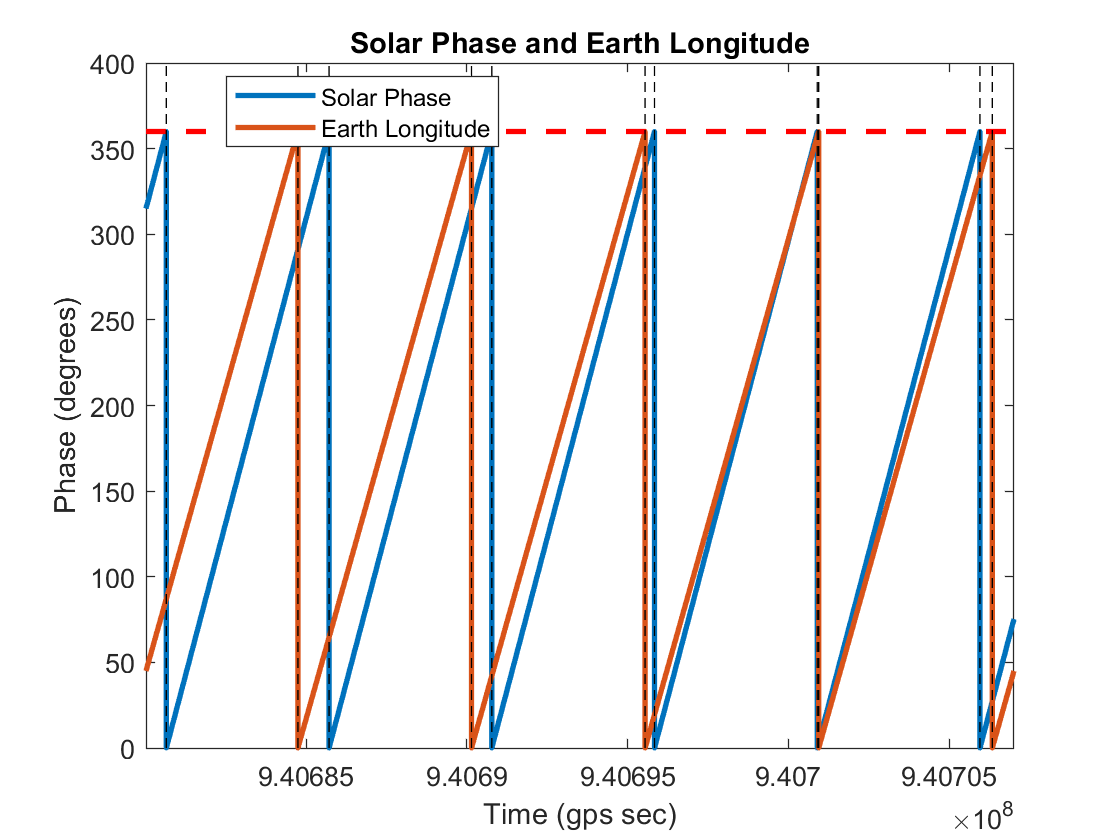

clc;
clf;
times = mydata(:, 1);
solar_phases = mydata(:, 2);
earth_longitude = mydata(:, 3);
particle_counts = mydata(:, 4);

%plot 5 periods
endtime = 5400*50;

plot(times(1:endtime), solar_phases(1:endtime), 'linewidth', 2), hold on;
plot(times(1:endtime), earth_longitude(1:endtime), 'linewidth', 2);
plot([times(1), times(endtime)], [360, 360], 'r--', 'linewidth', 2);
xlim([times(1), times(endtime)]);
ylim([0 400])
title('Solar Phase and Earth Longitude');
xlabel('Time (gps sec)');
ylabel('Phase (degrees)');
legend('Solar Phase', 'Earth Longitude', 'location', 'best');


solar_period_times = times(islocalmin(solar_phases));
for ii = solar_period_times(1:6)
    plot([ii, ii], [0, 500], 'k--', 'HandleVisibility', "off");
end
earth_period_times = times(islocalmin(earth_longitude));
for ii = earth_period_times(1:6)
    plot([ii, ii], [0, 500], 'k--', 'HandleVisibility', "off");
end

Here we can see that the solar phase and Earth longitude are linear and periodic, but with different periods:

%units of minutes
solar_period = mean(solar_period_times(2:2:end) - solar_period_times(1:2:end - 1)) ./ 60

solar_period = 84.3611

%units of minutes
earth_period = mean(earth_period_times(2:2:end) - earth_period_times(1:2:end - 1)) ./ 60

earth_period = 90

The earth period turns out to be exactly 90 minutes, while the solar period varies and has a slightly shorter period.

Next, we can plot the first 7.5 hours of data for particle counts to observe any time-related patterns:

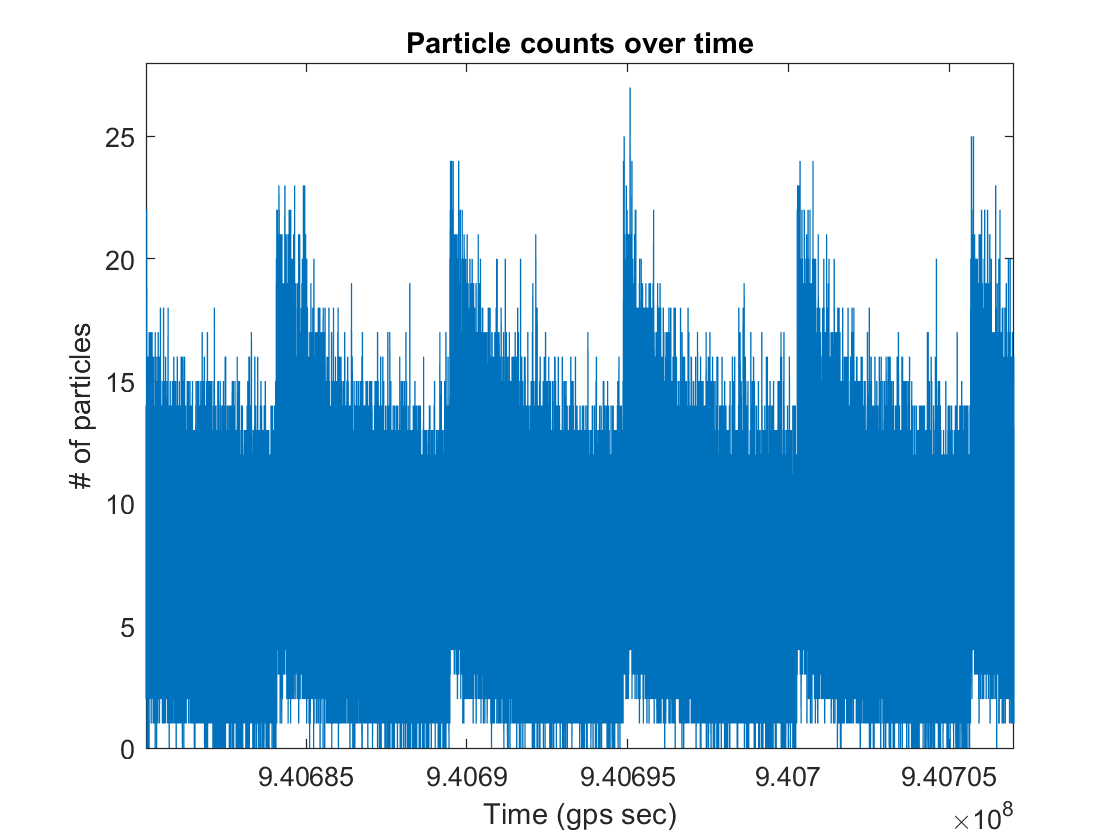

clf;
plot(times(1:endtime), particle_counts(1:endtime));
xlim([times(1), times(endtime)])
ylim([0 28]);
title('Particle counts over time');
xlabel('Time (gps sec)');
ylabel('# of particles')

We can see that there are certain periodic times throughout the data (spikes) where the number of cosmic rays is very high. This is concerning if we want to model this data using a distribution - since our data is not consistent over time, the model we create will not be an accurate representation of the data at all times.

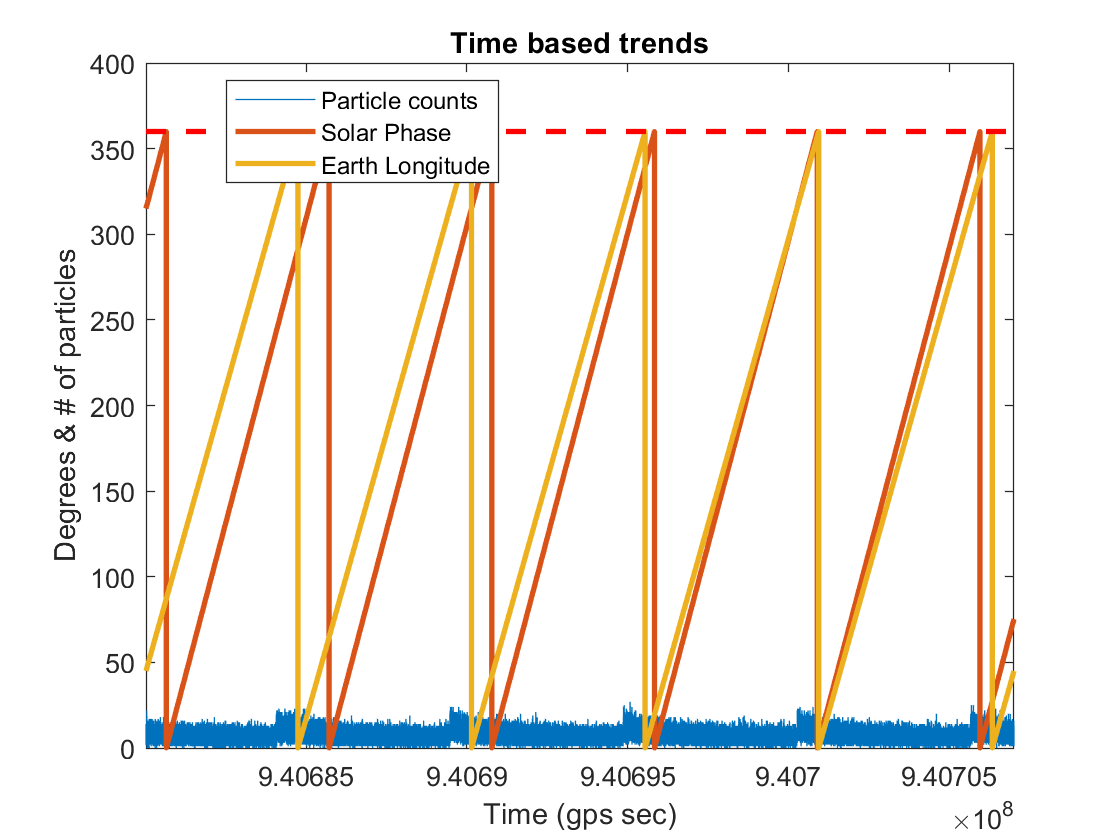

clf;
plot(times(1:endtime), particle_counts(1:endtime)), hold on;
plot(times(1:endtime), solar_phases(1:endtime), 'linewidth', 2);
plot(times(1:endtime), earth_longitude(1:endtime), 'linewidth', 2);
plot([times(1), times(endtime)], [360, 360], 'r--', 'linewidth', 2);
xlim([times(1), times(endtime)]);
title('Time based trends');
xlabel('Time (gps sec)')
ylabel('Degrees & # of particles')
legend('Particle counts','Solar Phase', 'Earth Longitude', 'location', 'best');

It seems like the particle data has a period on the same order as the period of solar phase and Earth longitude.

What are some possible causes of the inconsistent pattern in the particle data? Some very common causes of data inconsistencies in satellite measurements are:

- Instruments/hardware decaying over time

- An obstruction of the sensor of the instrument

- Charged particles exciting components or producing noise in the measurement

The particle data appears to be periodic and the average number of particle counts never seems to tend to 0 or infinity after a long time, so it is not likely that this is a result of hardware decaying or breaking. The rest of the options, an obstruction of the instrument or noise, are still possible causes of the signal contamination, so long as we can identify a cause of obstruction or noise that occurs at the same time during each orbit around Earth.

We can more accurately find the periods of the three sets of data by analyzing the Fourier transform of the data:

[f, fourier_solar] = fouriern(solar_phases);
[f, fourier_earth] = fouriern(earth_longitude);
[f, fourier_particle] = fouriern(particle_counts);

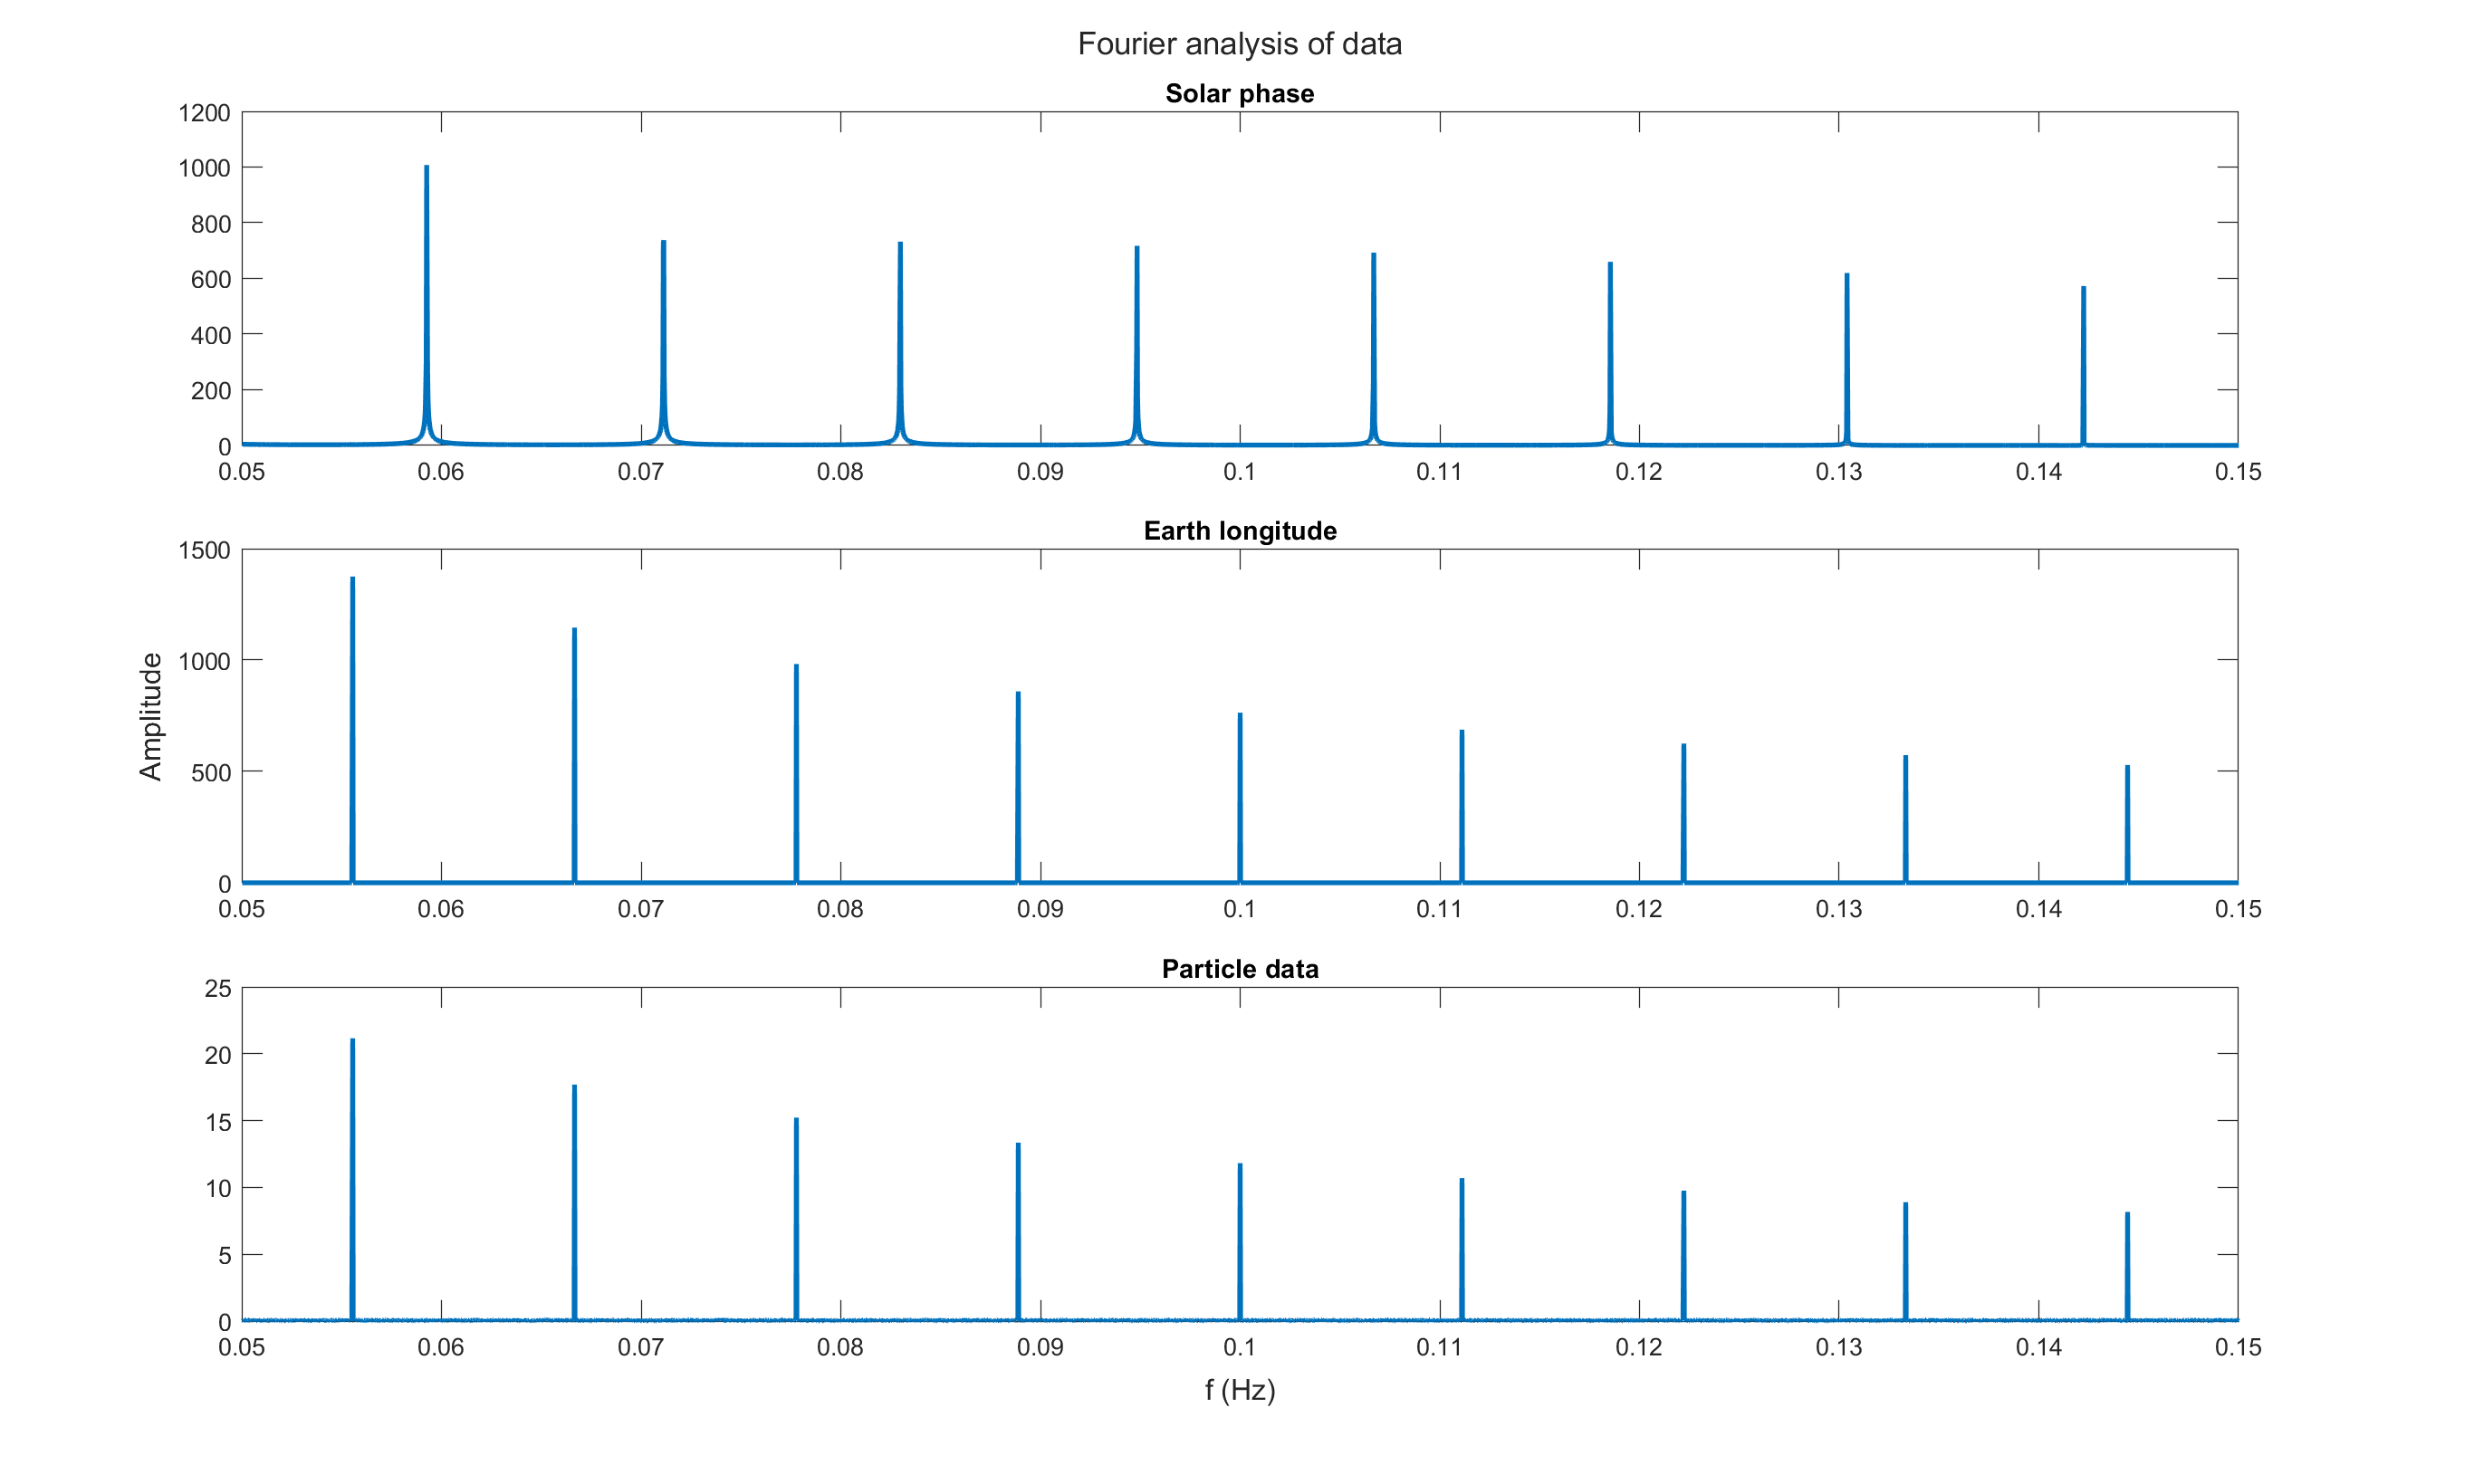

particle_frequencies = f(fourier_particle > 10);
earth_frequencies = f(fourier_earth > 1e3);
solar_frequencies = f(fourier_solar > 1e3);

clf;
t0 = tiledlayout(3, 1);

t1 = nexttile;
plot(f(f > 0.05), fourier_solar((f > 0.05)), 'linewidth', 2), hold on;
xlim([0.05 0.15]);
title(t1, 'Solar phase');

t2 = nexttile;
plot(f(f > 0.05), fourier_earth((f > 0.05)), 'linewidth', 2);
xlim([0.05 0.15]);
title(t2, 'Earth longitude');

t3 = nexttile;
plot(f(f > 0.05), fourier_particle((f > 0.05)), 'linewidth', 2);
xlim([0.05 0.15]);
title(t3, 'Particle data');

title(t0, 'Fourier analysis of data')
xlabel(t0, 'f (Hz)');
ylabel(t0, 'Amplitude');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

solar_period = 1 ./ solar_frequencies(2)

solar_period = 84.3750

earth_period = 1 ./ earth_frequencies(2)

earth_period = 90

particle_period = 1 ./ particle_frequencies(2)

particle_period = 90

We can see that the period of the Earth longitude and the period of the particle count data is the same. Therefore, we can assume that the fluctuations in the particle count data is correlated to the satellite's position in its orbit around the Earth. 

Looking at the distribution of values for the particle data:

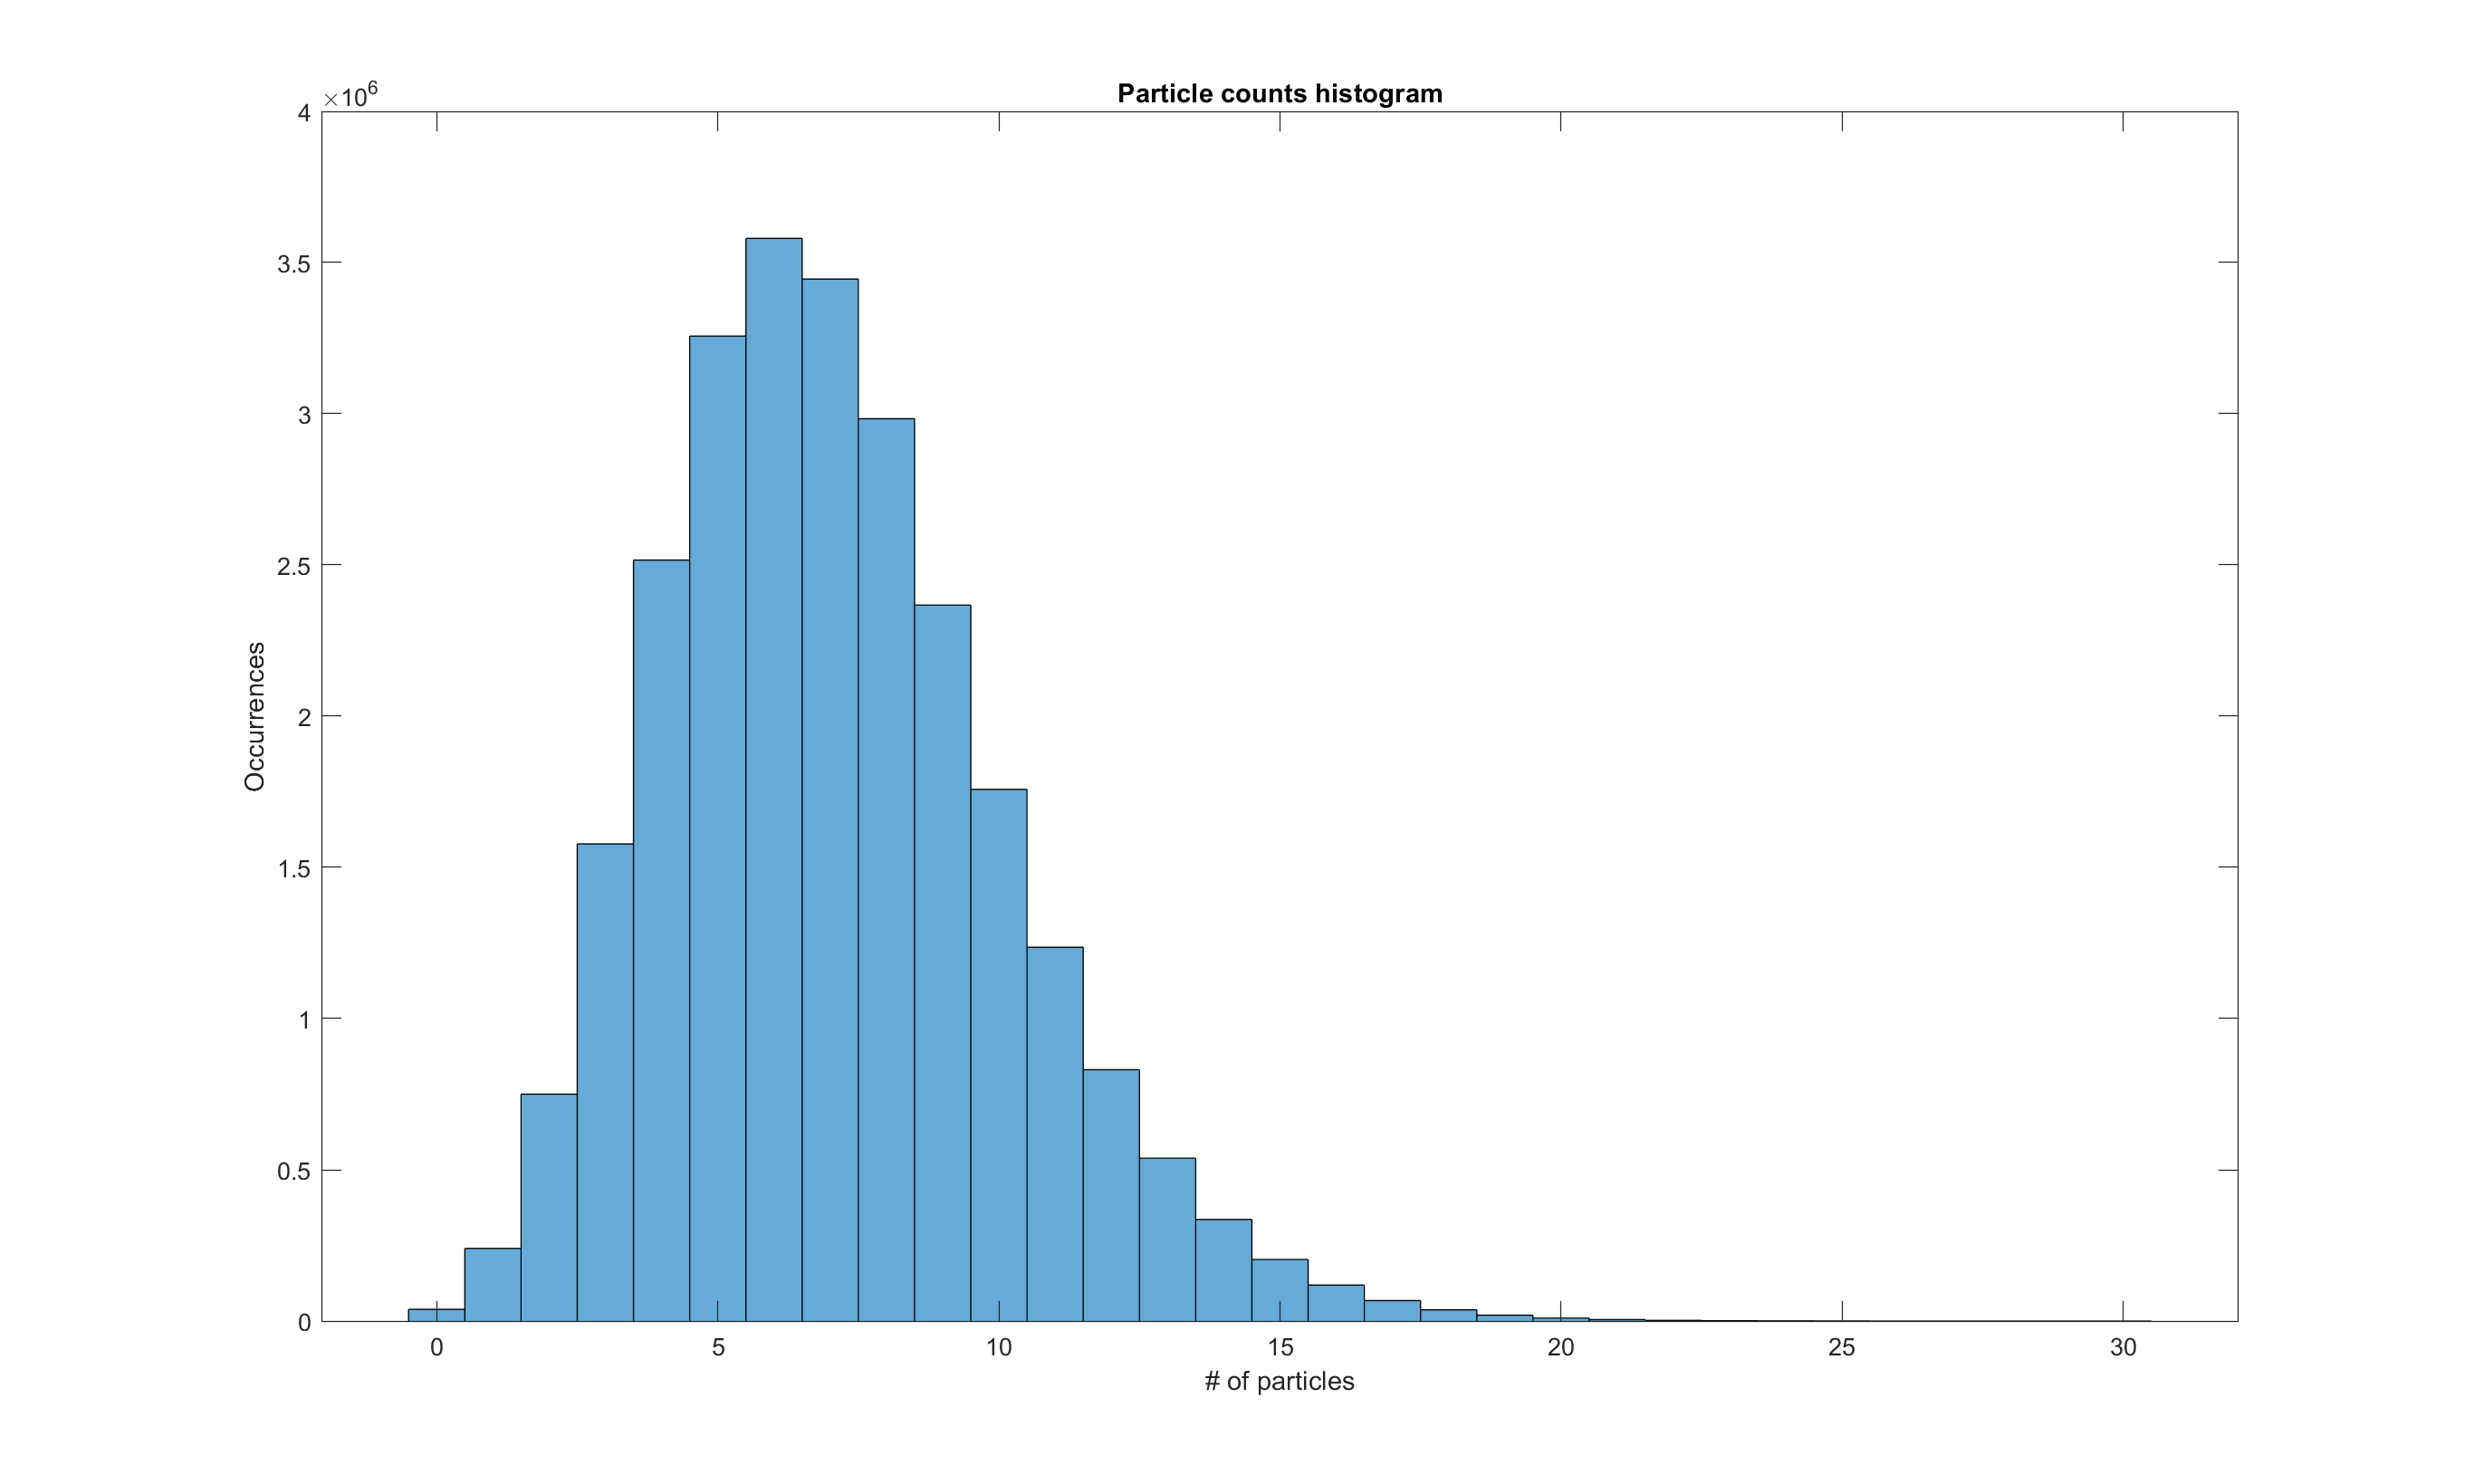

clf;
histogram(particle_counts, 'BinMethod', 'Integers');
title('Particle counts histogram');
xlabel('# of particles');
ylabel('Occurrences');

We expect this distribution to be best approximated by a Poisson distribution, since it is based on the random arrival of cosmic rays within a specific time interval. The data appears to have a mean of approximately 6, so we can see if a Poisson distribution with $\lambda =6$ will accurately model the data:

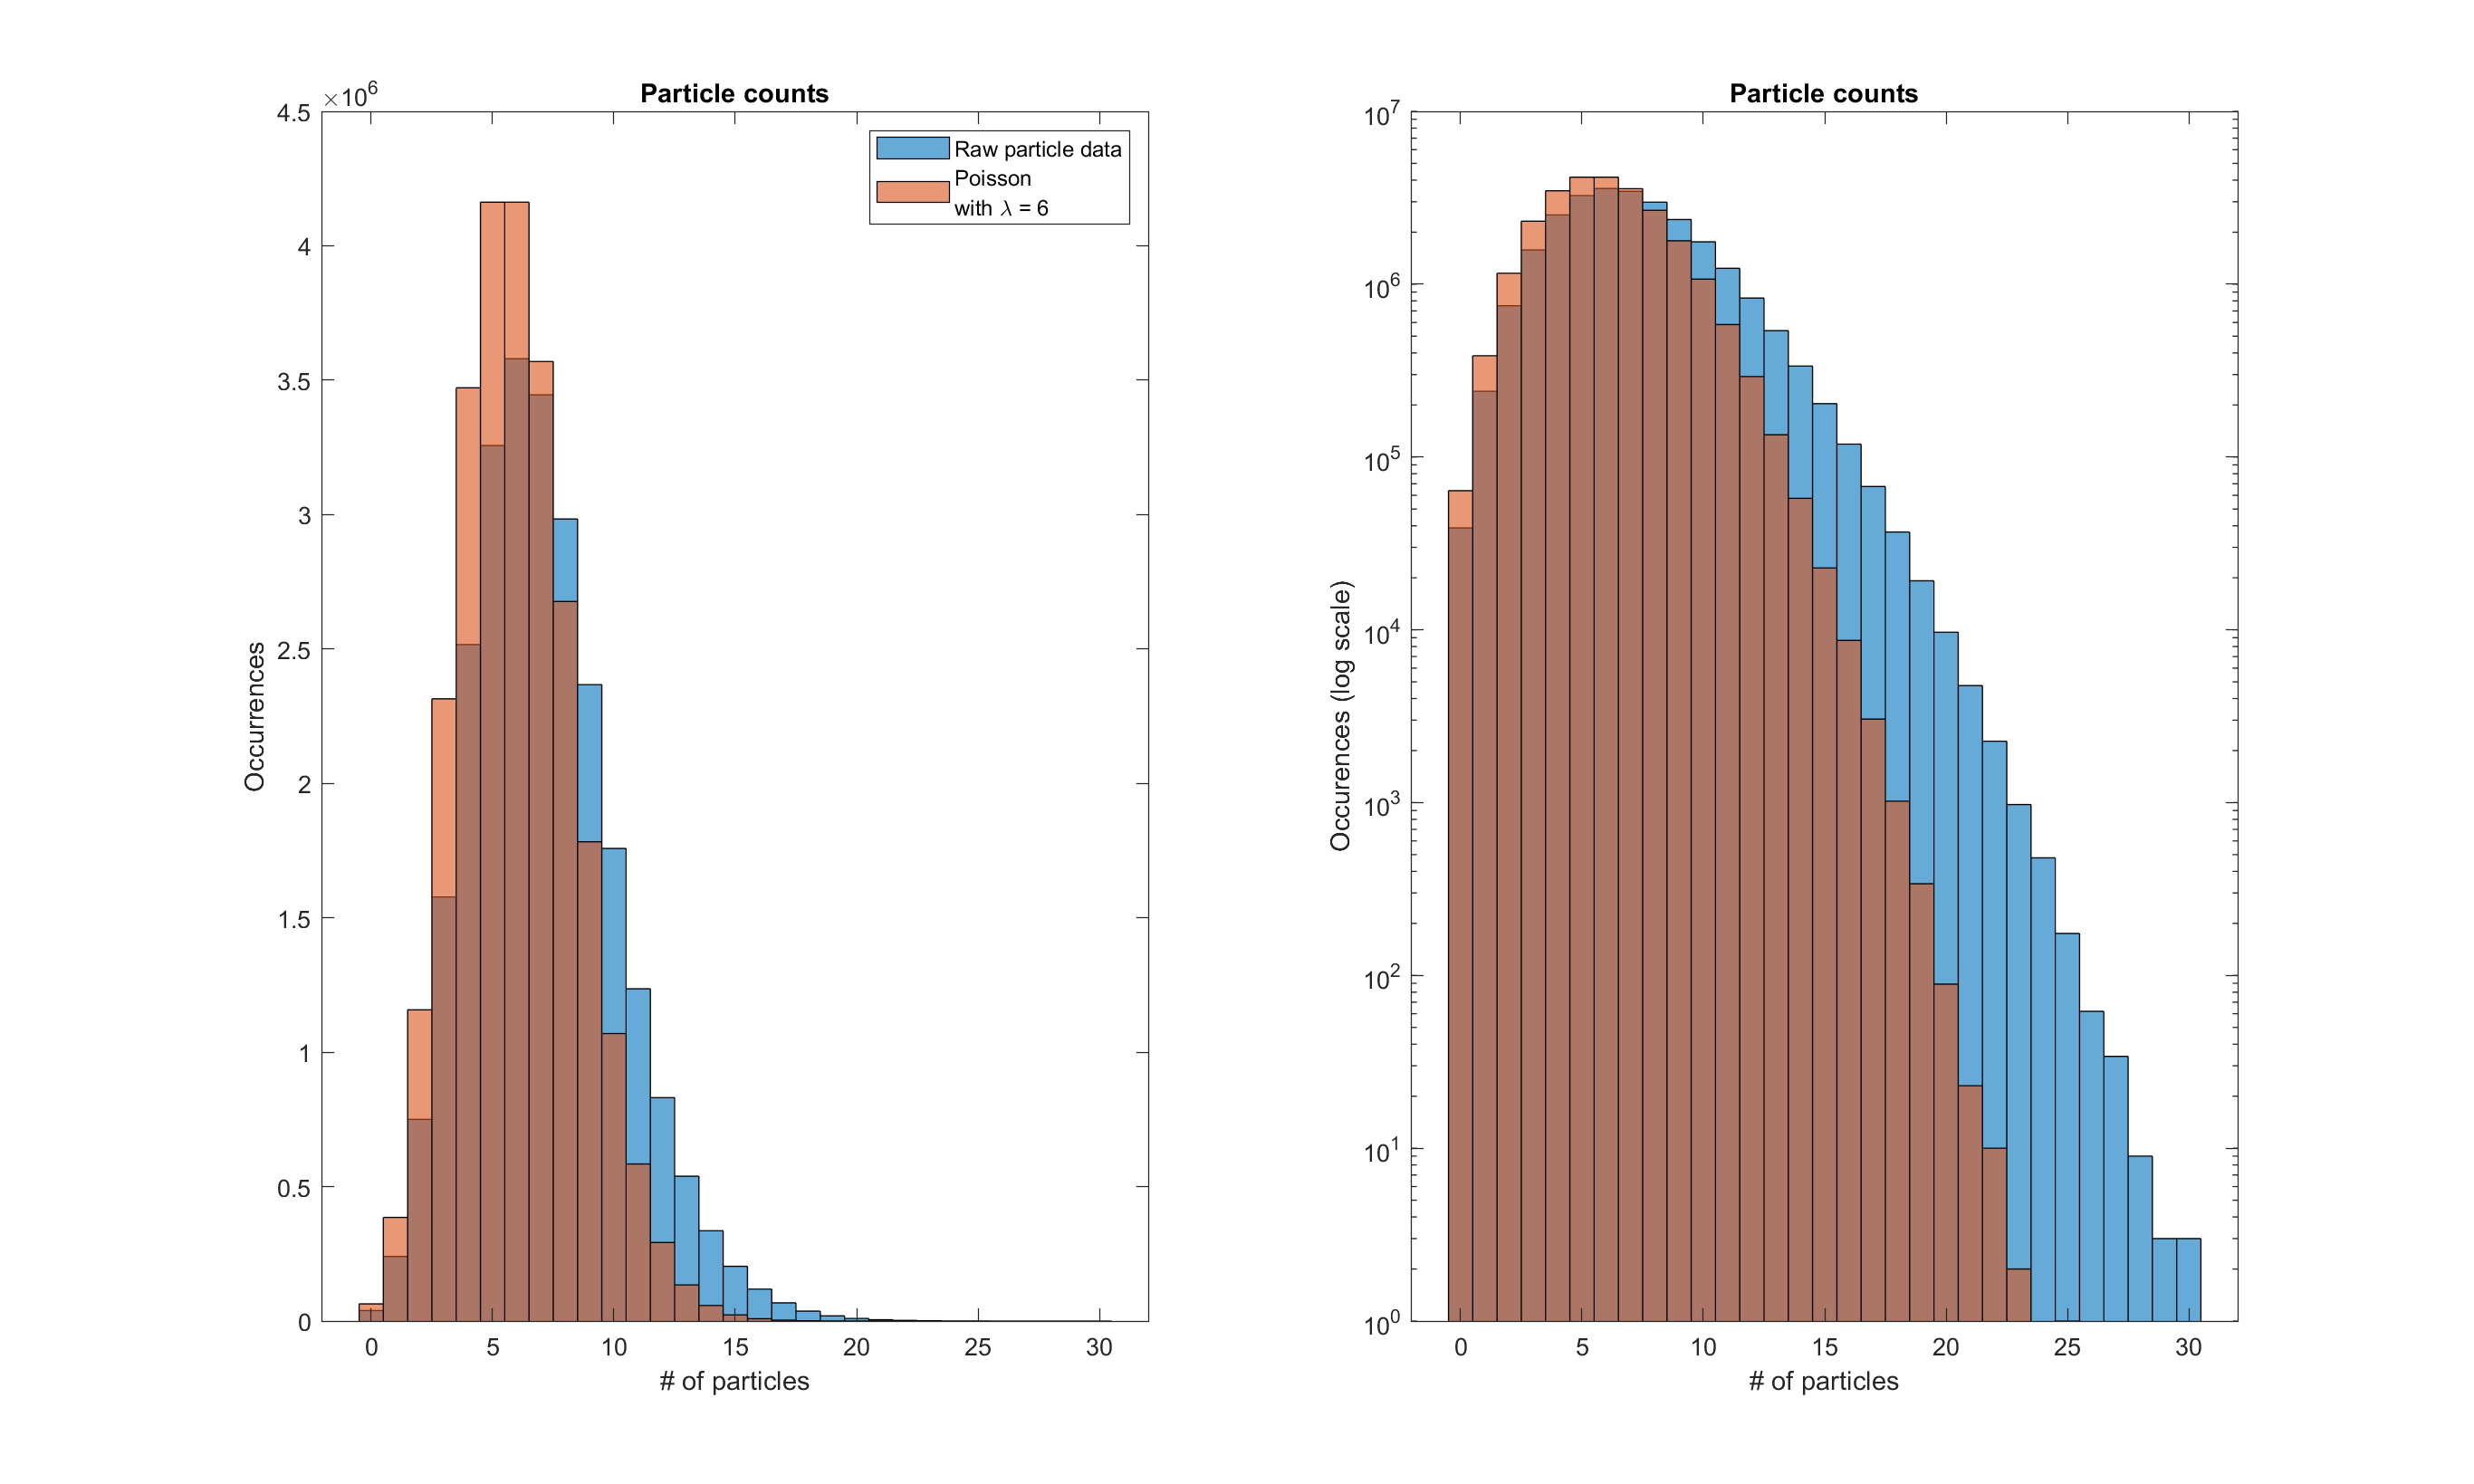

clf;
subplot(1, 2, 1)
histogram(particle_counts, 'BinMethod', 'Integers'), hold on;
poisson = makedist("Poisson", "lambda", 6);
poisson_vals = random(poisson, [1 length(particle_counts)]);
histogram(poisson_vals)
title('Particle counts');
xlabel('# of particles');
ylabel('Occurrences');
legend('Raw particle data', 'Poisson\newlinewith {\lambda} = 6');

subplot(1, 2, 2)
histogram(particle_counts, 'BinMethod', 'Integers'), hold on;
histogram(poisson_vals);
set(gca, 'YScale', 'log');
title('Particle counts');
xlabel('# of particles');
ylabel('Occurences (log scale)')

The data does **not** accurately follow a Poisson trend; rather, our data has far more measurements with high numbers of particles. 

Our current data does not accurately follow any particular distribution, and as such it is hard for us to perform statistical analysis on it. We would like to develop a model for the data that accounts for the anomalous region where the number of cosmic rays measured is very high. To do this, we can split the data into time intervals corresponding to times when the satellite is in the anomalous region and when it is not. 

Let's look again at the plot of particle counts over time and compare it to the plot of the Earth longitude over time. The system seems to exhibit anomalous behavior whenever the Earth longitude somewhere between 40 and 300 degrees. The most likely cause of this behavior may be the [South Atlantic Anomaly](https://en.wikipedia.org/wiki/South_Atlantic_Anomaly), a region of the Atlantic Ocean where the Earth's inner [Van Allen radiation belt](https://en.wikipedia.org/wiki/Van_Allen_radiation_belt) comes very close to the Earth's surface. As the Van Allen radiation belt is full of energetic charged particles, this region is known to cause several problems with satellites passing by, expecially particle counters such as the one we are currently investigating.

Assuming that this anomalous region is between 300 degrees and 40 degrees longitude:

normal_data_indices = (earth_longitude > 40) & (earth_longitude < 300);
anomalous_data_indices = ~normal_data_indices;
normal_counts = particle_counts(normal_data_indices);
normal_counts_plot = particle_counts .* normal_data_indices;
%normal_times = times;
%Approximate the mean count # of the normal data
mean_normal = mean(normal_counts)

mean_normal = 6.4235

anomalous_counts = particle_counts(anomalous_data_indices);
anomalous_counts_plot = particle_counts .* anomalous_data_indices;
%anomalous_times = times;
%Approximate the mean count # of the anomalous data
mean_anomalous = mean(anomalous_counts)

mean_anomalous = 8.8490

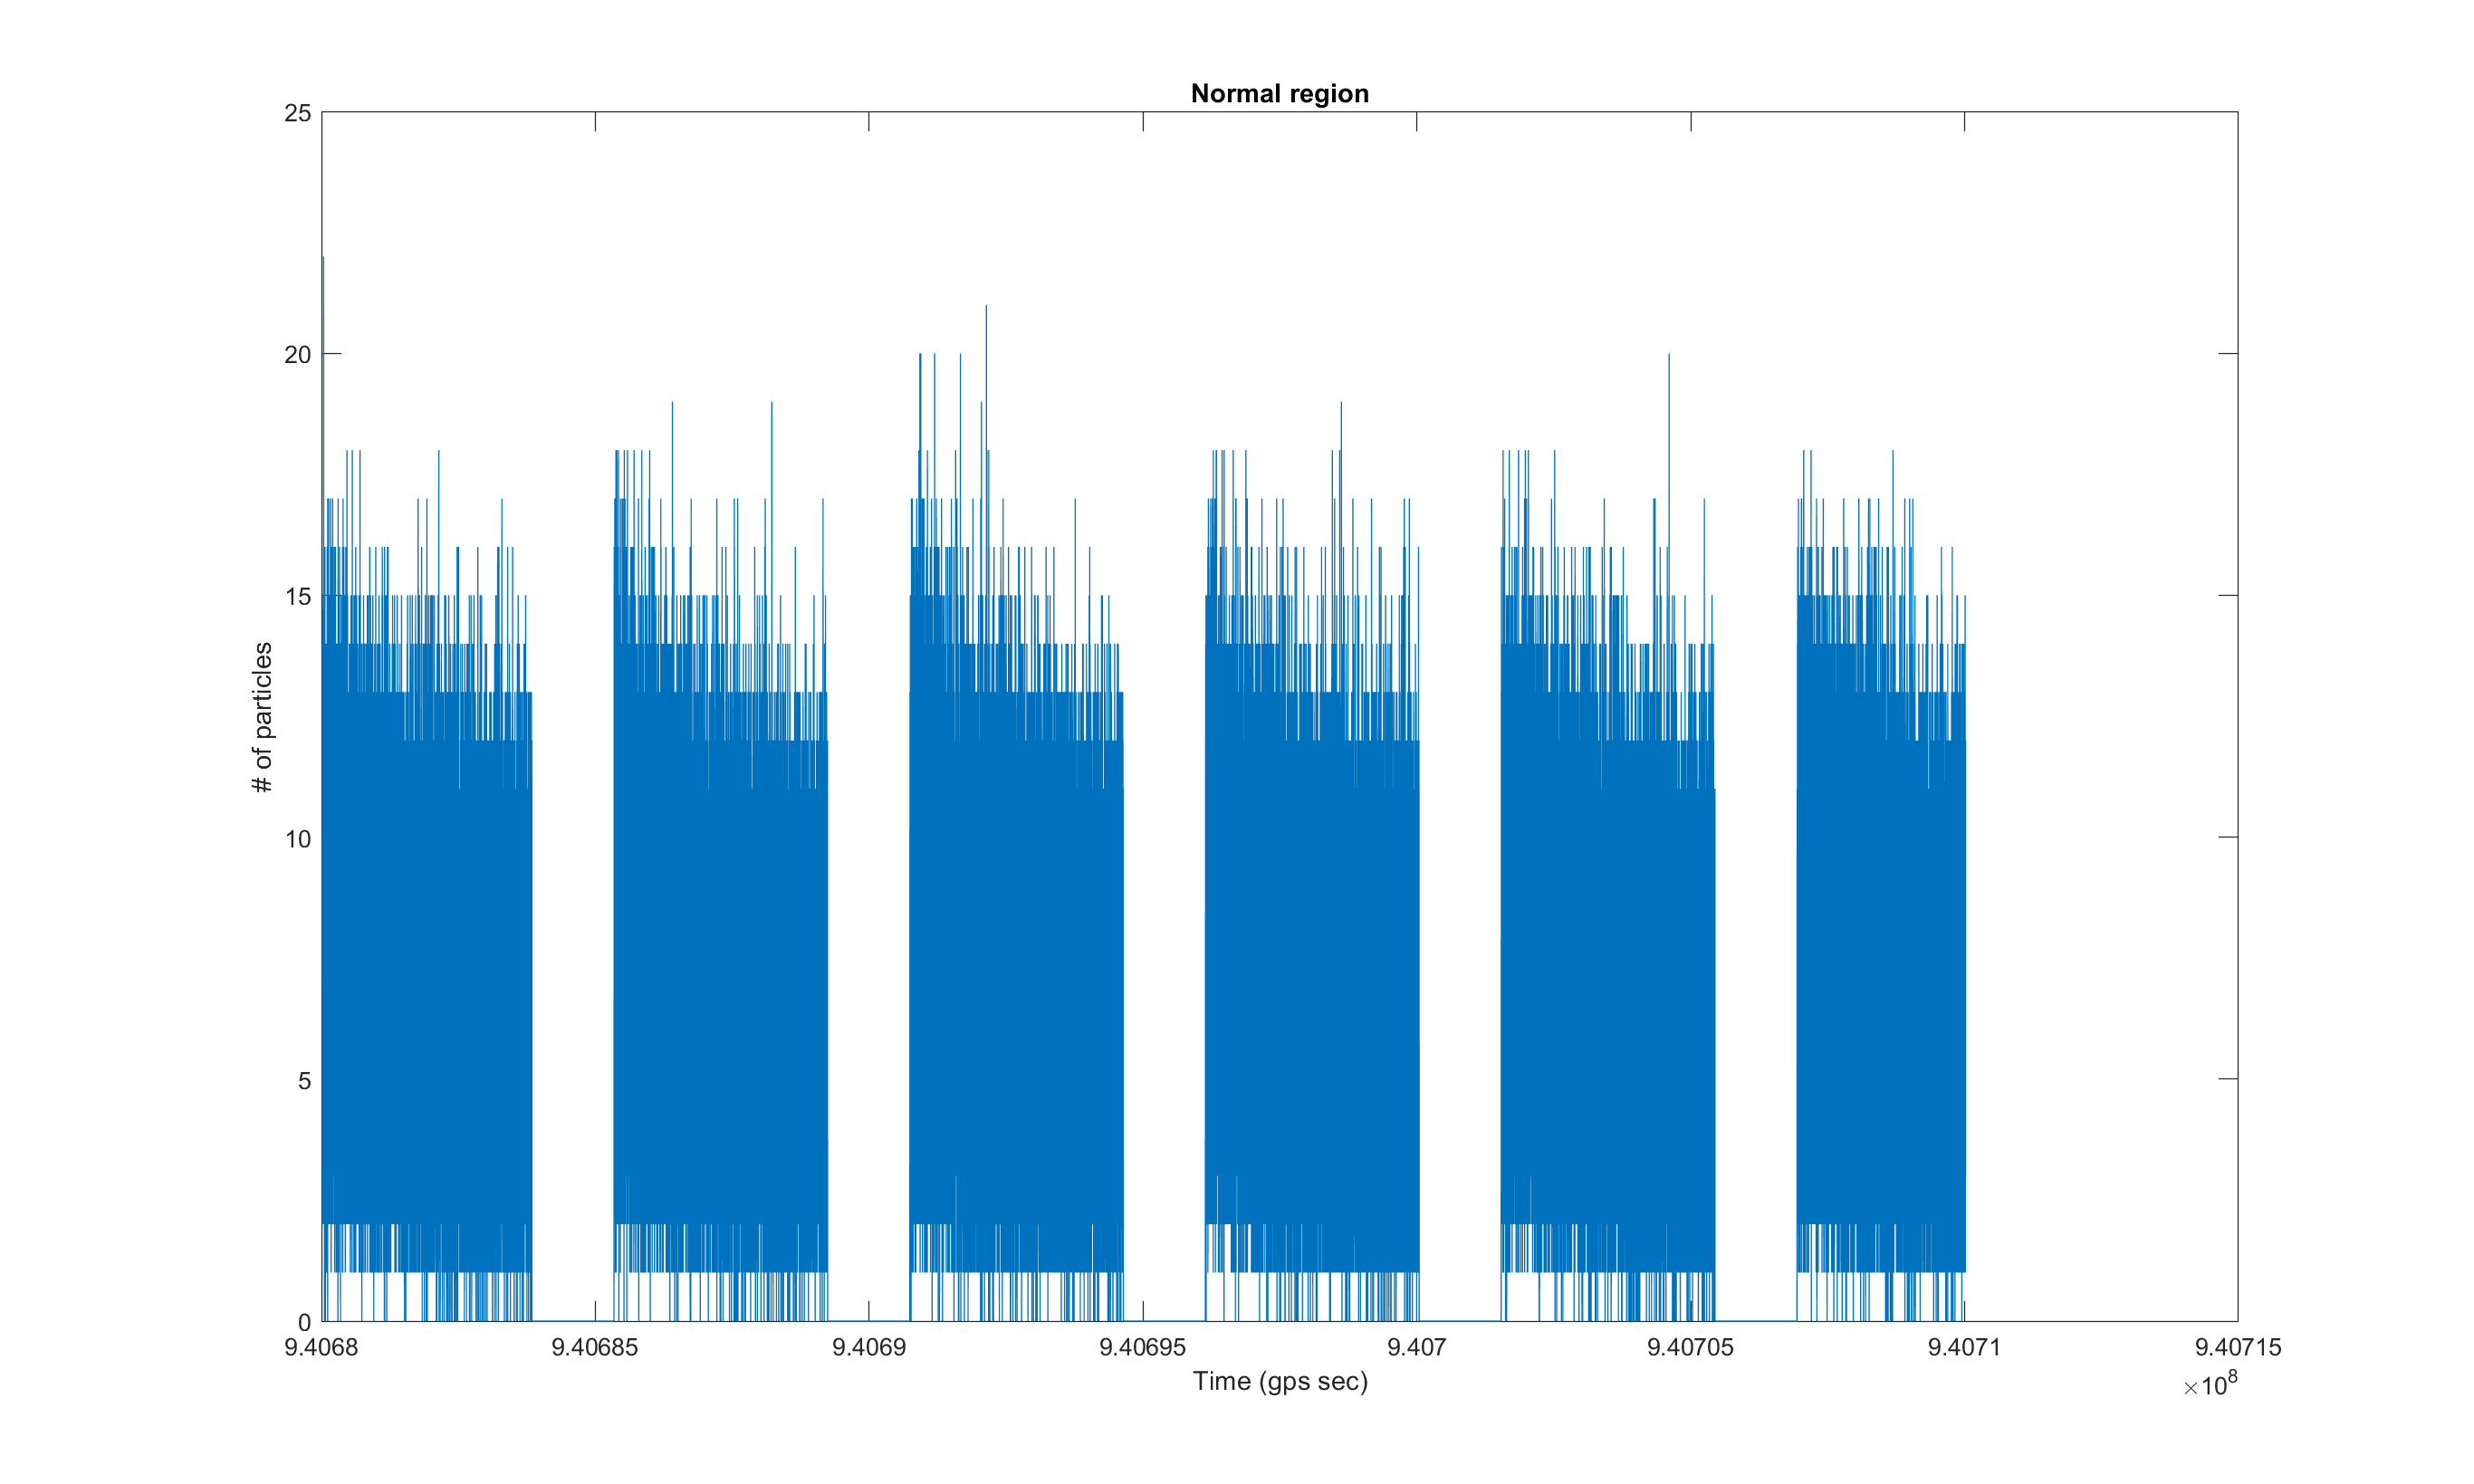

clf;
limit = 300000;
plot(times(1:limit), normal_counts_plot(1:limit));
title('Normal region');
xlabel('Time (gps sec)')
ylabel('# of particles')

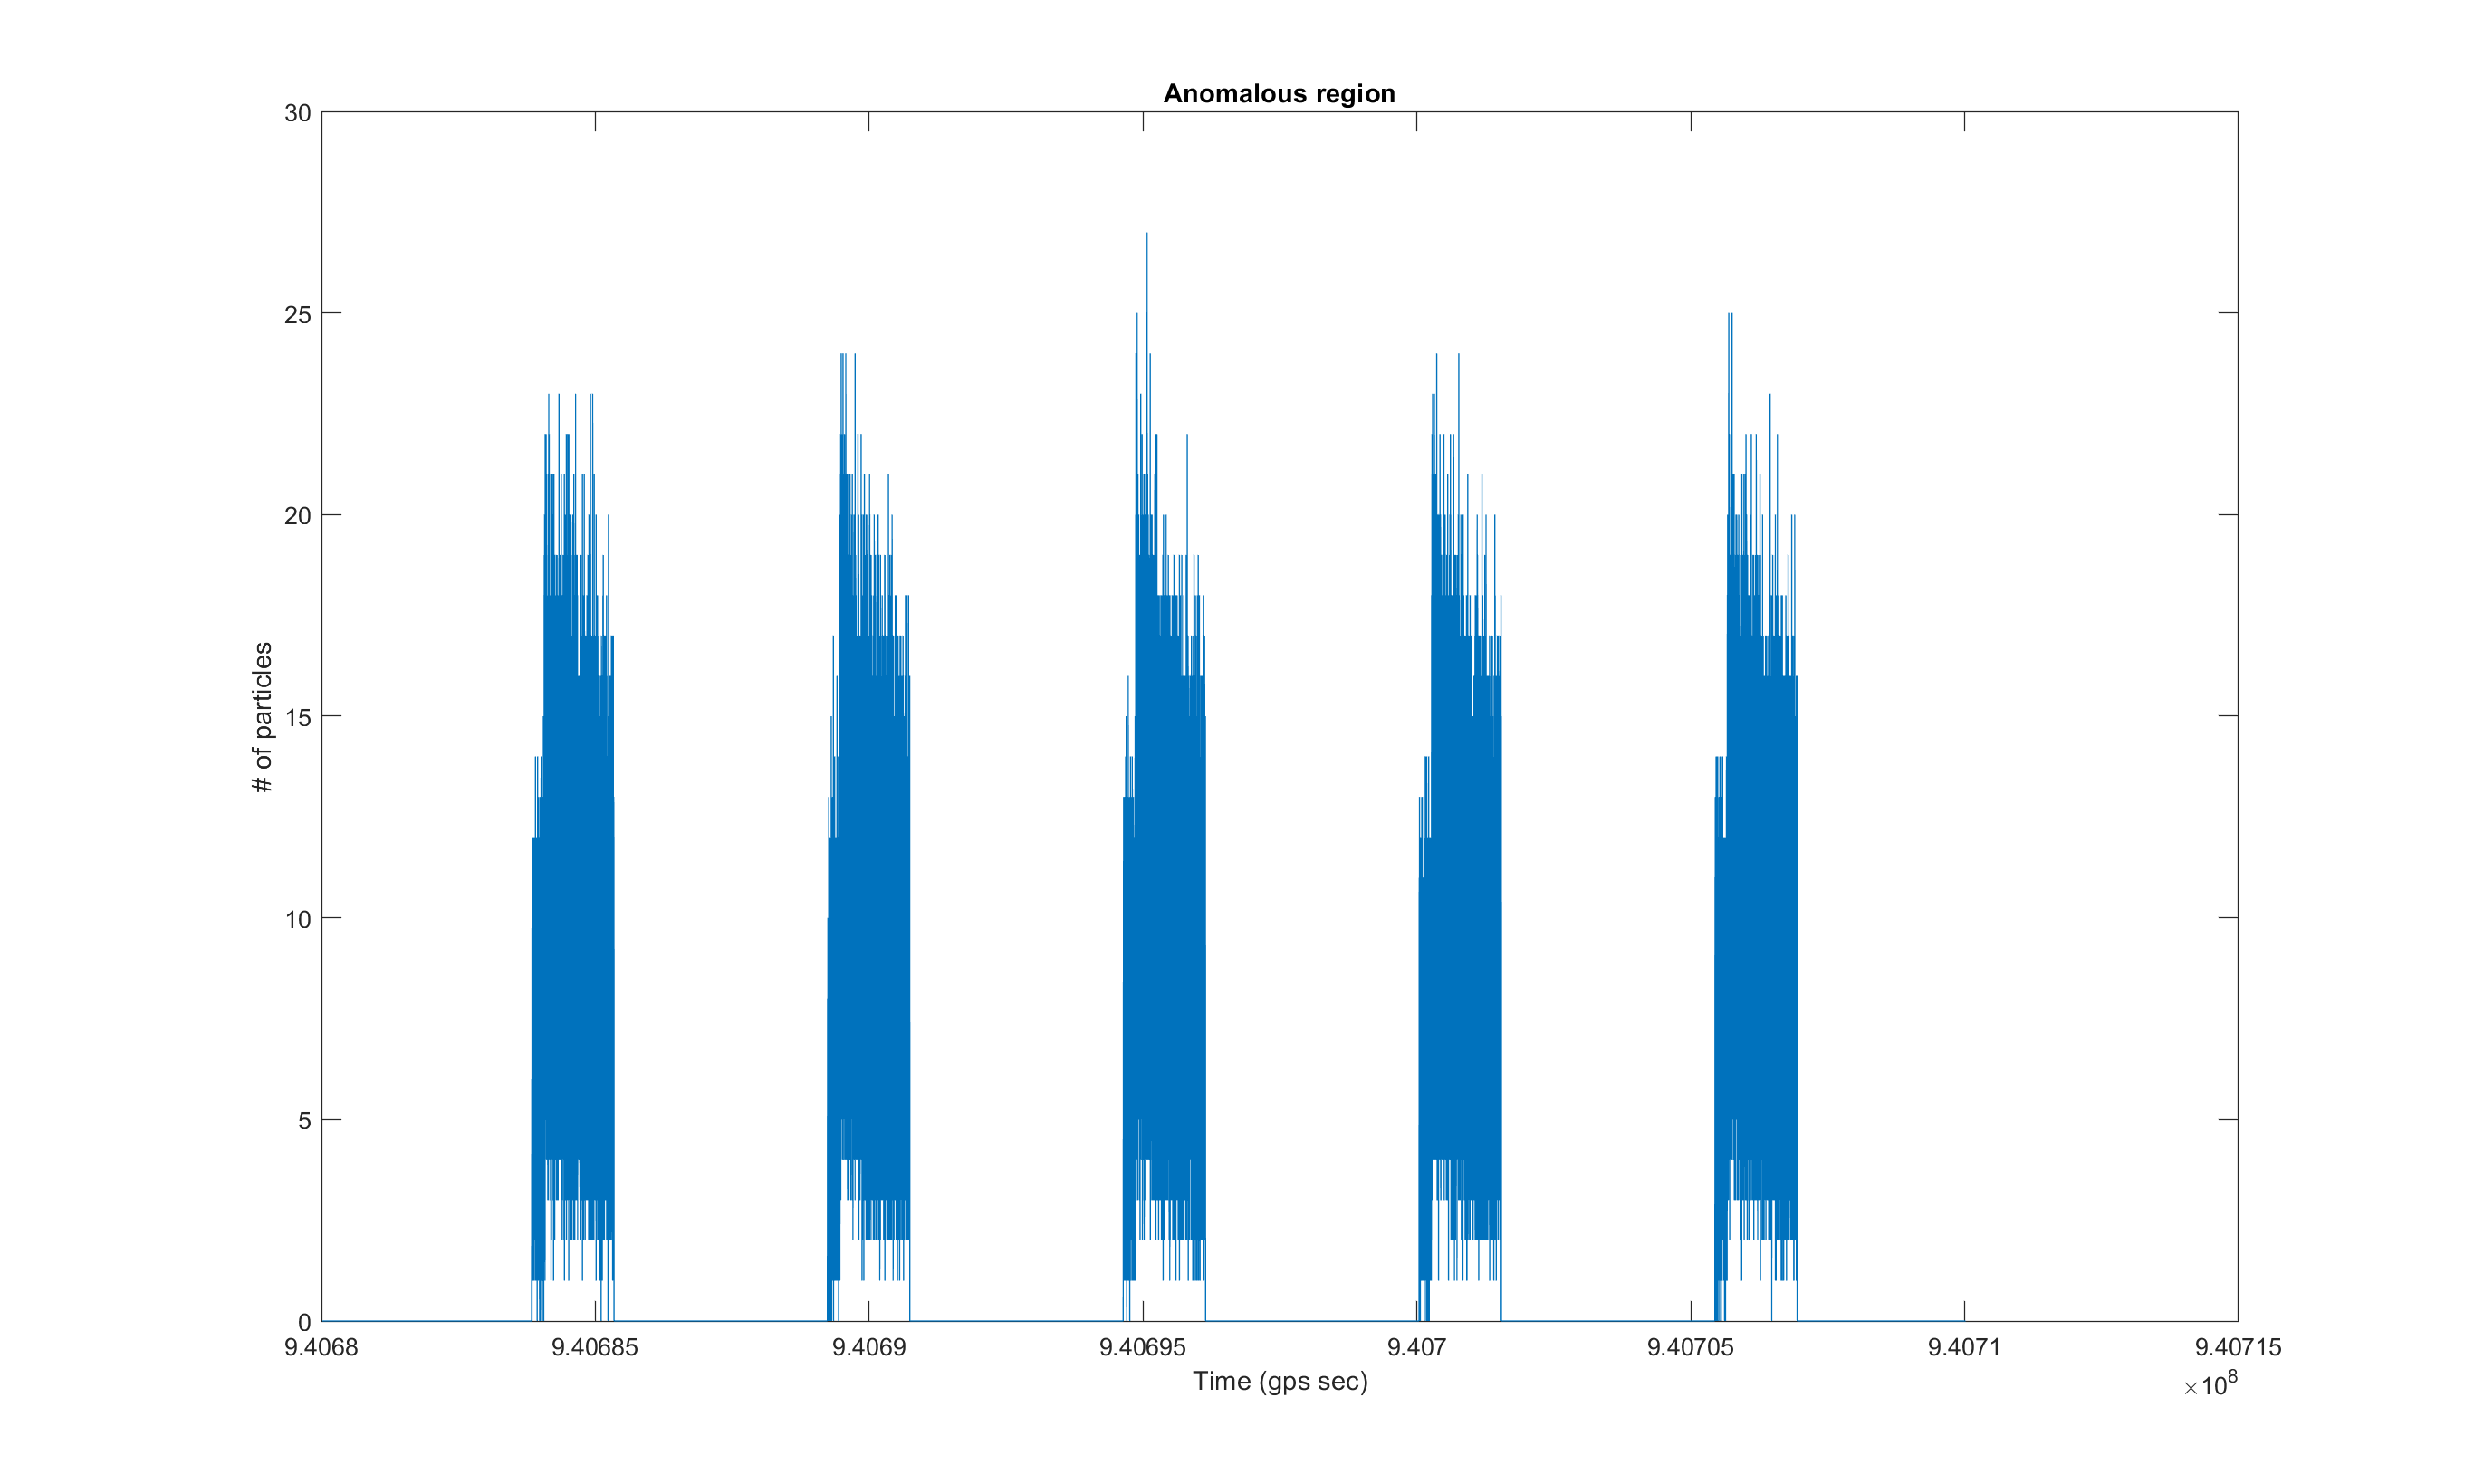

clf;
plot(times(1:limit), anomalous_counts_plot(1:limit));
title('Anomalous region');
xlabel('Time (gps sec)')
ylabel('# of particles')

Now that we have separated our data into two time-dependent data sets, we can model our data by switching between the anomalous and normal distributions depending on which region we are in. Each of these two distributions are more stable over time and vary less in the number of particles detected. Now we can model our distributions for the anomalous and normal regions with Poisson distributions:

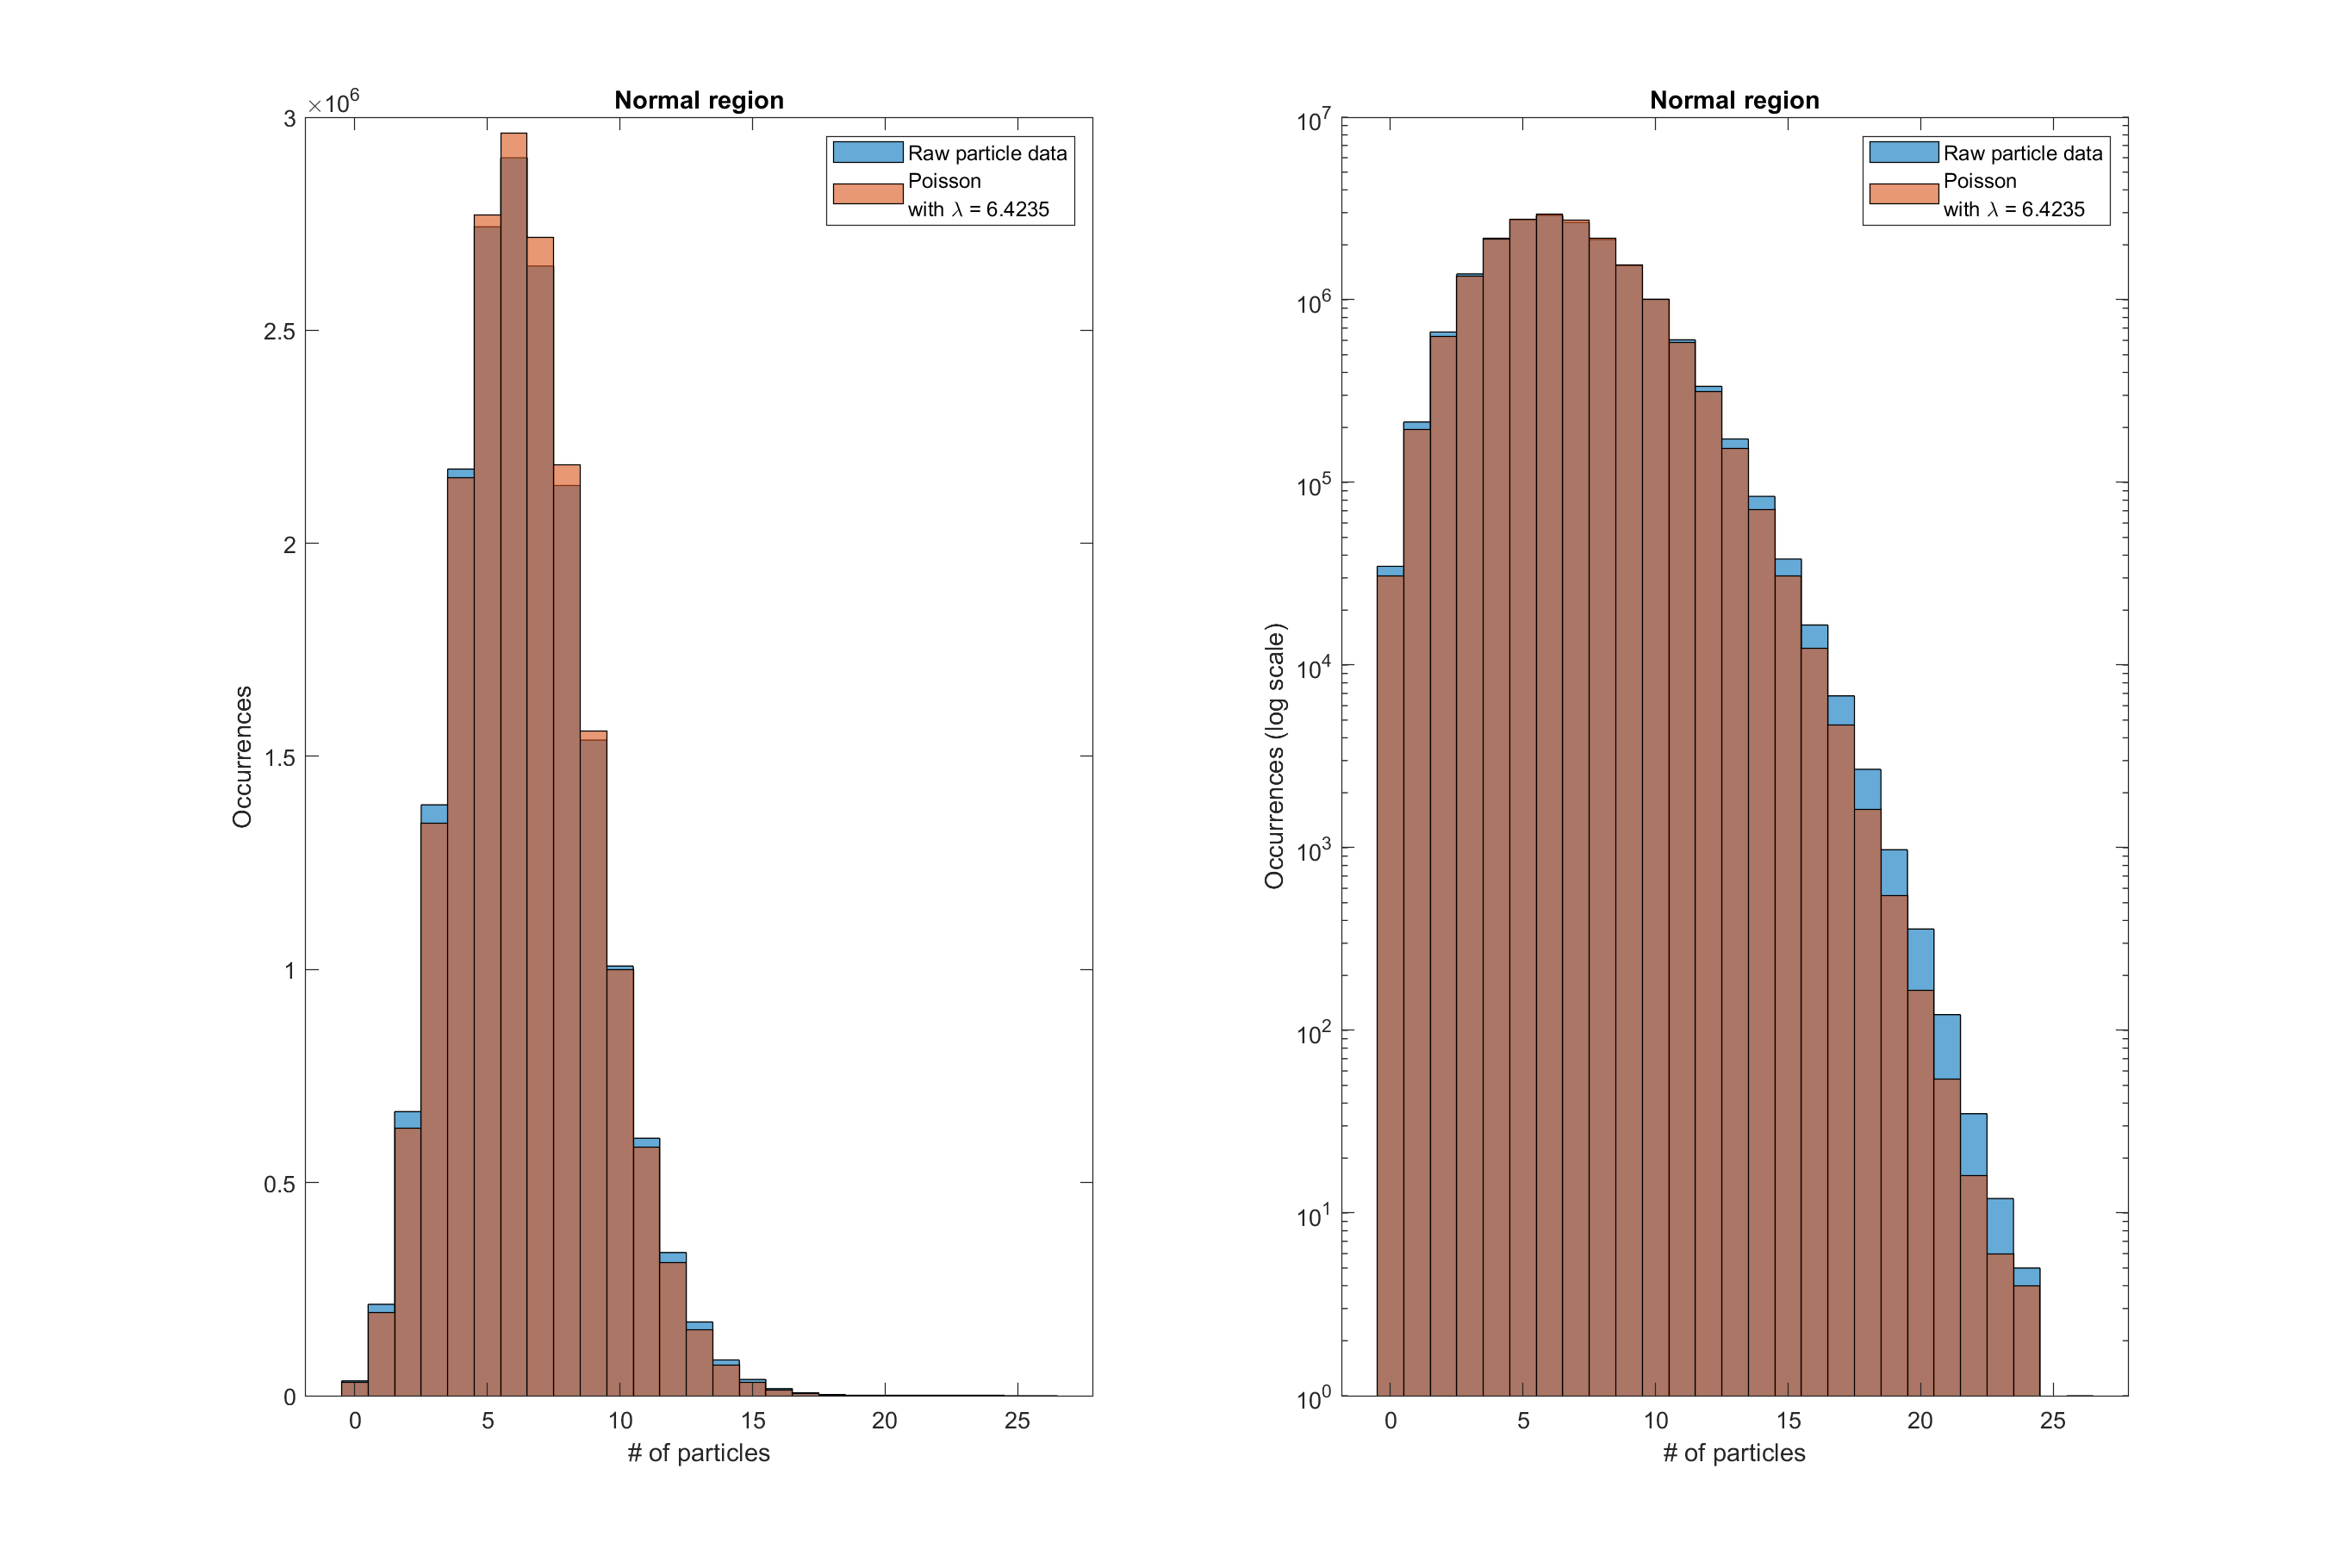

clf;
subplot(1, 2, 1)
histogram(normal_counts), hold on;
poisson = makedist("Poisson", "lambda", mean_normal);
poisson_vals = random(poisson, [1 length(normal_counts)]);
histogram(poisson_vals)
title('Normal region');
xlabel('# of particles');
ylabel('Occurrences');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_normal)]);

subplot(1, 2, 2)
histogram(normal_counts), hold on;
histogram(poisson_vals)
set(gca, 'YScale', 'log');
title('Normal region');
xlabel('# of particles');
ylabel('Occurrences (log scale)');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_normal)]);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

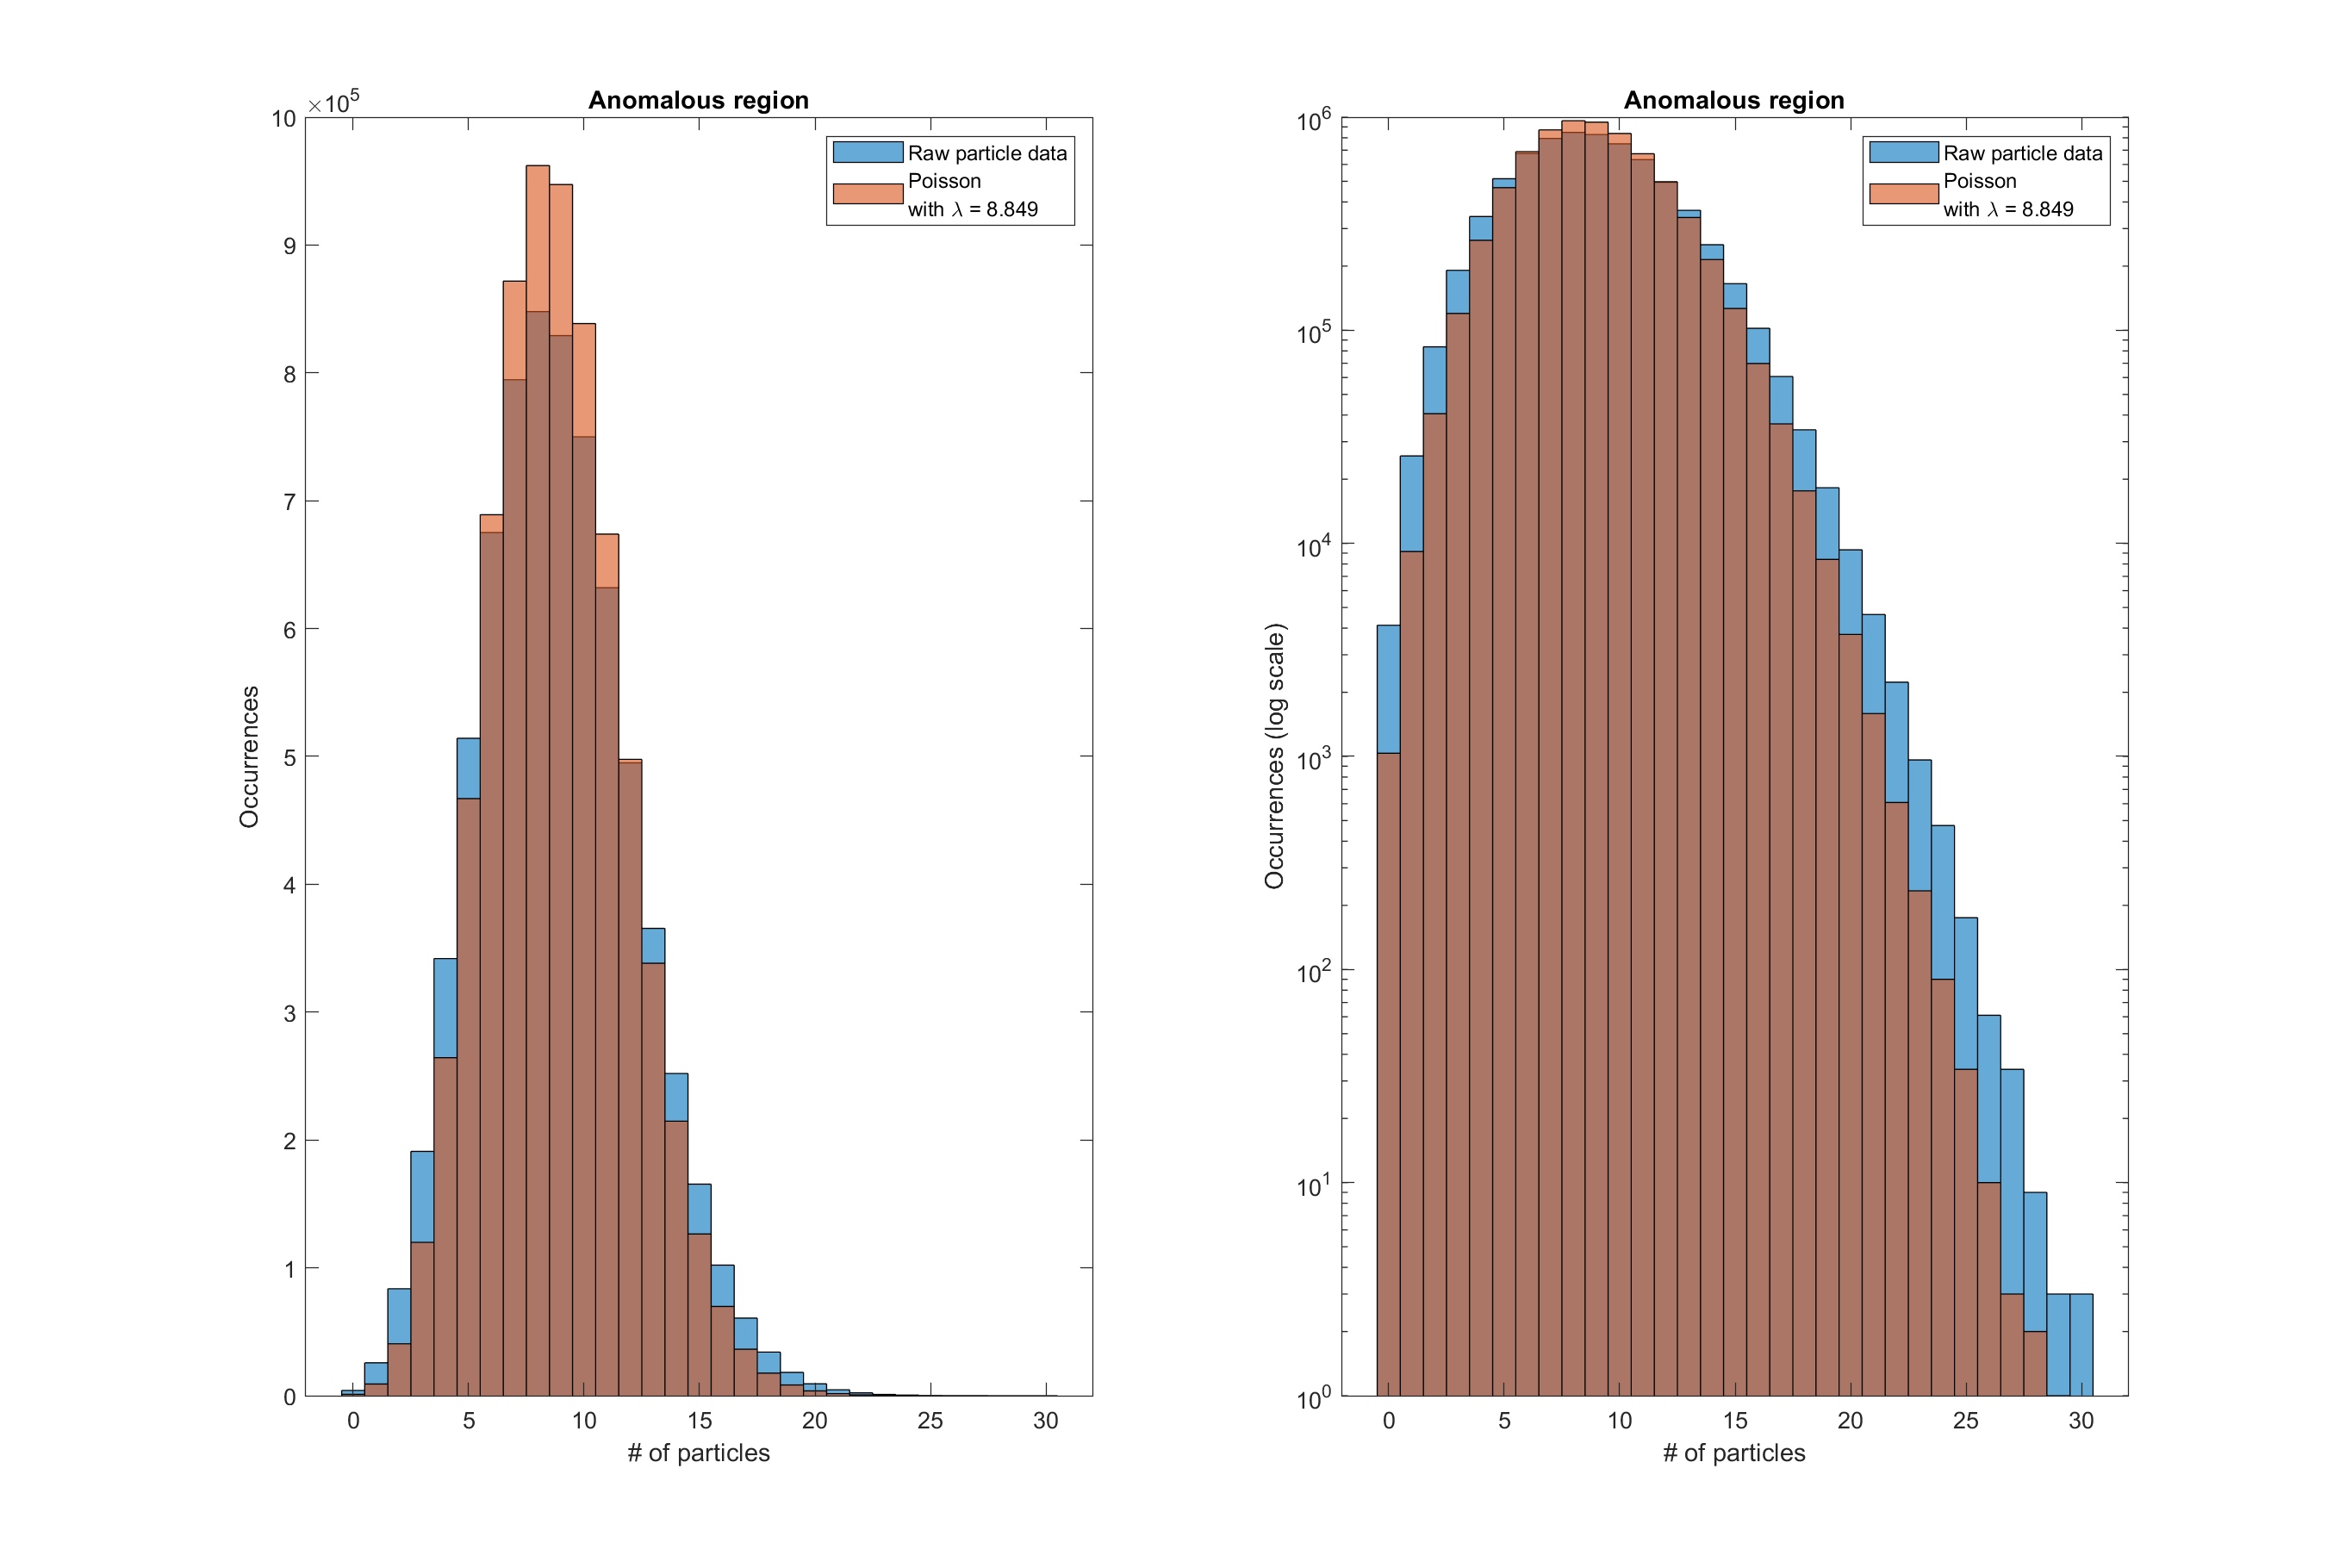

clf;
subplot(1, 2, 1)
histogram(anomalous_counts), hold on;
poisson = makedist("Poisson", "lambda", mean_anomalous);
poisson_vals = random(poisson, [1 length(anomalous_counts)]);
histogram(poisson_vals)
title('Anomalous region');
xlabel('# of particles');
ylabel('Occurrences');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_anomalous)]);
subplot(1, 2, 2)
histogram(anomalous_counts), hold on;
histogram(poisson_vals)
set(gca, 'YScale', 'log')
title('Anomalous region');
xlabel('# of particles');
ylabel('Occurrences (log scale)');
legend('Raw particle data', ['Poisson\newlinewith {\lambda} = ' num2str(mean_anomalous)]);

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

This is a much better representation of our data; it seems like we have identified the main source of signal contamination in our data. By further tweaking the parameters of our Poisson model (i.e. changing the longitudes where the South Atlantic Anomaly begins and ends), one could make an even more accurate model of this data.

We would also like to investigate the quantity of particles that could be classified as a discovery in either region. In other words, we would like to answer the question: What is the number of particles you would need to see in 100 milliseconds such that it could be classified as a 5-sigma event? To do this, we use our Poisson models for each region and find the value of the cumulative distribution function (cdf) at a probability corresponding to a $5\sigma$ event on a normal distribution:

p_5sigma = normcdf(-5, 0, 1)

p_5sigma = 2.8665e-07

significant_particles_normal = abs(icdf('Poisson', 1-p_5sigma, mean_normal))

significant_particles_normal = 23

One would need to see 23 particles in 100 milliseconds inside the normal region to claim a $5\sigma$ discovery.

significant_particles_anomalous = abs(icdf('Poisson', 1-p_5sigma, mean_anomalous))

significant_particles_anomalous = 27

One would need to see 27 particles in 100 milliseconds inside the anomalous region to claim a $5\sigma$ discovery. This number is higher than the number required in the normal region since the Van Allen belt contributes to the background, creating more noise in the signal.

### Problem 2

Here we will be observing a set of 10 images of the night sky.

clear;
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


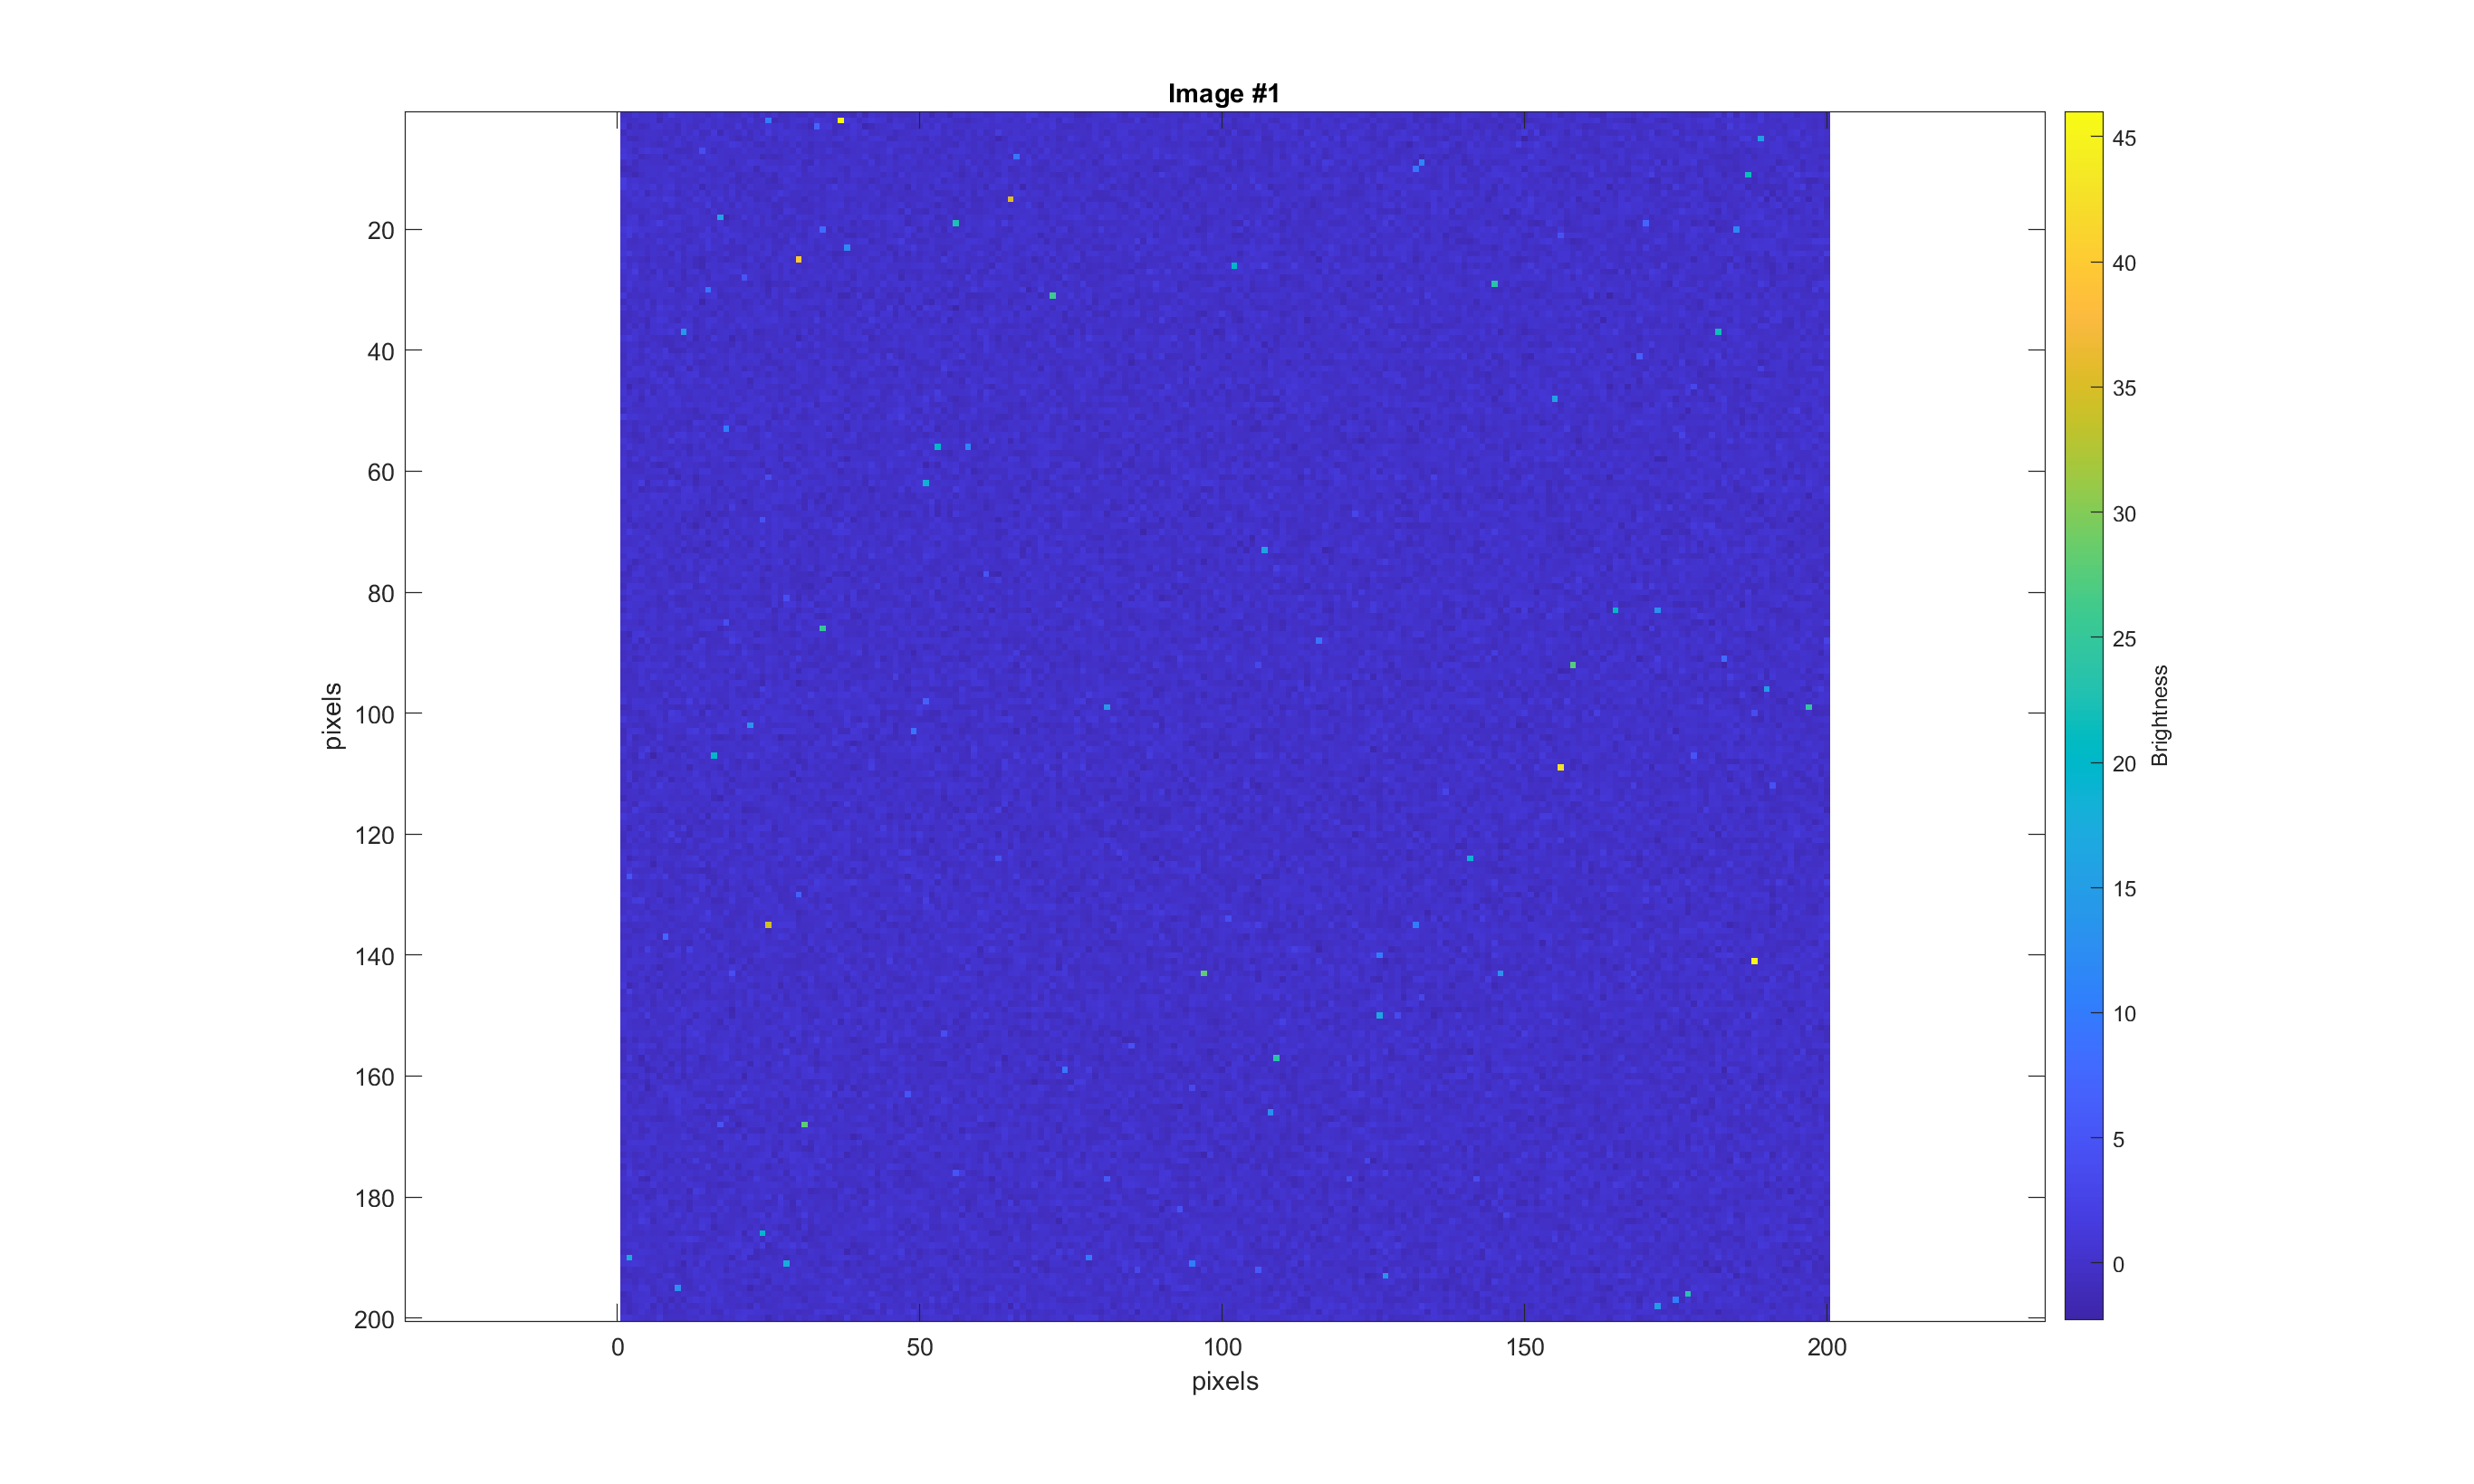

mydata = h5read("images.h5",'/imagestack');

clf;
image1 = squeeze(mydata(1, :, :));
imagesc(image1);
c = colorbar;
c.Label.String = 'Brightness';
axis equal;
title('Image #1');
xlabel('pixels');
ylabel('pixels');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

This is the data from one image visually, where the brightness of an object is represented by color. This picture shows us the brightness of pixels relative to a baseline brightness $B_0$. We will set $B_0 =0$, representing the average value of the background. The images are therefore representations of the brightness of stars in arbitrary units relative to the average background brightness.

The data within one image is not time-dependent, as each image corresponds to the sky at one instant of time. However, since each image corresponds to a different moment in time, we can say that the data is time-dependent in the small fluctuations in each pixel.

For example, choosing a random pixel (which will likely be part of the background) and looking at its brightness value for each instant in time:

pixel = randi(200, [1, 2])

pixel =     36   104


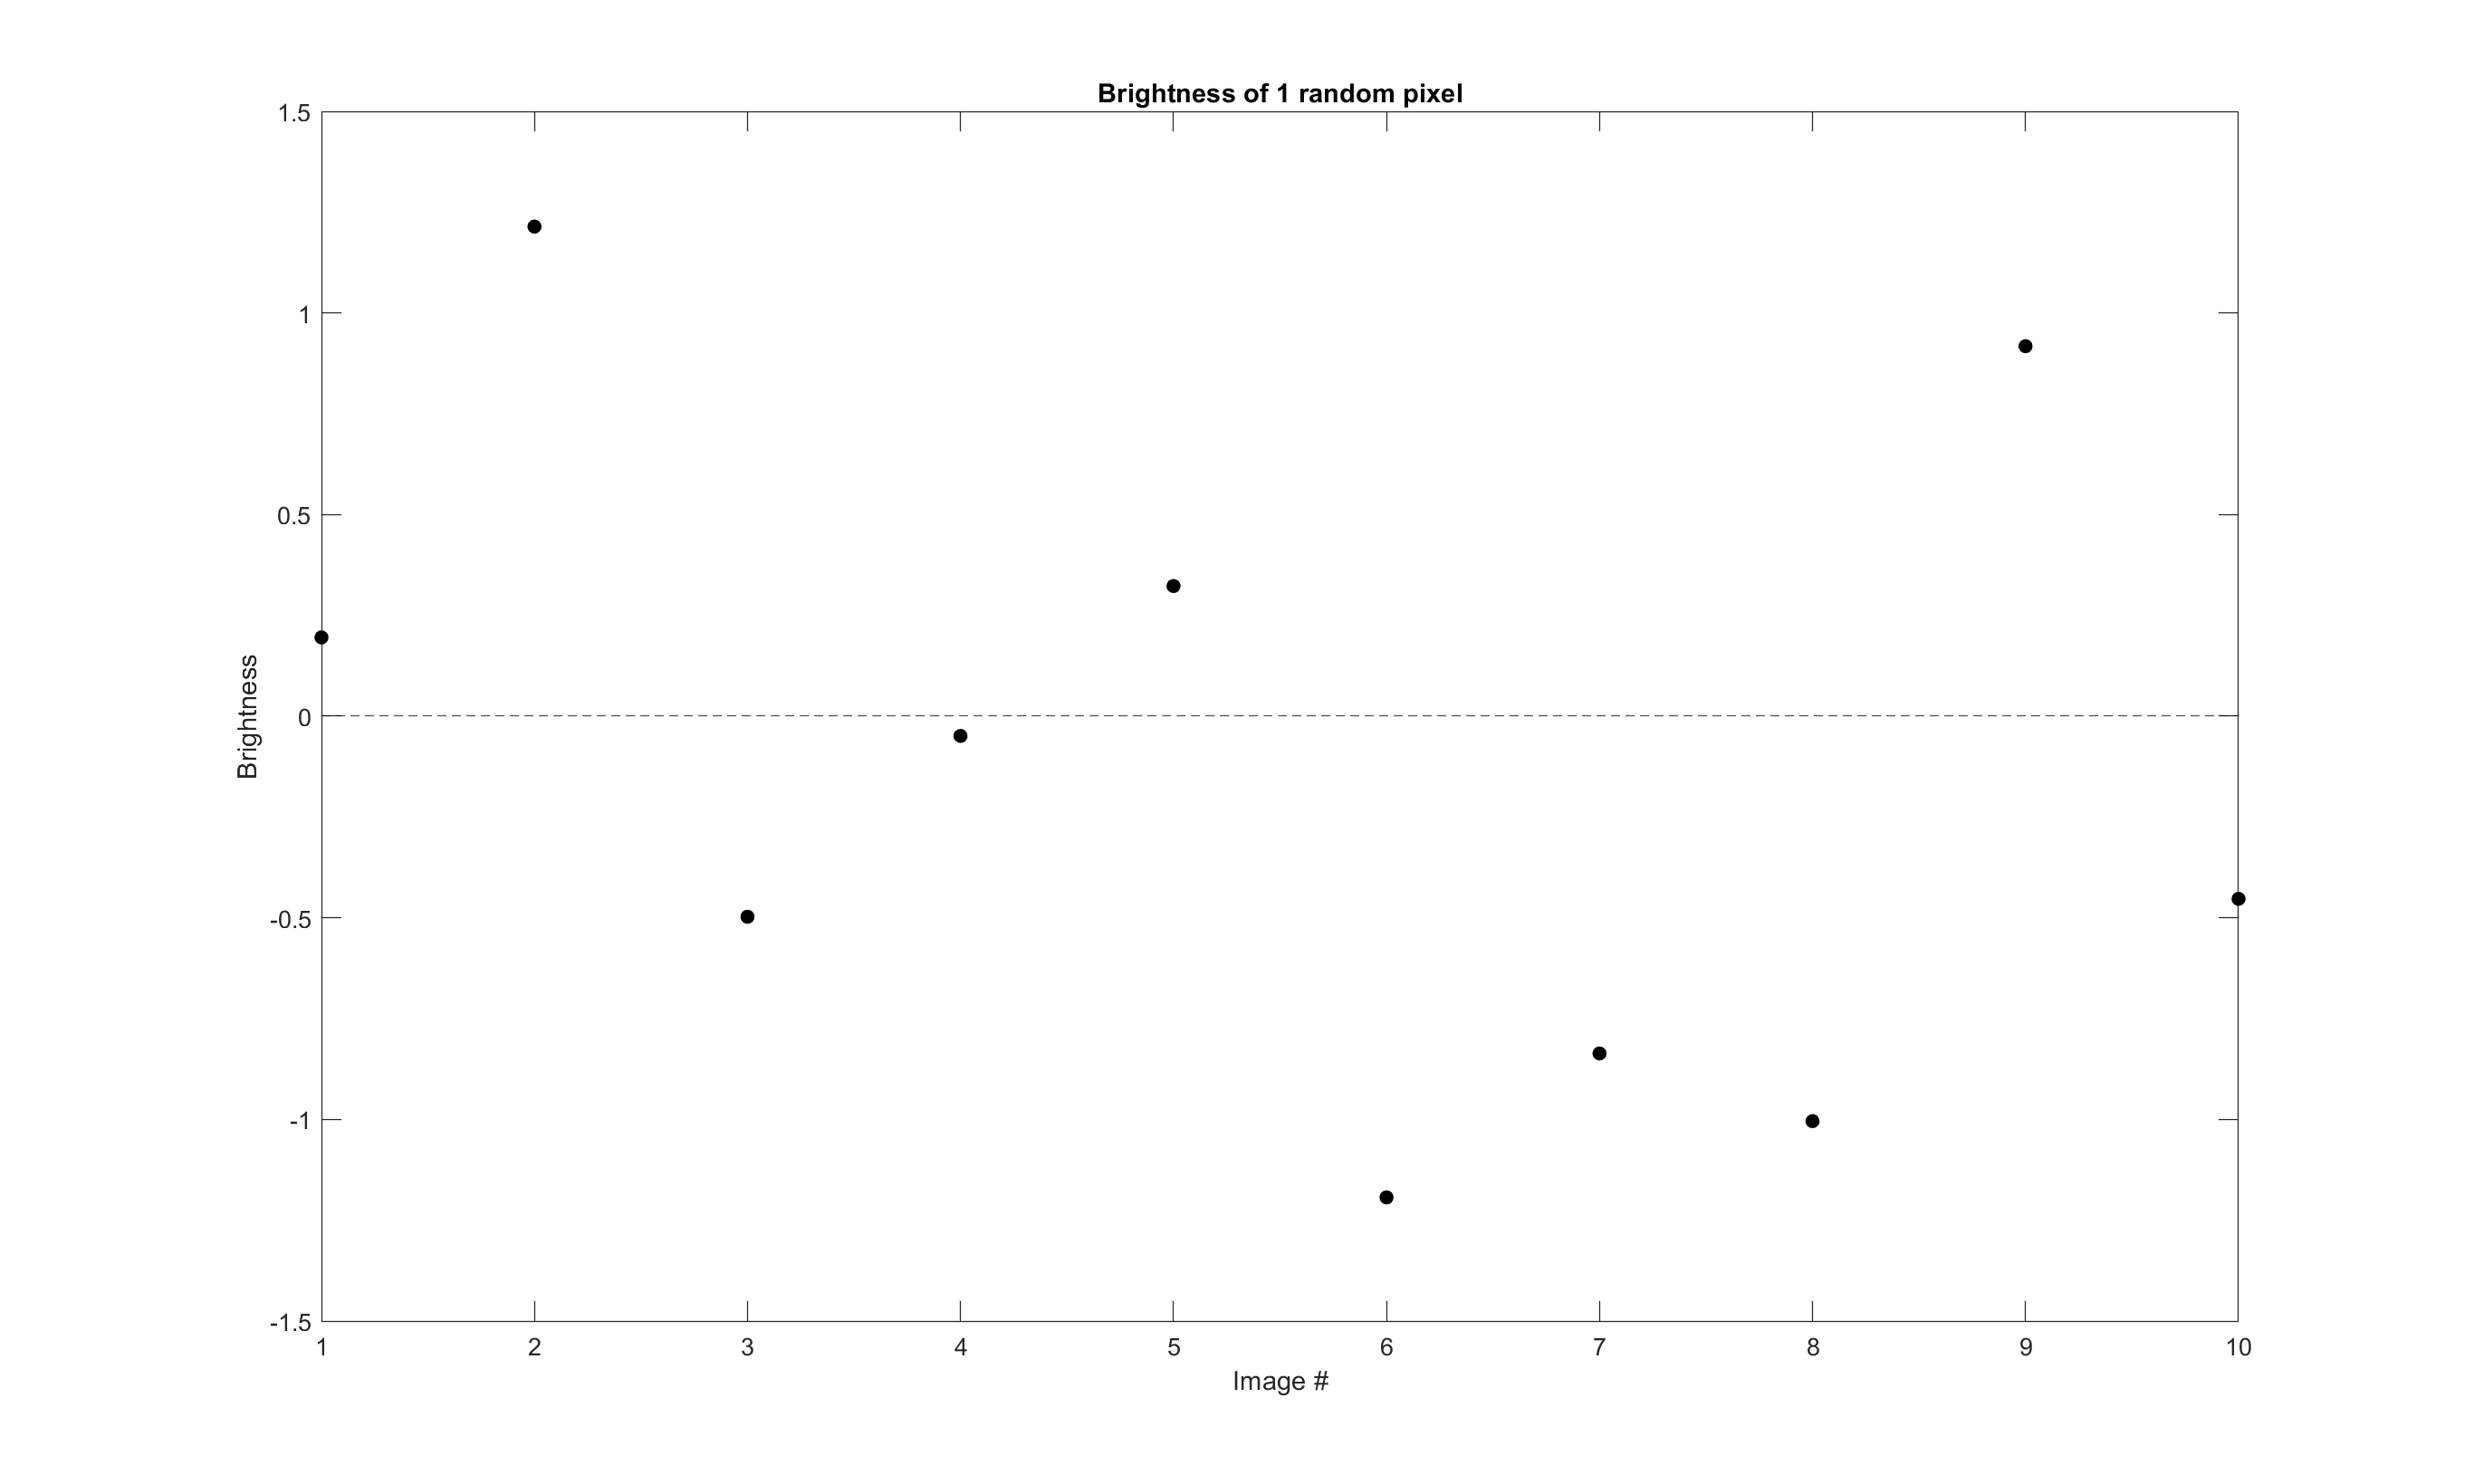

pixel_values = zeros(1, 10);
for ii = 1:10
    pixel_values(ii) = mydata(ii, pixel(1), pixel(2));
end

clf;
plot(1:10, pixel_values, 'k.', 'MarkerSize', 20), hold on;
yline(0, 'k--');
title('Brightness of 1 random pixel')
xlabel('Image #')
ylabel('Brightness')

We can also observe the fluctuations in the brightness of stars over time. For example, observing the brightest star from image 1 over each image:

[brightness, bright_star] = max(reshape(image1, 1, []))

brightness = 46.0118

bright_star = 7202

[bright_star_x, bright_star_y] = ind2sub([200, 200], bright_star)

bright_star_x = 2

bright_star_y = 37

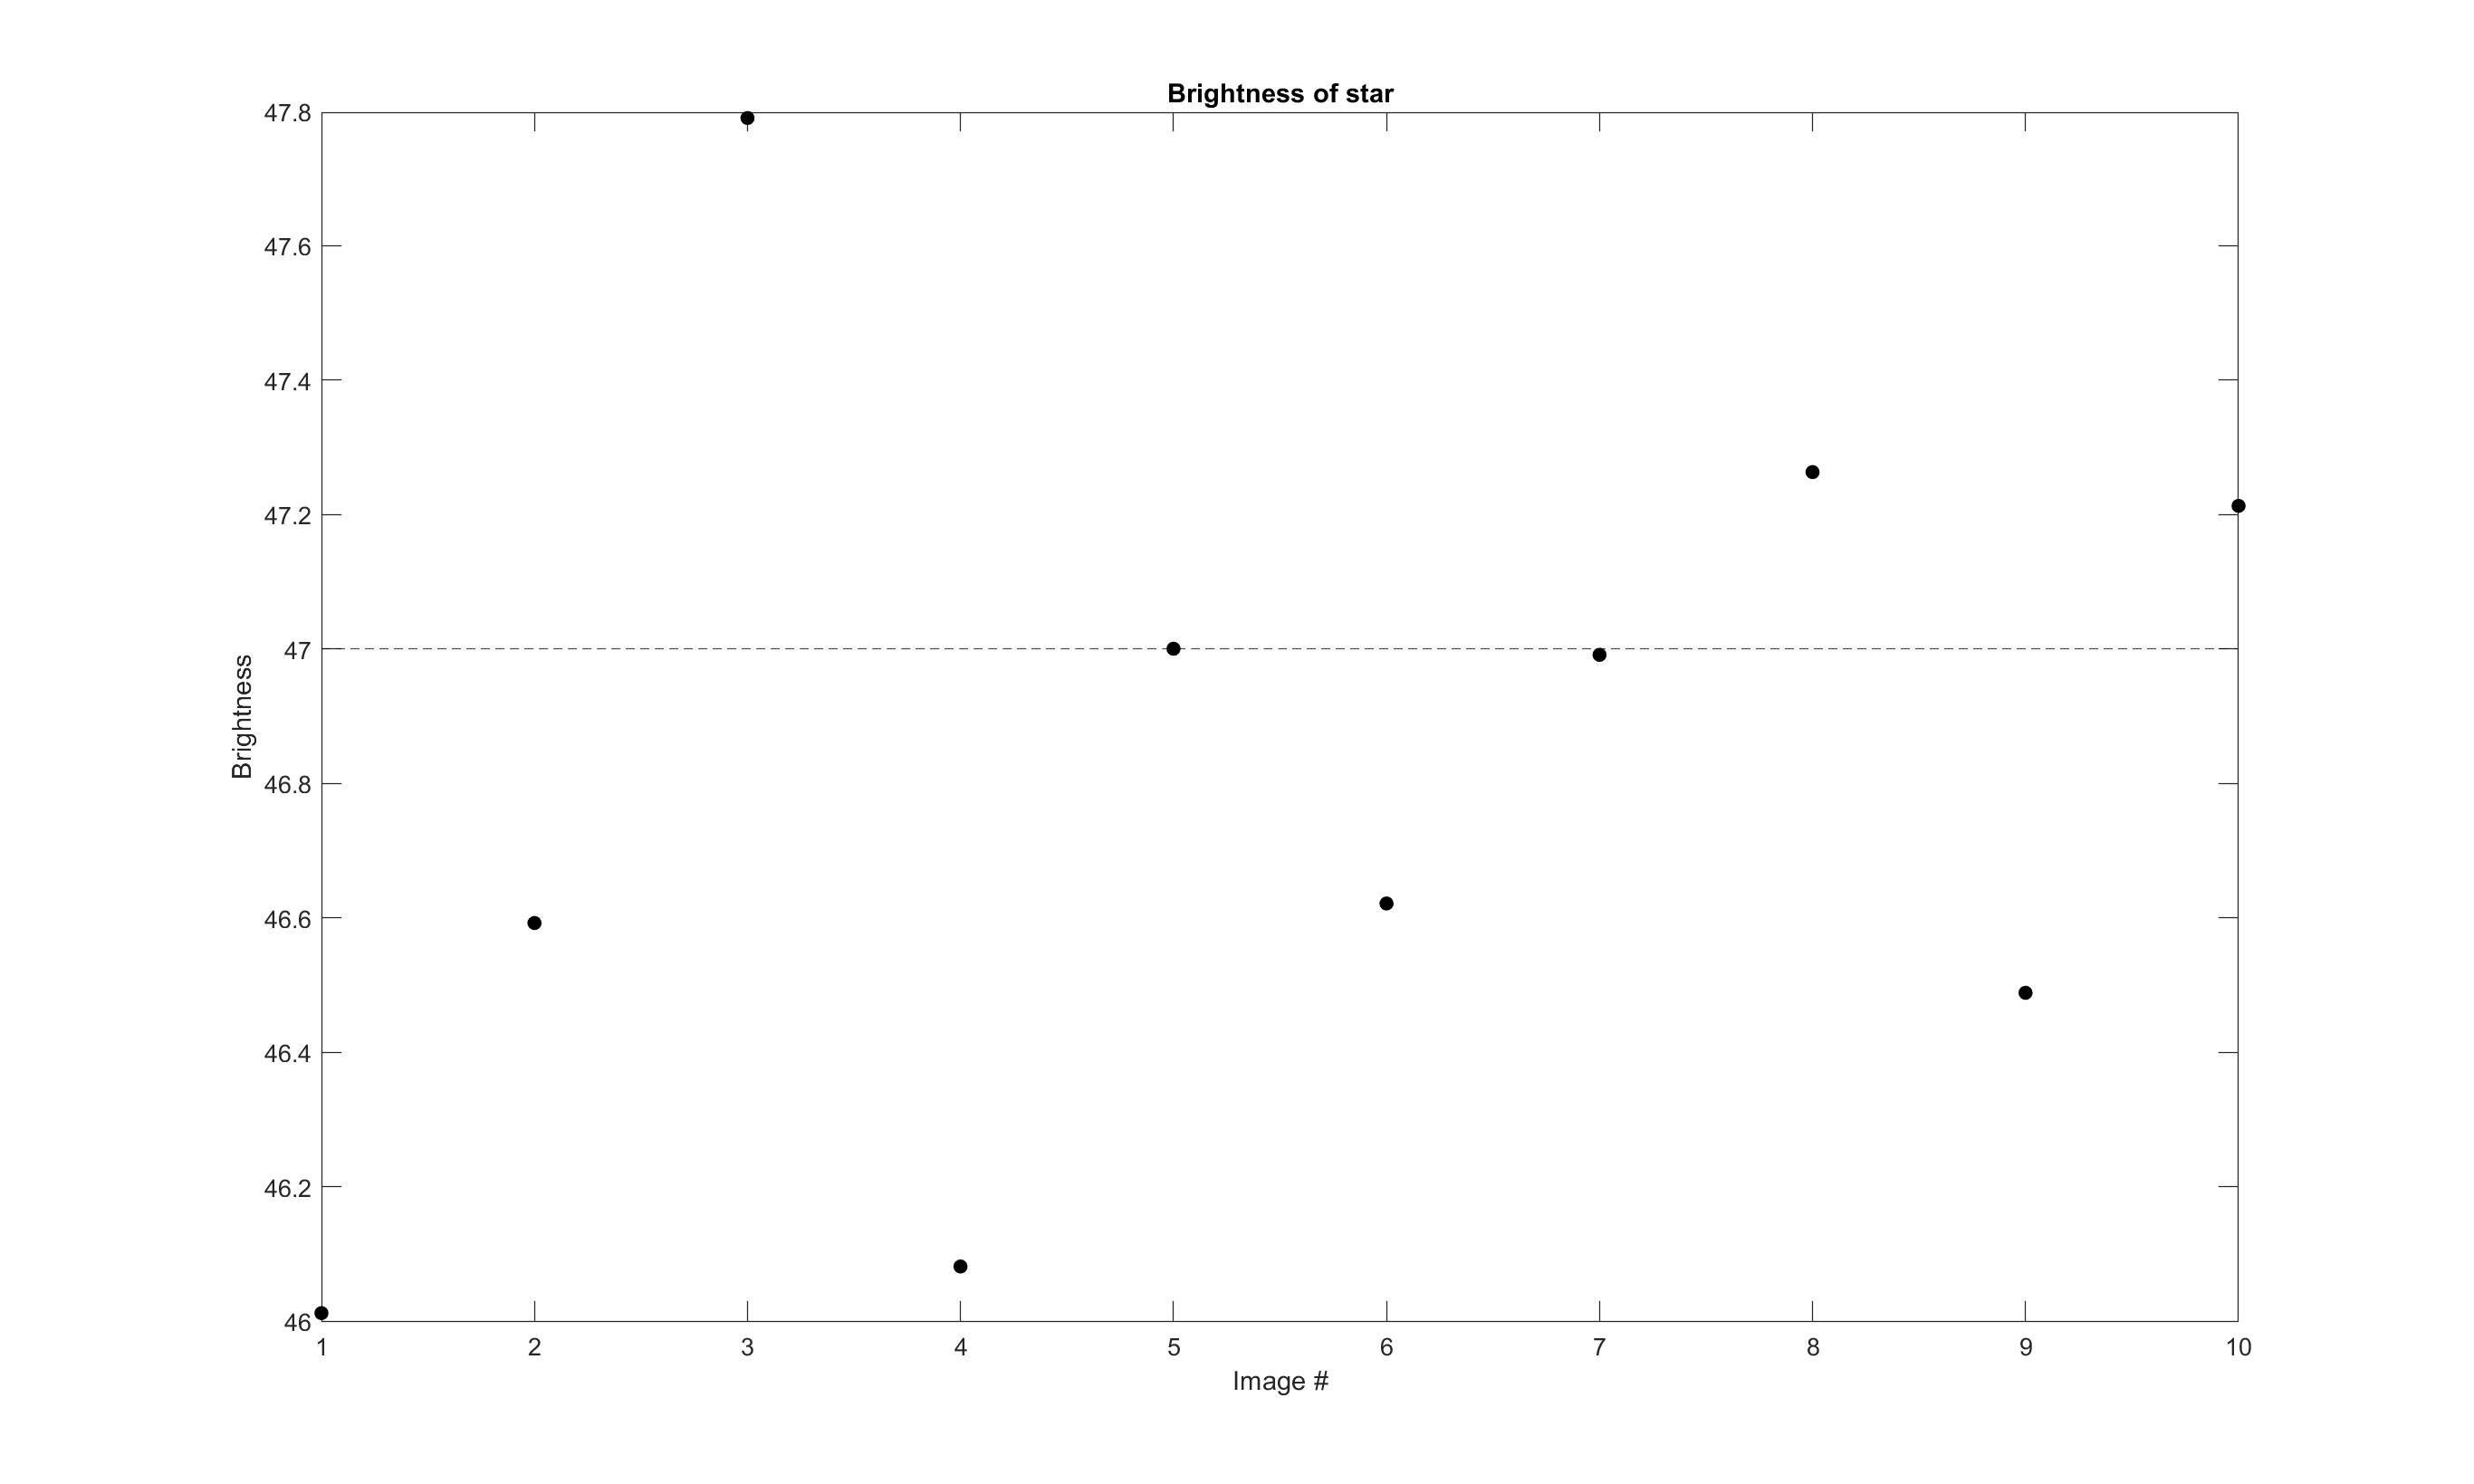

star_values = zeros(1, 10);
for ii = 1:10
    star_values(ii) = mydata(ii, bright_star_x, bright_star_y);
end

clf;
plot(1:10, star_values, 'k.', 'MarkerSize', 20);
yline(47, 'k--');
title('Brightness of star')
xlabel('Image #')
ylabel('Brightness')

We also would like to observe the spatial distribution of the data within each image. If the data is evenly distributed among all the pixels, then each row znd each column should have a similar total brightness with every other row and column. By plotting the sums of the rows and columns of image 1, we can observe the data's spatial distributtion:

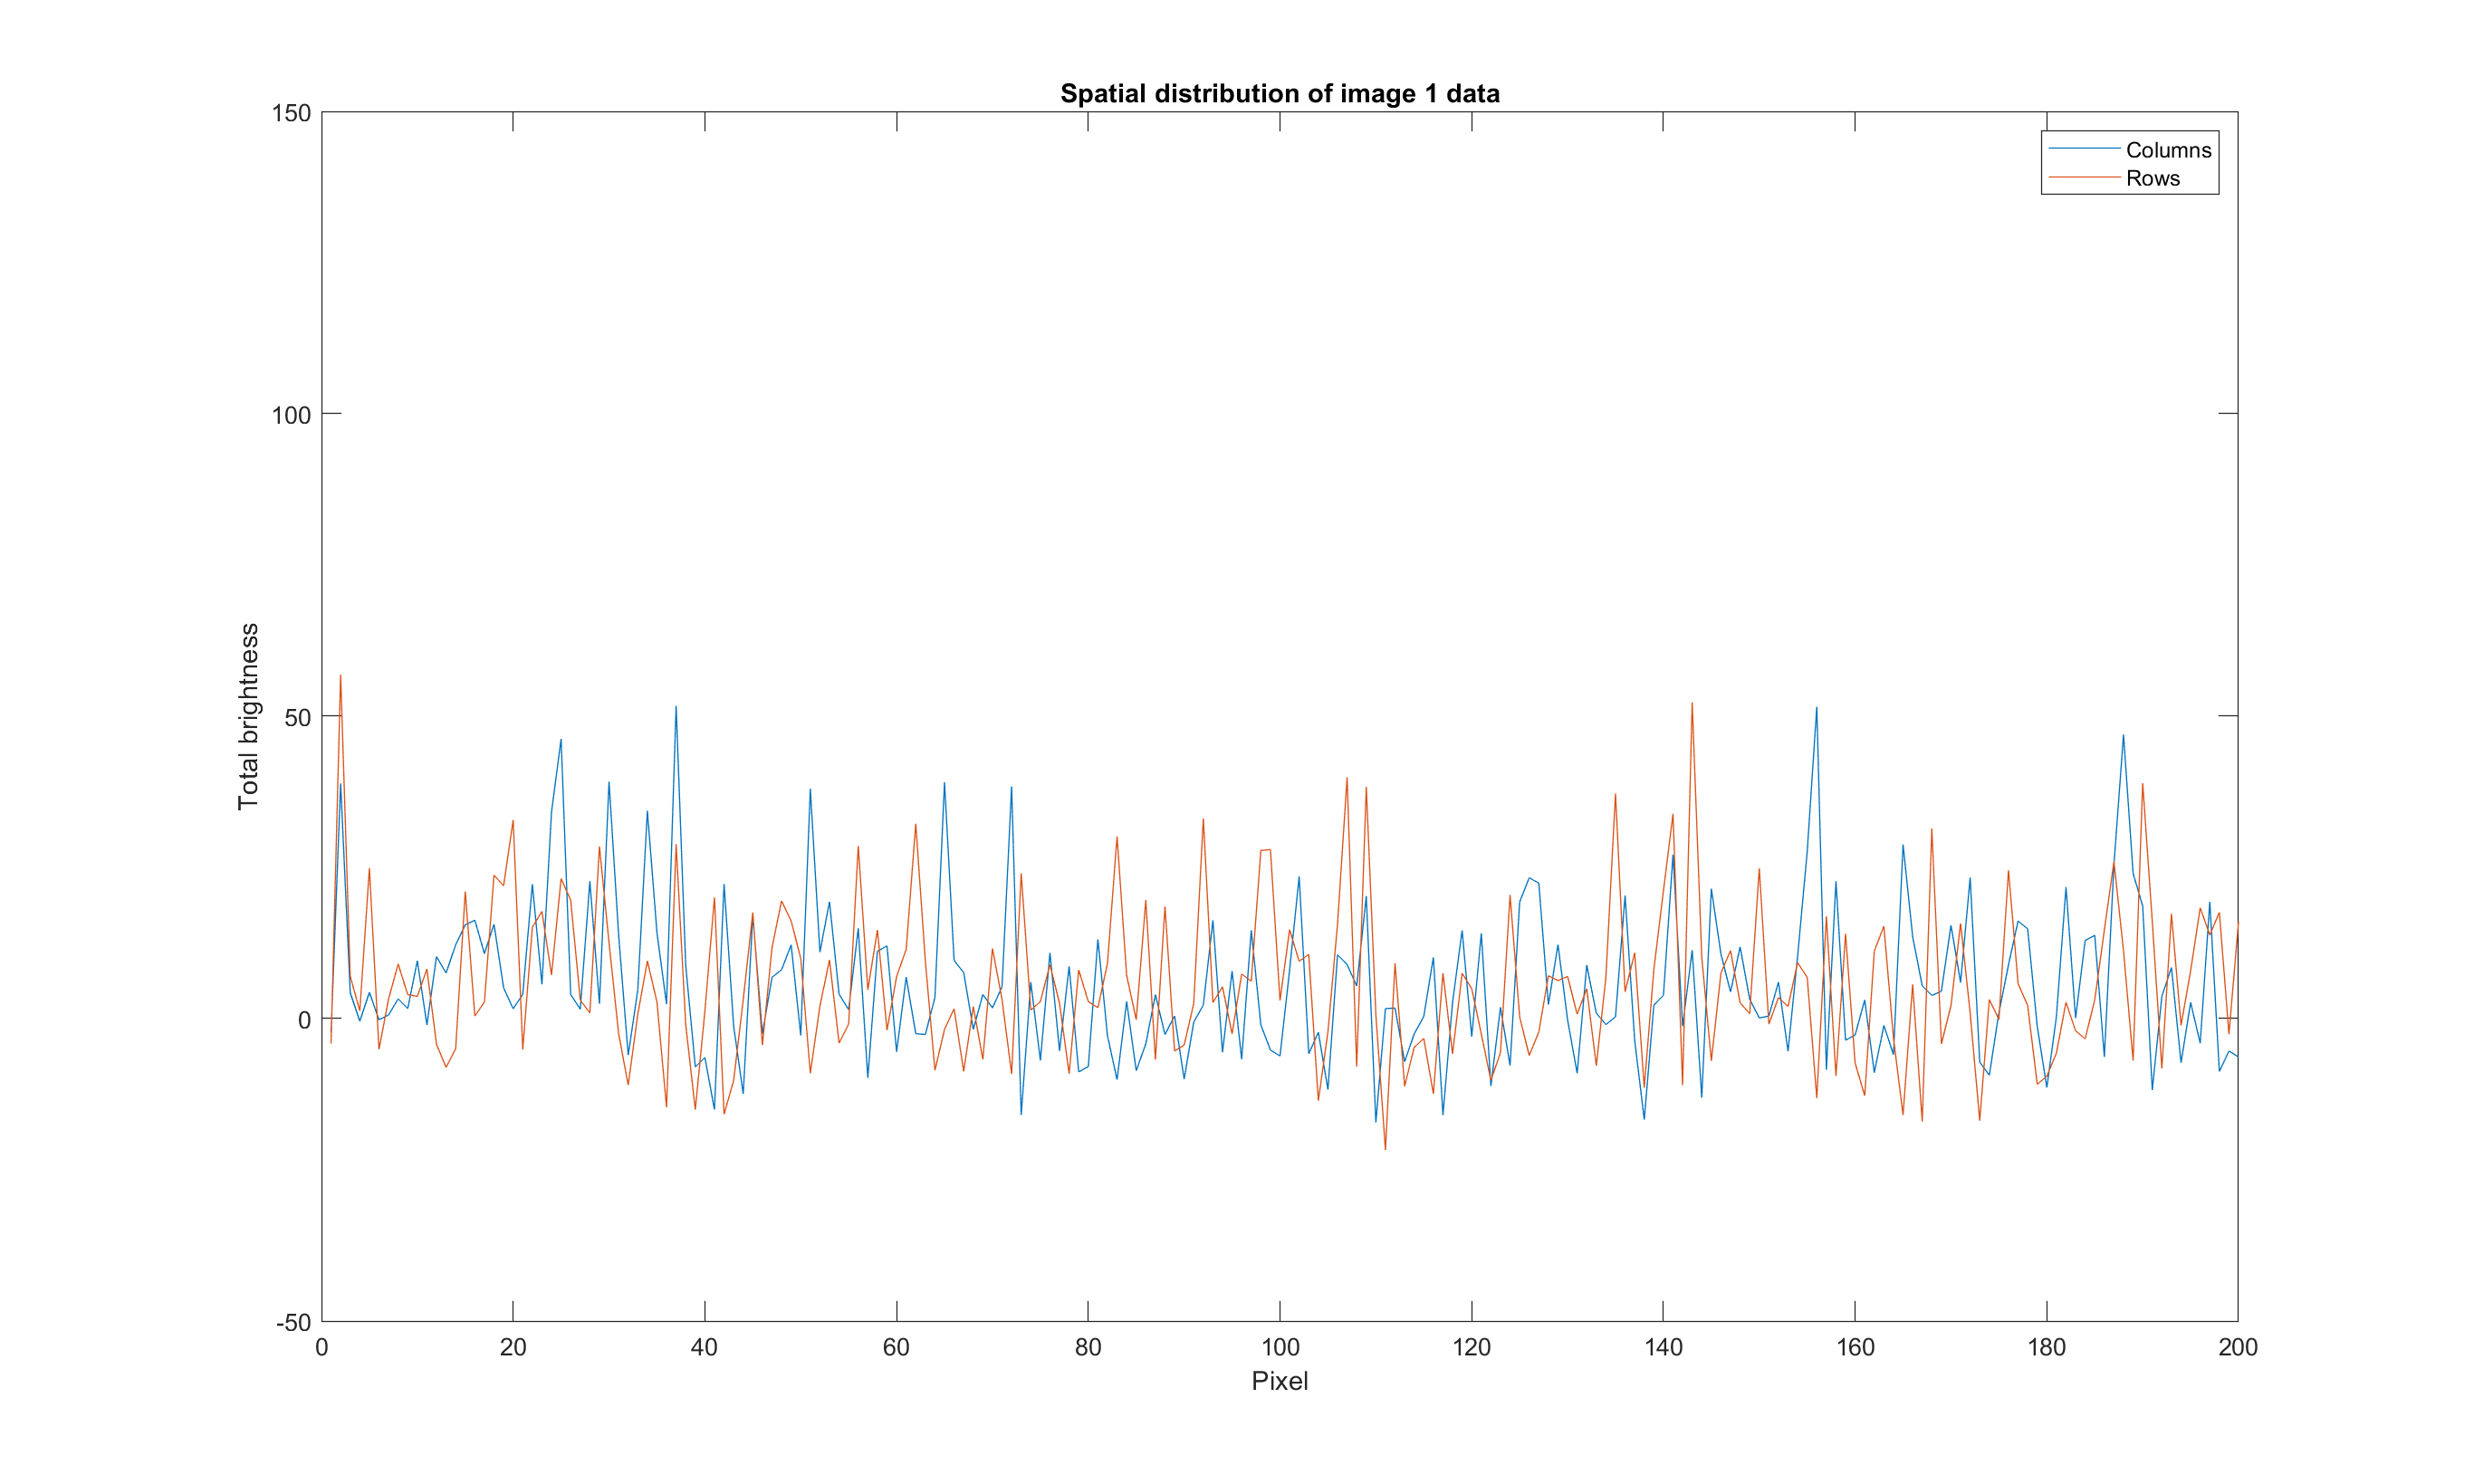

clf;
xs = sum(image1, 1);
ys = sum(image1, 2);
plot(1:200, xs), hold on;
plot(1:200, ys)
ylim([-50, 150])
title("Spatial distribution of image 1 data")
xlabel('Pixel')
ylabel('Total brightness')
legend('Columns', 'Rows')

We cannot observe any overall trend (more bright data towards any side or center of the image), so we can say that the data in this image is relatively evenly spatially distributed.

First let us establish the distribution of the background for this data, as well as establish what counts as a significant event.

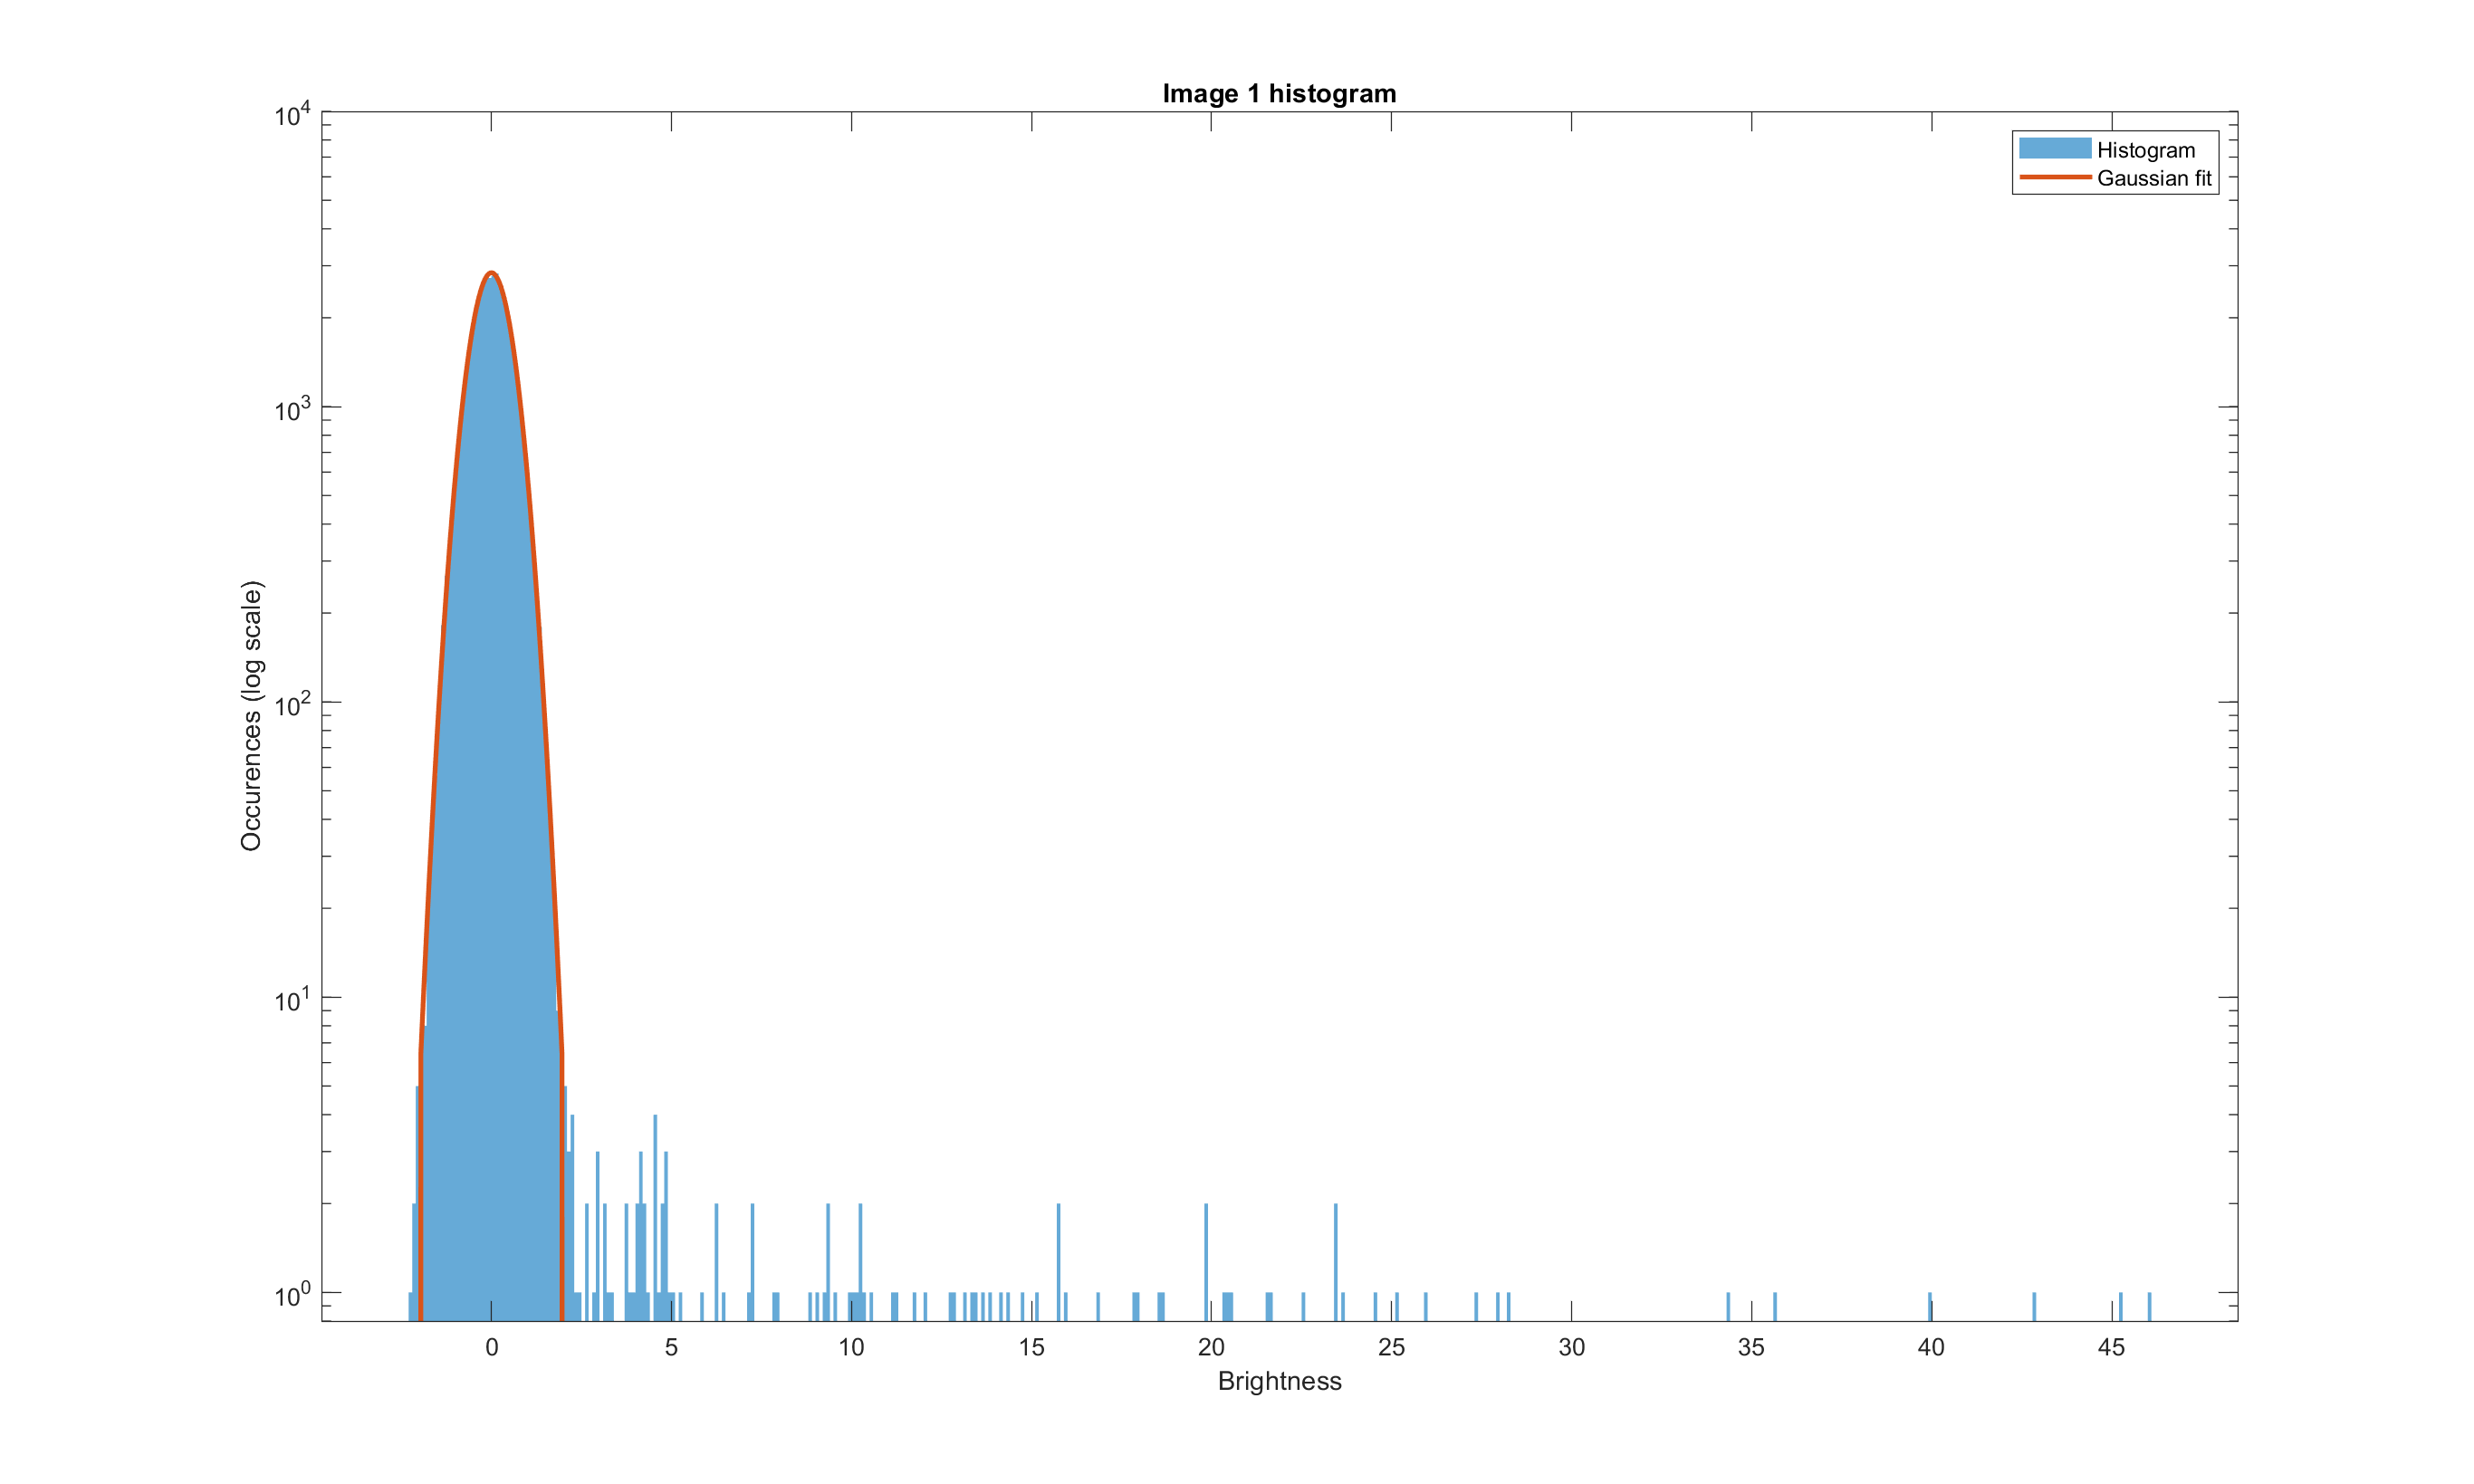

clf;

%%include spatial dependence and time dependence%%

histogram(image1, 'edgecolor', 'none'), hold on;
set(gca, 'YScale', 'log')
%find profile of background
bkg1 = image1(image1 < 2);
mean_bkg1 = 0;
std_bkg1 = std(bkg1);
xs = linspace(-2, 2, 100);
ys = normpdf(xs, mean_bkg1, std_bkg1) .* 4e3;
ys(1) = 1e-20;
ys(end) = 1e-20;
plot(xs, ys, 'Linewidth', 2)
ylim([.8 1e4])
title('Image 1 histogram');
xlabel('Brightness');
ylabel("Occurences (log scale)")
legend('Histogram', 'Gaussian fit');

The background of this data seems approximately Gaussian, as shown by the Gaussian fit curve in red. By removing the background, we can plot only the stars in our data.

We should consider anything with a brightness greater than $5\sigma$ away from the mean ($\mu =0$) to be significant. So, we remove everything less than $5\sigma$ from the distribution:

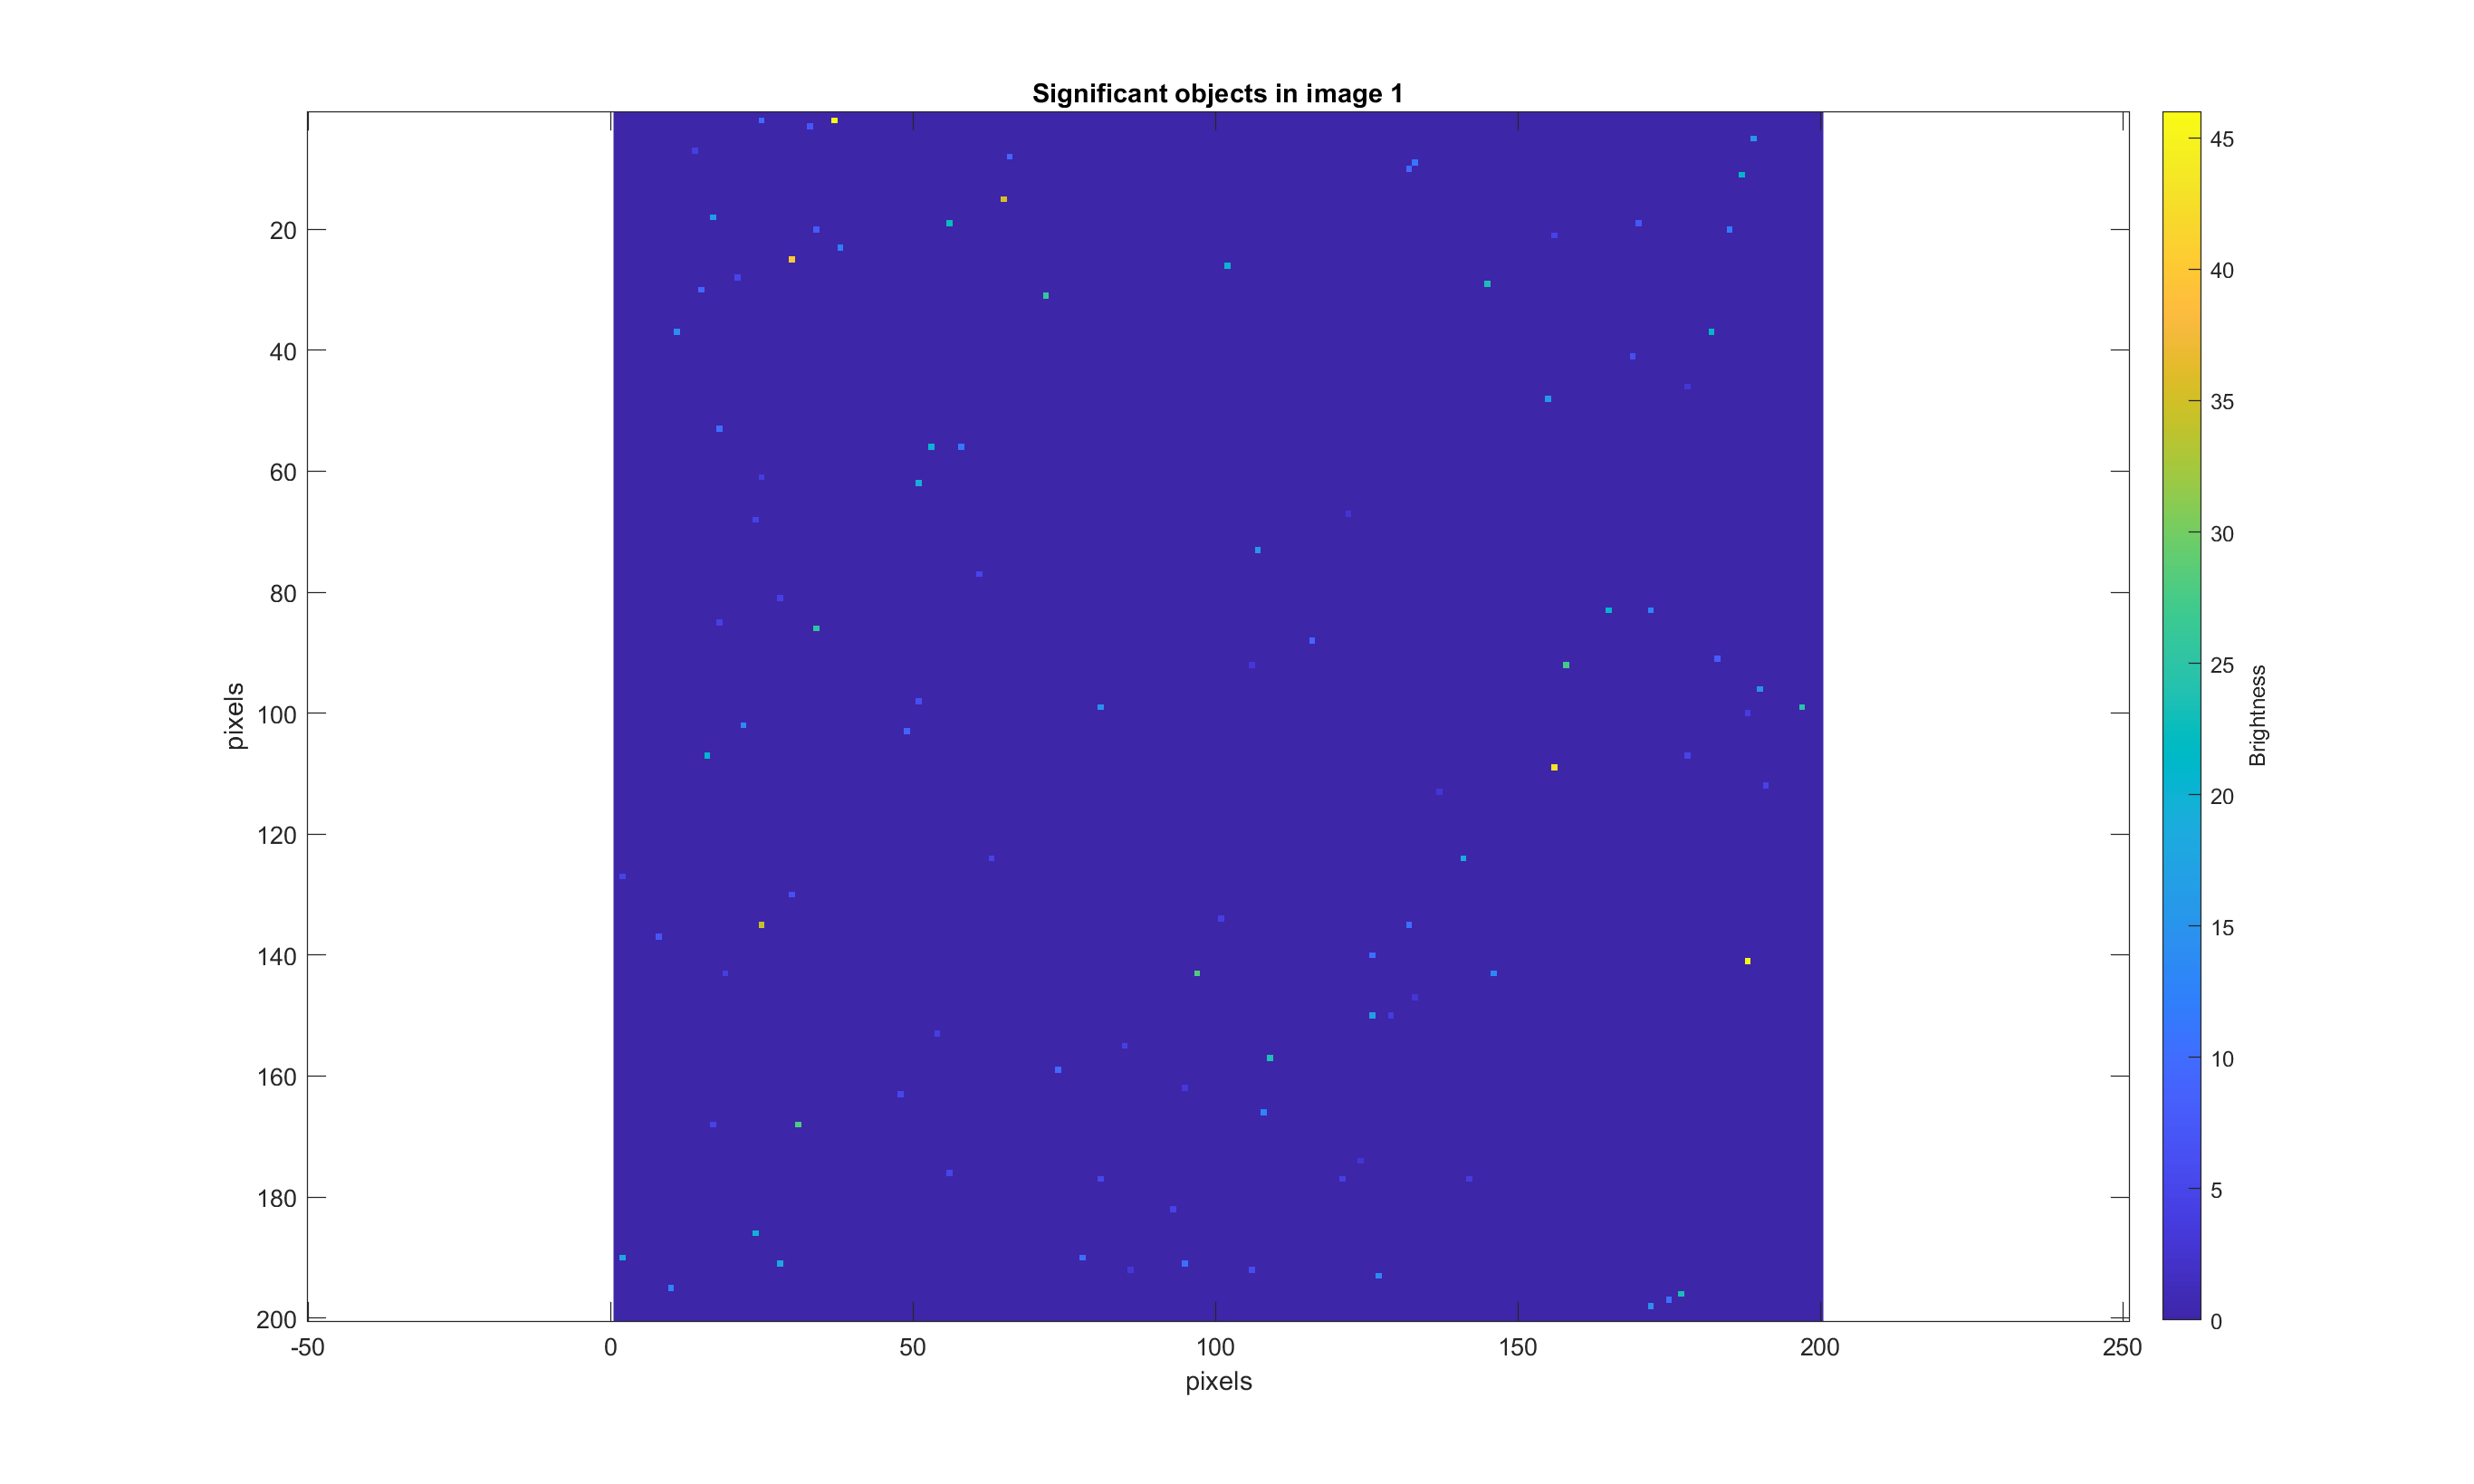

%plot only significant events:

clf;
N = 5;
image1_stars = image1 .* (image1 > N*std_bkg1 | image1 < -N*std_bkg1);
imagesc(image1_stars);
c = colorbar;
c.Label.String = 'Brightness';
axis equal;
title('Significant objects in image 1')
xlabel('pixels');
ylabel('pixels');

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

The background looks much cleaner. There are still some points in this data that are likely part of the background, but are bright enough to be greater than $5\sigma$ away from the mean.

We are interested in finding transients, or a significant signal which is in a certain location only for one image, such as a supernova. In order to do this, we would like to find the distribution according to the sum across all the images. This will sum all the stars and the background in all the images, but will also include any transients in any one image.

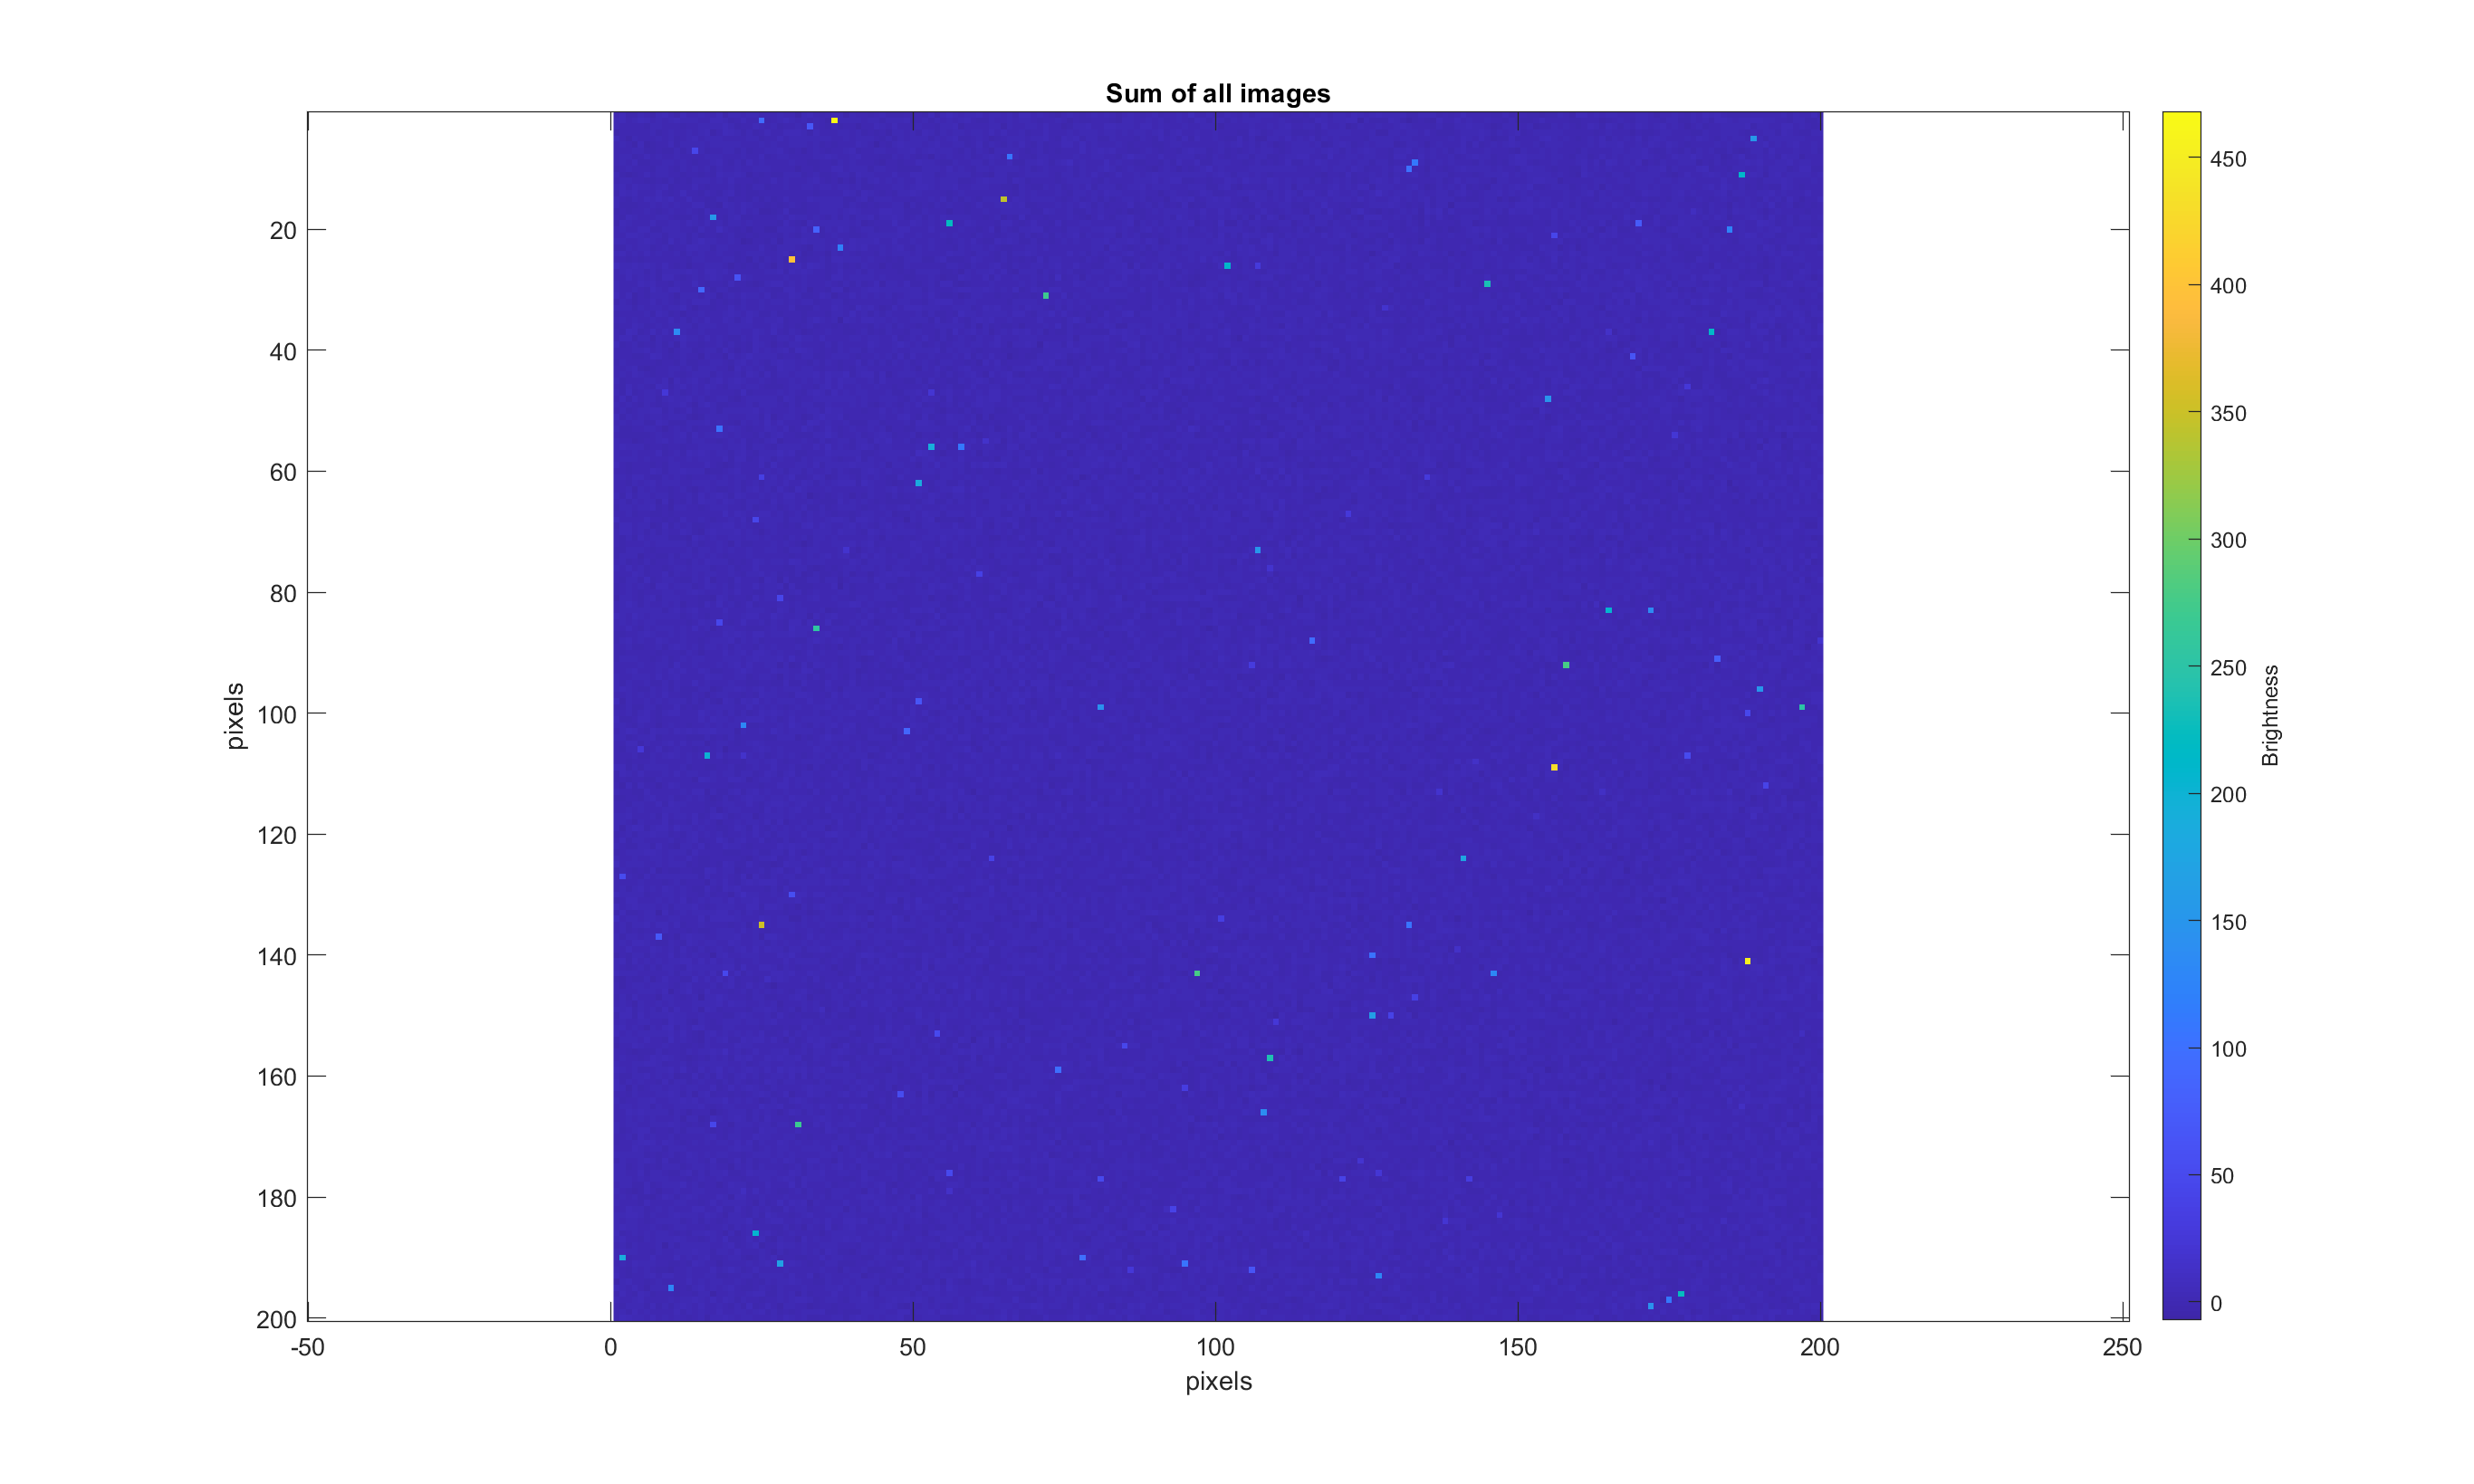

clf;

sum_dist = sum(mydata, 1);

imagesc(squeeze(sum_dist));
c = colorbar;
c.Label.String = 'Brightness';
axis equal;
title('Sum of all images')
xlabel('pixels');
ylabel('pixels');

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

Looking at the histogram for this sum image:

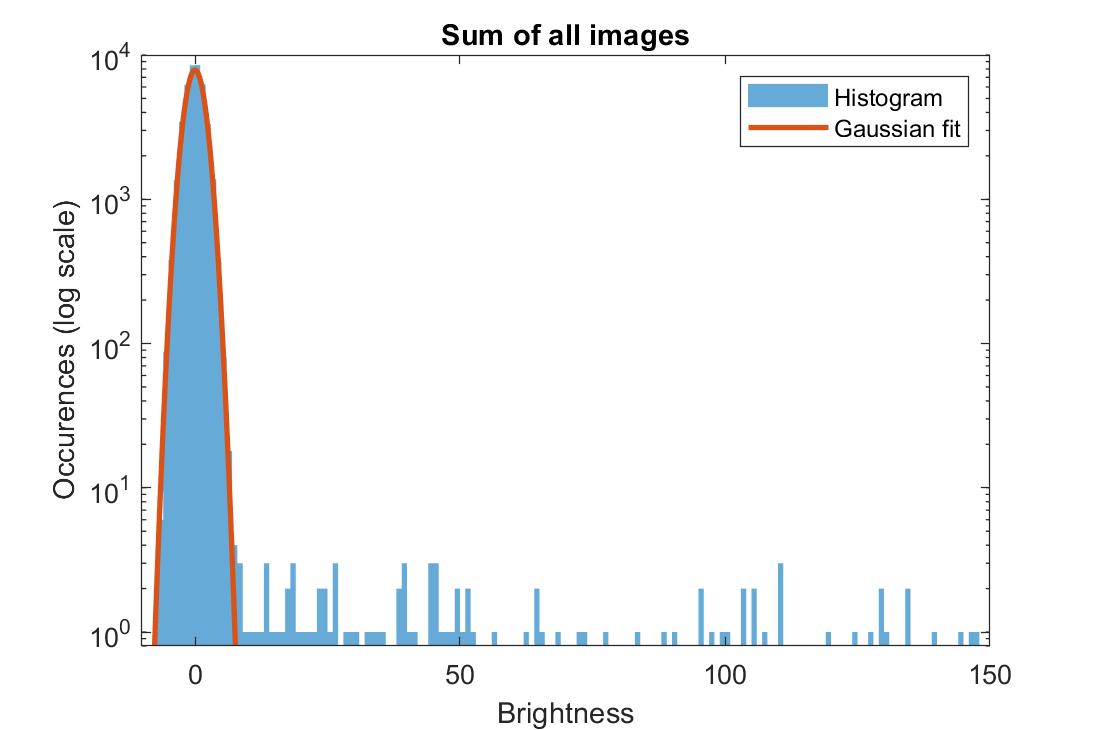

clf;
histogram(sum_dist, 'EdgeColor', 'none'), hold on;
set(gca, 'YScale', 'log')

%find profile of background
bkg = sum_dist(abs(sum_dist) < 10);
std_bkg_sum = std(bkg);
xs = linspace(-10, 10, 1000);
ys = normpdf(xs, 0, std_bkg_sum) .* 3.5e4;
plot(xs, ys, 'Linewidth', 2)
ylim([.8 1e4])
xlim([-10, 150])
title('Sum of all images')
xlabel('Brightness');
ylabel("Occurences (log scale)")
legend('Histogram', 'Gaussian fit');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 0.4, 0.4]);

The background of this image (approximated by the Gaussian fit curve in red) is much wider than that of image 1. This is because the sum of two normal distributions is a normal distribution with $\mu =\mu_1 +\mu_2$ and standard deviation $\sigma =\sqrt{\sigma_1^2 +\sigma_2^2 }$. Since the mean of the background distribution for each image is 0, and assuming the standard deviation for the background of each image is nearly the same (the background for each image is a random, Gaussian distributed set of values with small fluctuations in value), the final distribution should have $\mu_s =0$ and $\sigma_s =\sqrt{\sum_{i=1}^{10} \sigma_i^2 }=\sqrt{10{\;\sigma }^2 }=\sqrt{10}\sigma$.

std_bkg_sum

std_bkg_sum = 1.7784

sqrt(10) * std_bkg1

ans = 1.7760

Now we will select only the significant objects from this data ($5\sigma$ away from the mean or greater), using the same process as before.

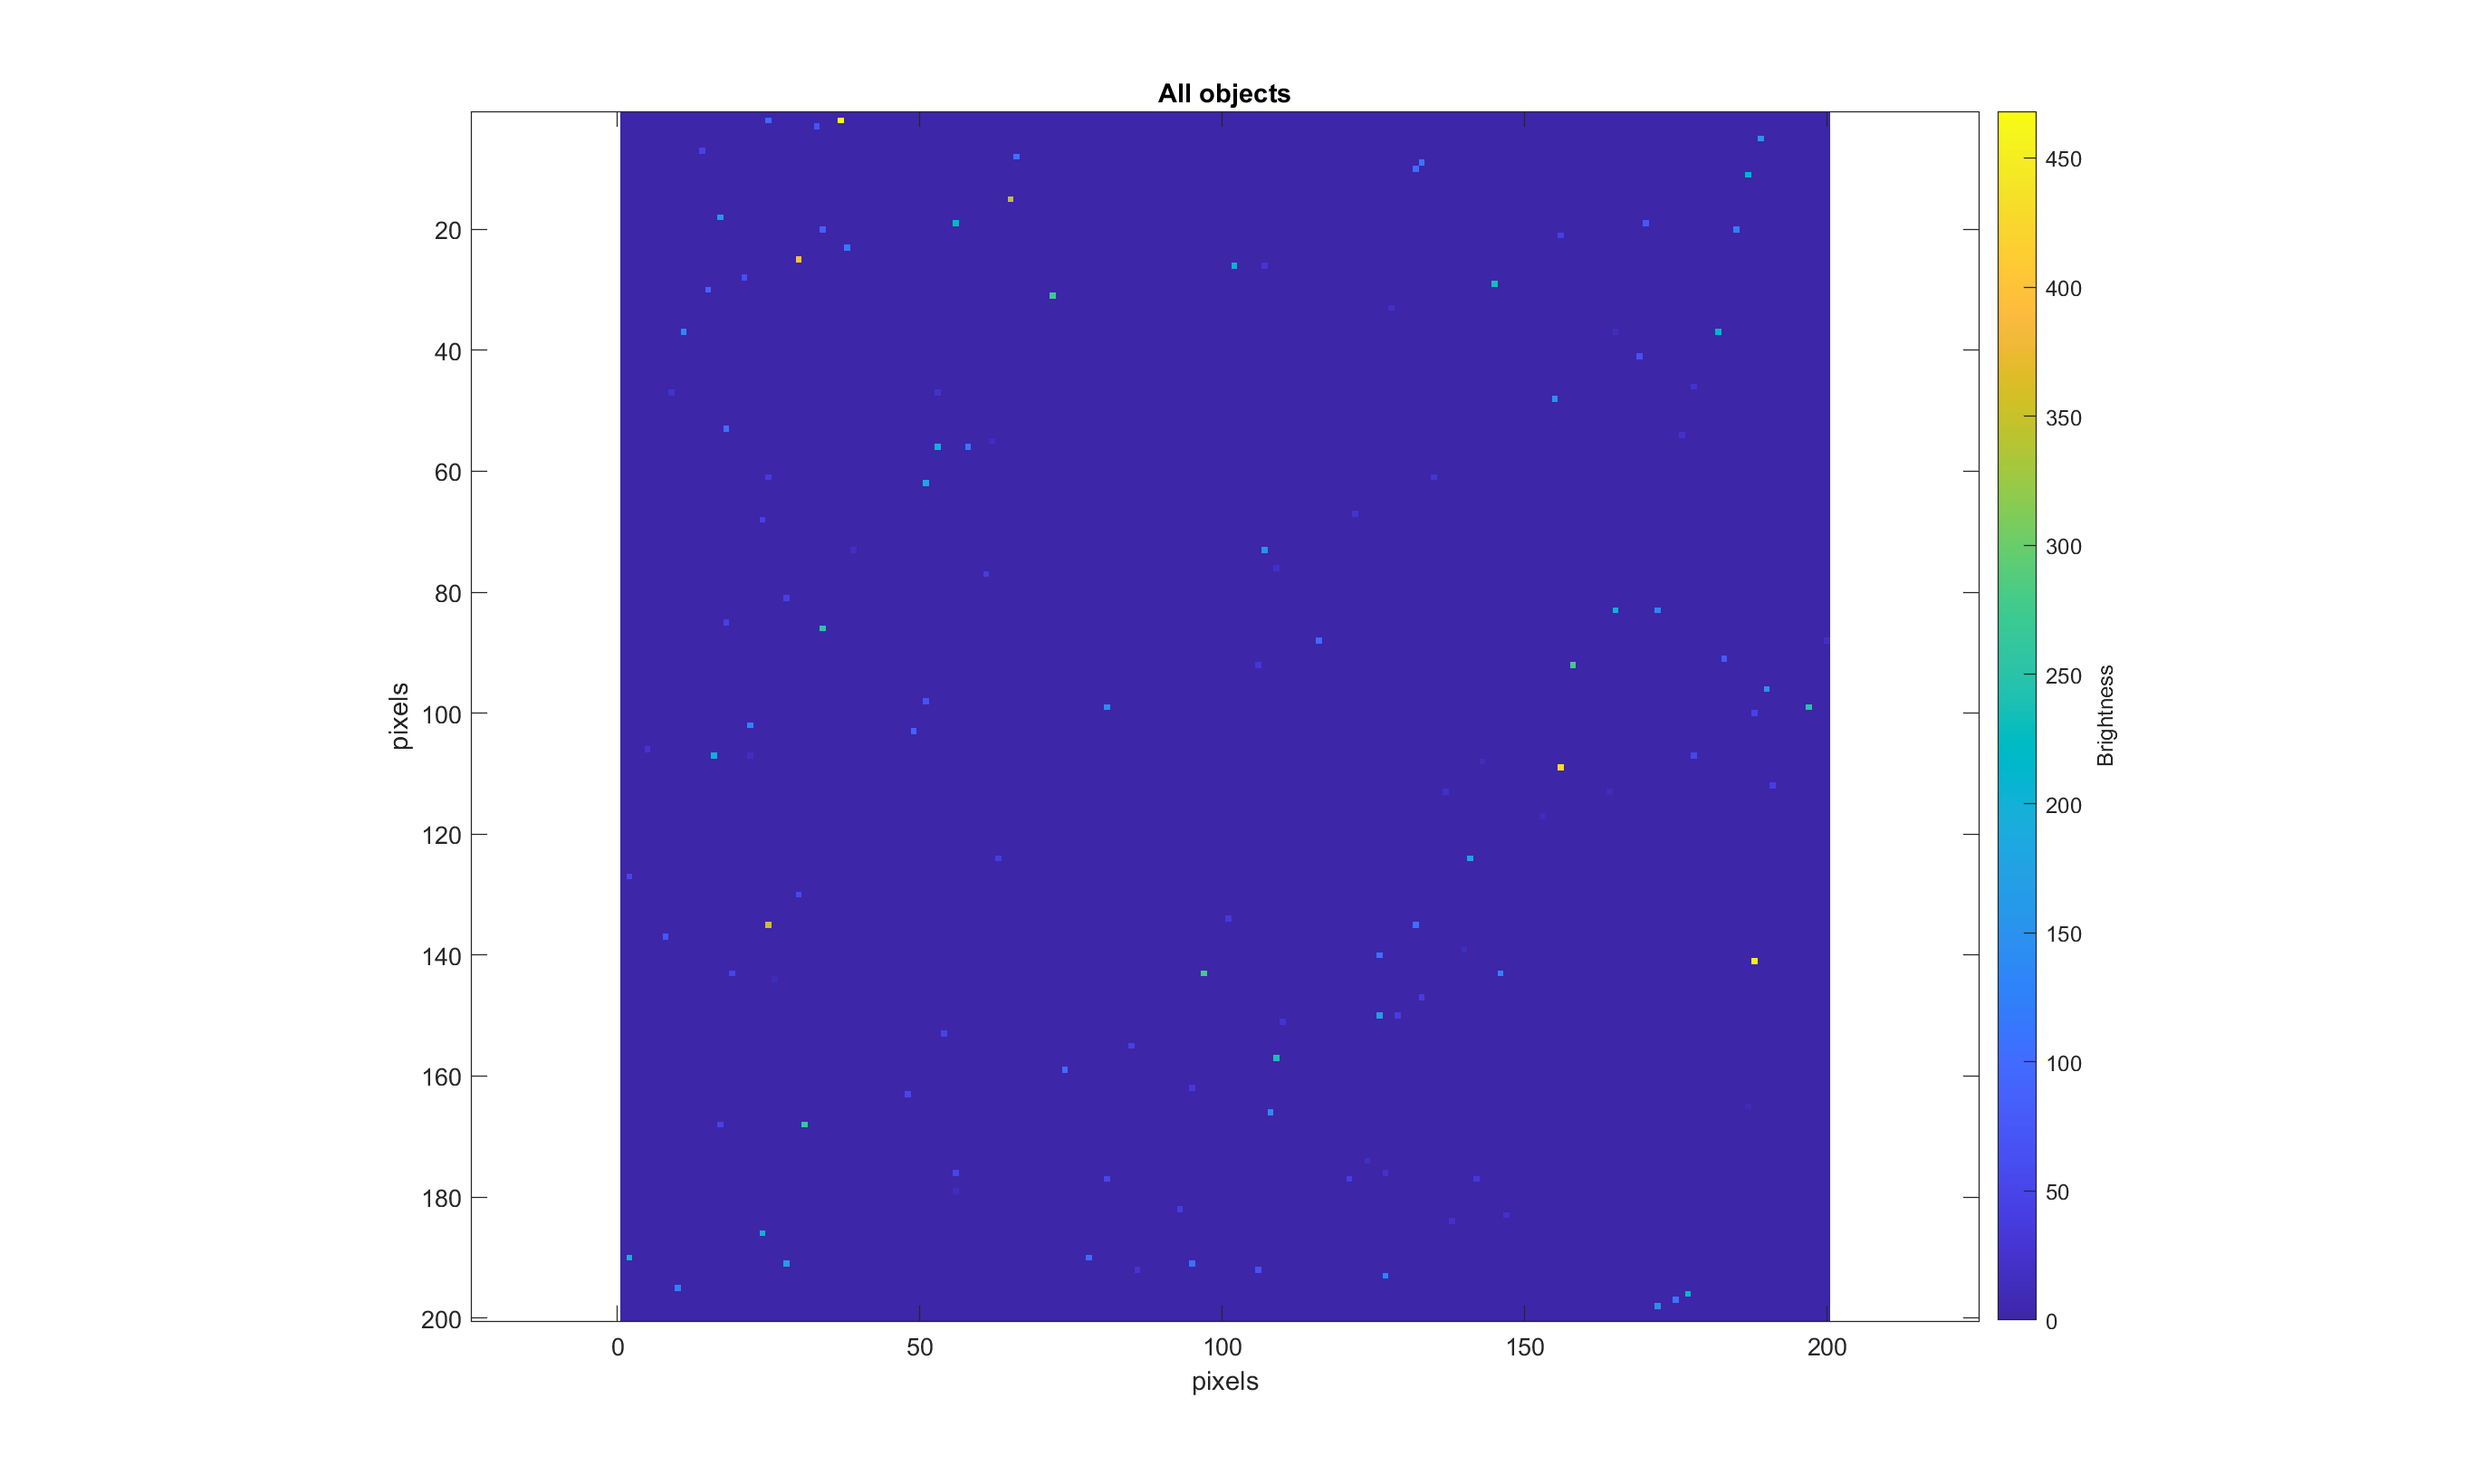

%only choose 5 sigma events
N = 5;
all_objects = sum_dist .* (sum_dist > N*std_bkg_sum | sum_dist < -N*std_bkg_sum);

clf;
imagesc(squeeze(all_objects));
c = colorbar;
c.Label.String = 'Brightness';
axis equal;
title('All objects');
xlabel('pixels');
ylabel('pixels');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

We still need to further refine our selection criteria to discover a transient signal. We know that a transient will never be brighter than the brightest star in any image, so we can remove any objects with a brightness greater than this:

[brightness, brightest_star] = max(reshape(mydata, 1, []))

brightness = 47.7901

brightest_star = 72013

[brightest_star_image, brightest_star_x, brightest_star_y] = ind2sub([10, 200, 200], brightest_star)

brightest_star_image = 3

brightest_star_x = 2

brightest_star_y = 37

Note that this is the same star as the brightest star in image 1 that we saw earlier. Therefore, we know that this is not a transient object itself, since it appears in multiple images.

transient_candidates = all_objects .* (all_objects < brightness);
candidates = find(transient_candidates);
num_candidates = length(candidates)

num_candidates = 49

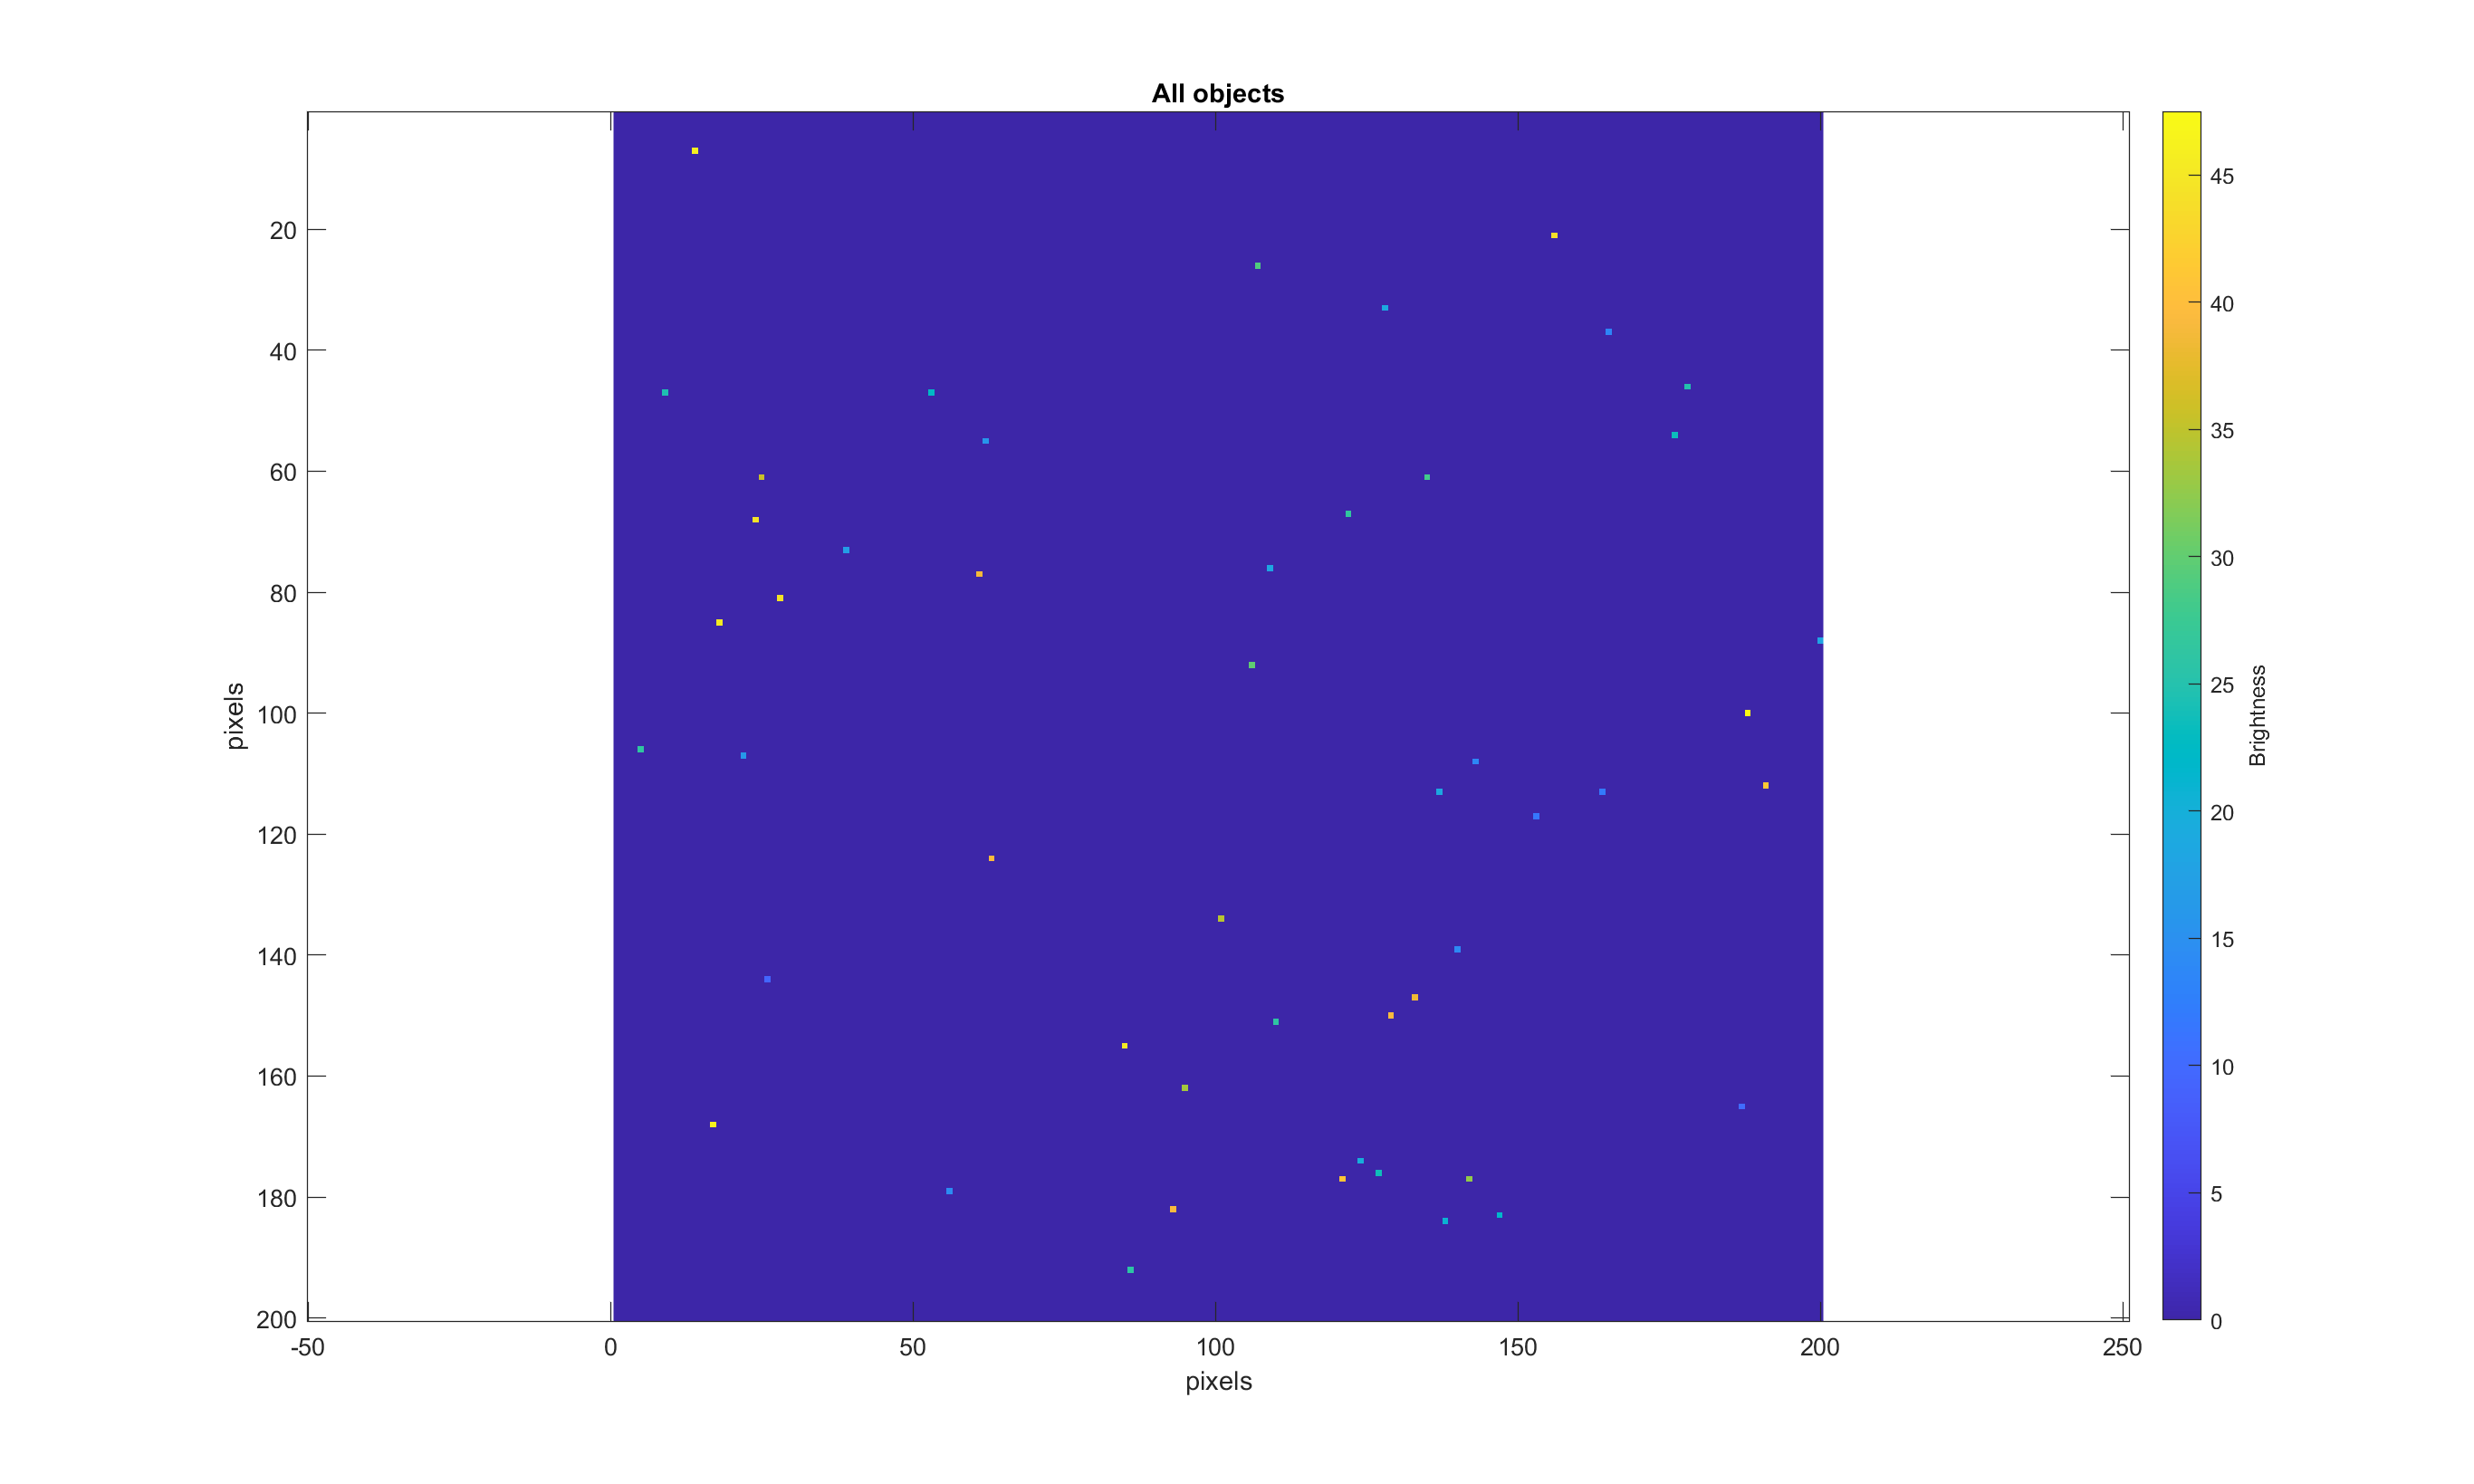


clf;
imagesc(squeeze(transient_candidates));
c = colorbar;
c.Label.String = 'Brightness';
axis equal;
title('All objects');
xlabel('pixels');
ylabel('pixels');

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

What we have now is a set of objects which are significant enough to be considered a signal, but have a low enough brightness to not be the sum of two or more stars. Since we have greatly reduced the number of objects we are looking at, what we can do now is compare the brightness of each of the objects in this summed distribution with the brightness of the same object in the individual images.

If an object in this data set is the sum of 10 data points from a star, then its brightness should be greater than 10 times the minimum brightness of the star among all the images. However, if the object is a transient in which it is a significant object in one image but part of the background in all others, its brightness should be nearly the same as the maximum  brightness of the point among all the images. By executing either of these tests, we can isolate the transients from the dim stars.

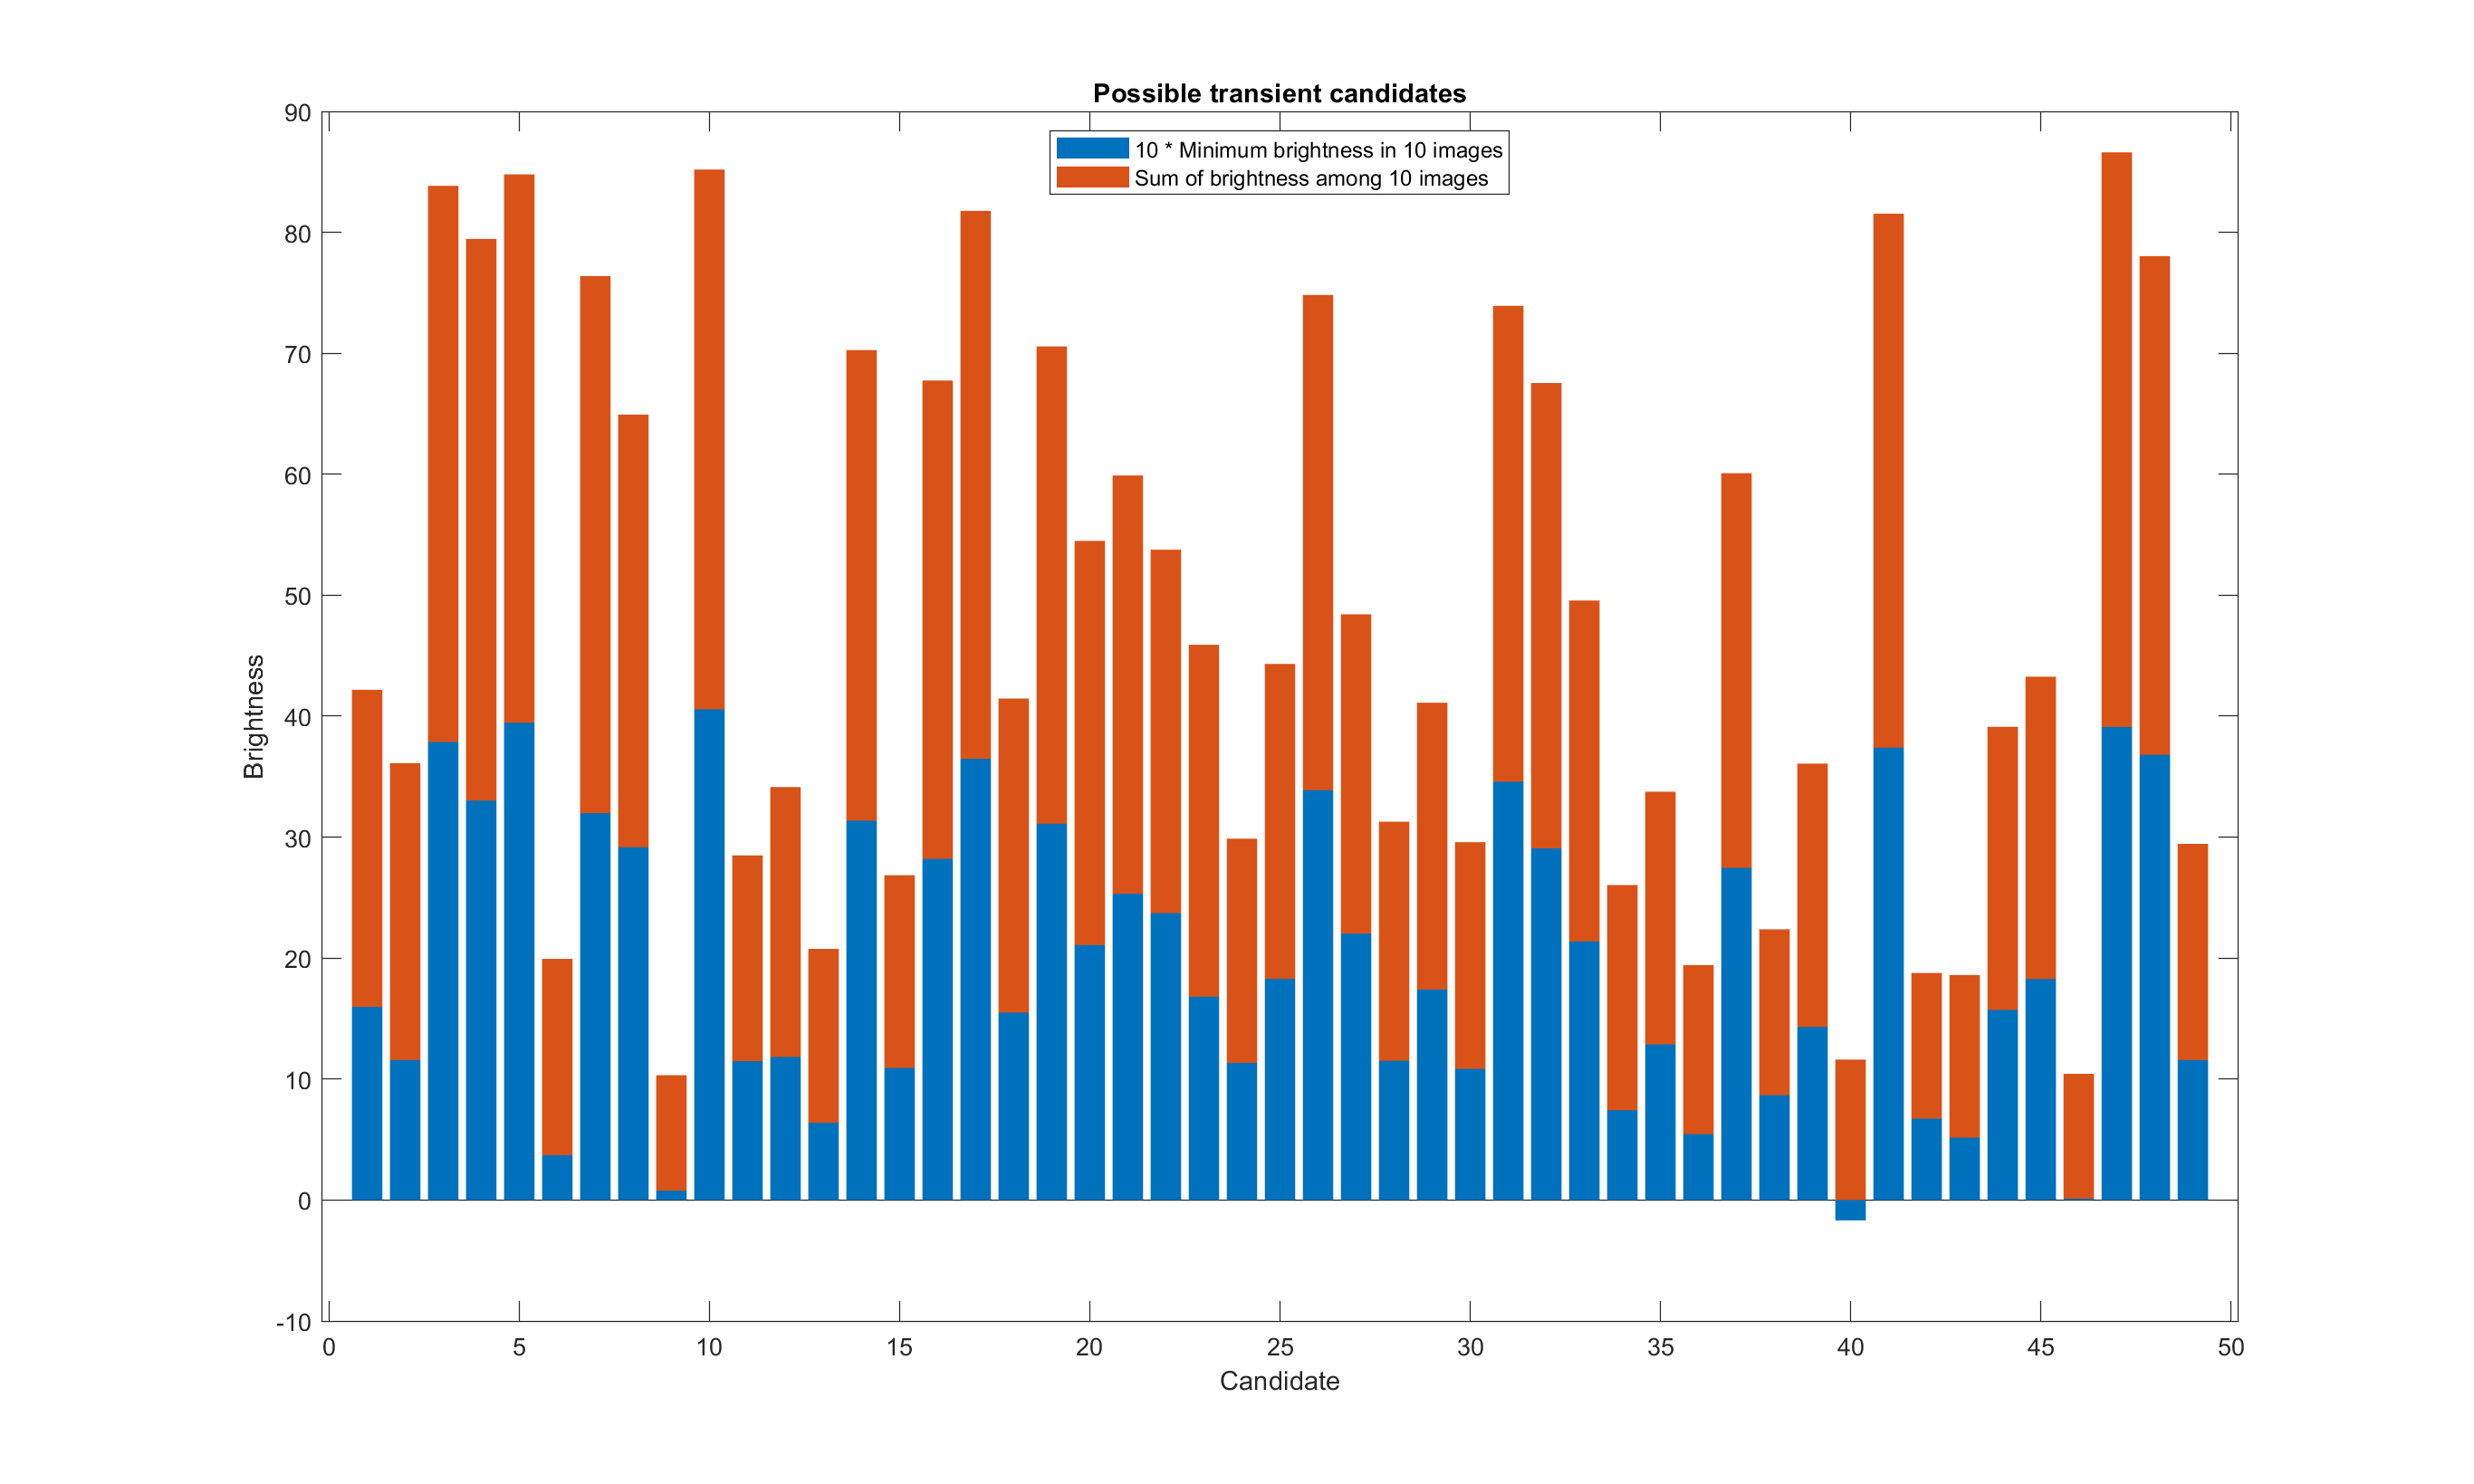

img_vs = zeros(10, 200*200);
for nn = 1:10
    
    img_vs(nn, :) = reshape(mydata(nn, :, :), 1, []);
end

min_objectdata = zeros(1,num_candidates);
for ii = 1:num_candidates
    min_objectdata(ii) = min(img_vs(:, candidates(ii)));
end

%[~, transient] = min(abs(max_objectdata))

clf;
bar(1:num_candidates, [10 .* min_objectdata;squeeze(sum_dist(candidates)')],'stacked', 'EdgeColor', 'none'), hold on;
title('Possible transient candidates')
xlabel('Candidate')
ylabel('Brightness')
legend('10 * Minimum brightness in 10 images', 'Sum of brightness among 10 images', 'location', 'north')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

We saw earlier that the brightness of one star can vary by as much as 1 unit over all 10 images. Since we are multiplying the value of the minimum brightness of an object by 10, we can discard objects that are within 10 units of brightness to their mean value.

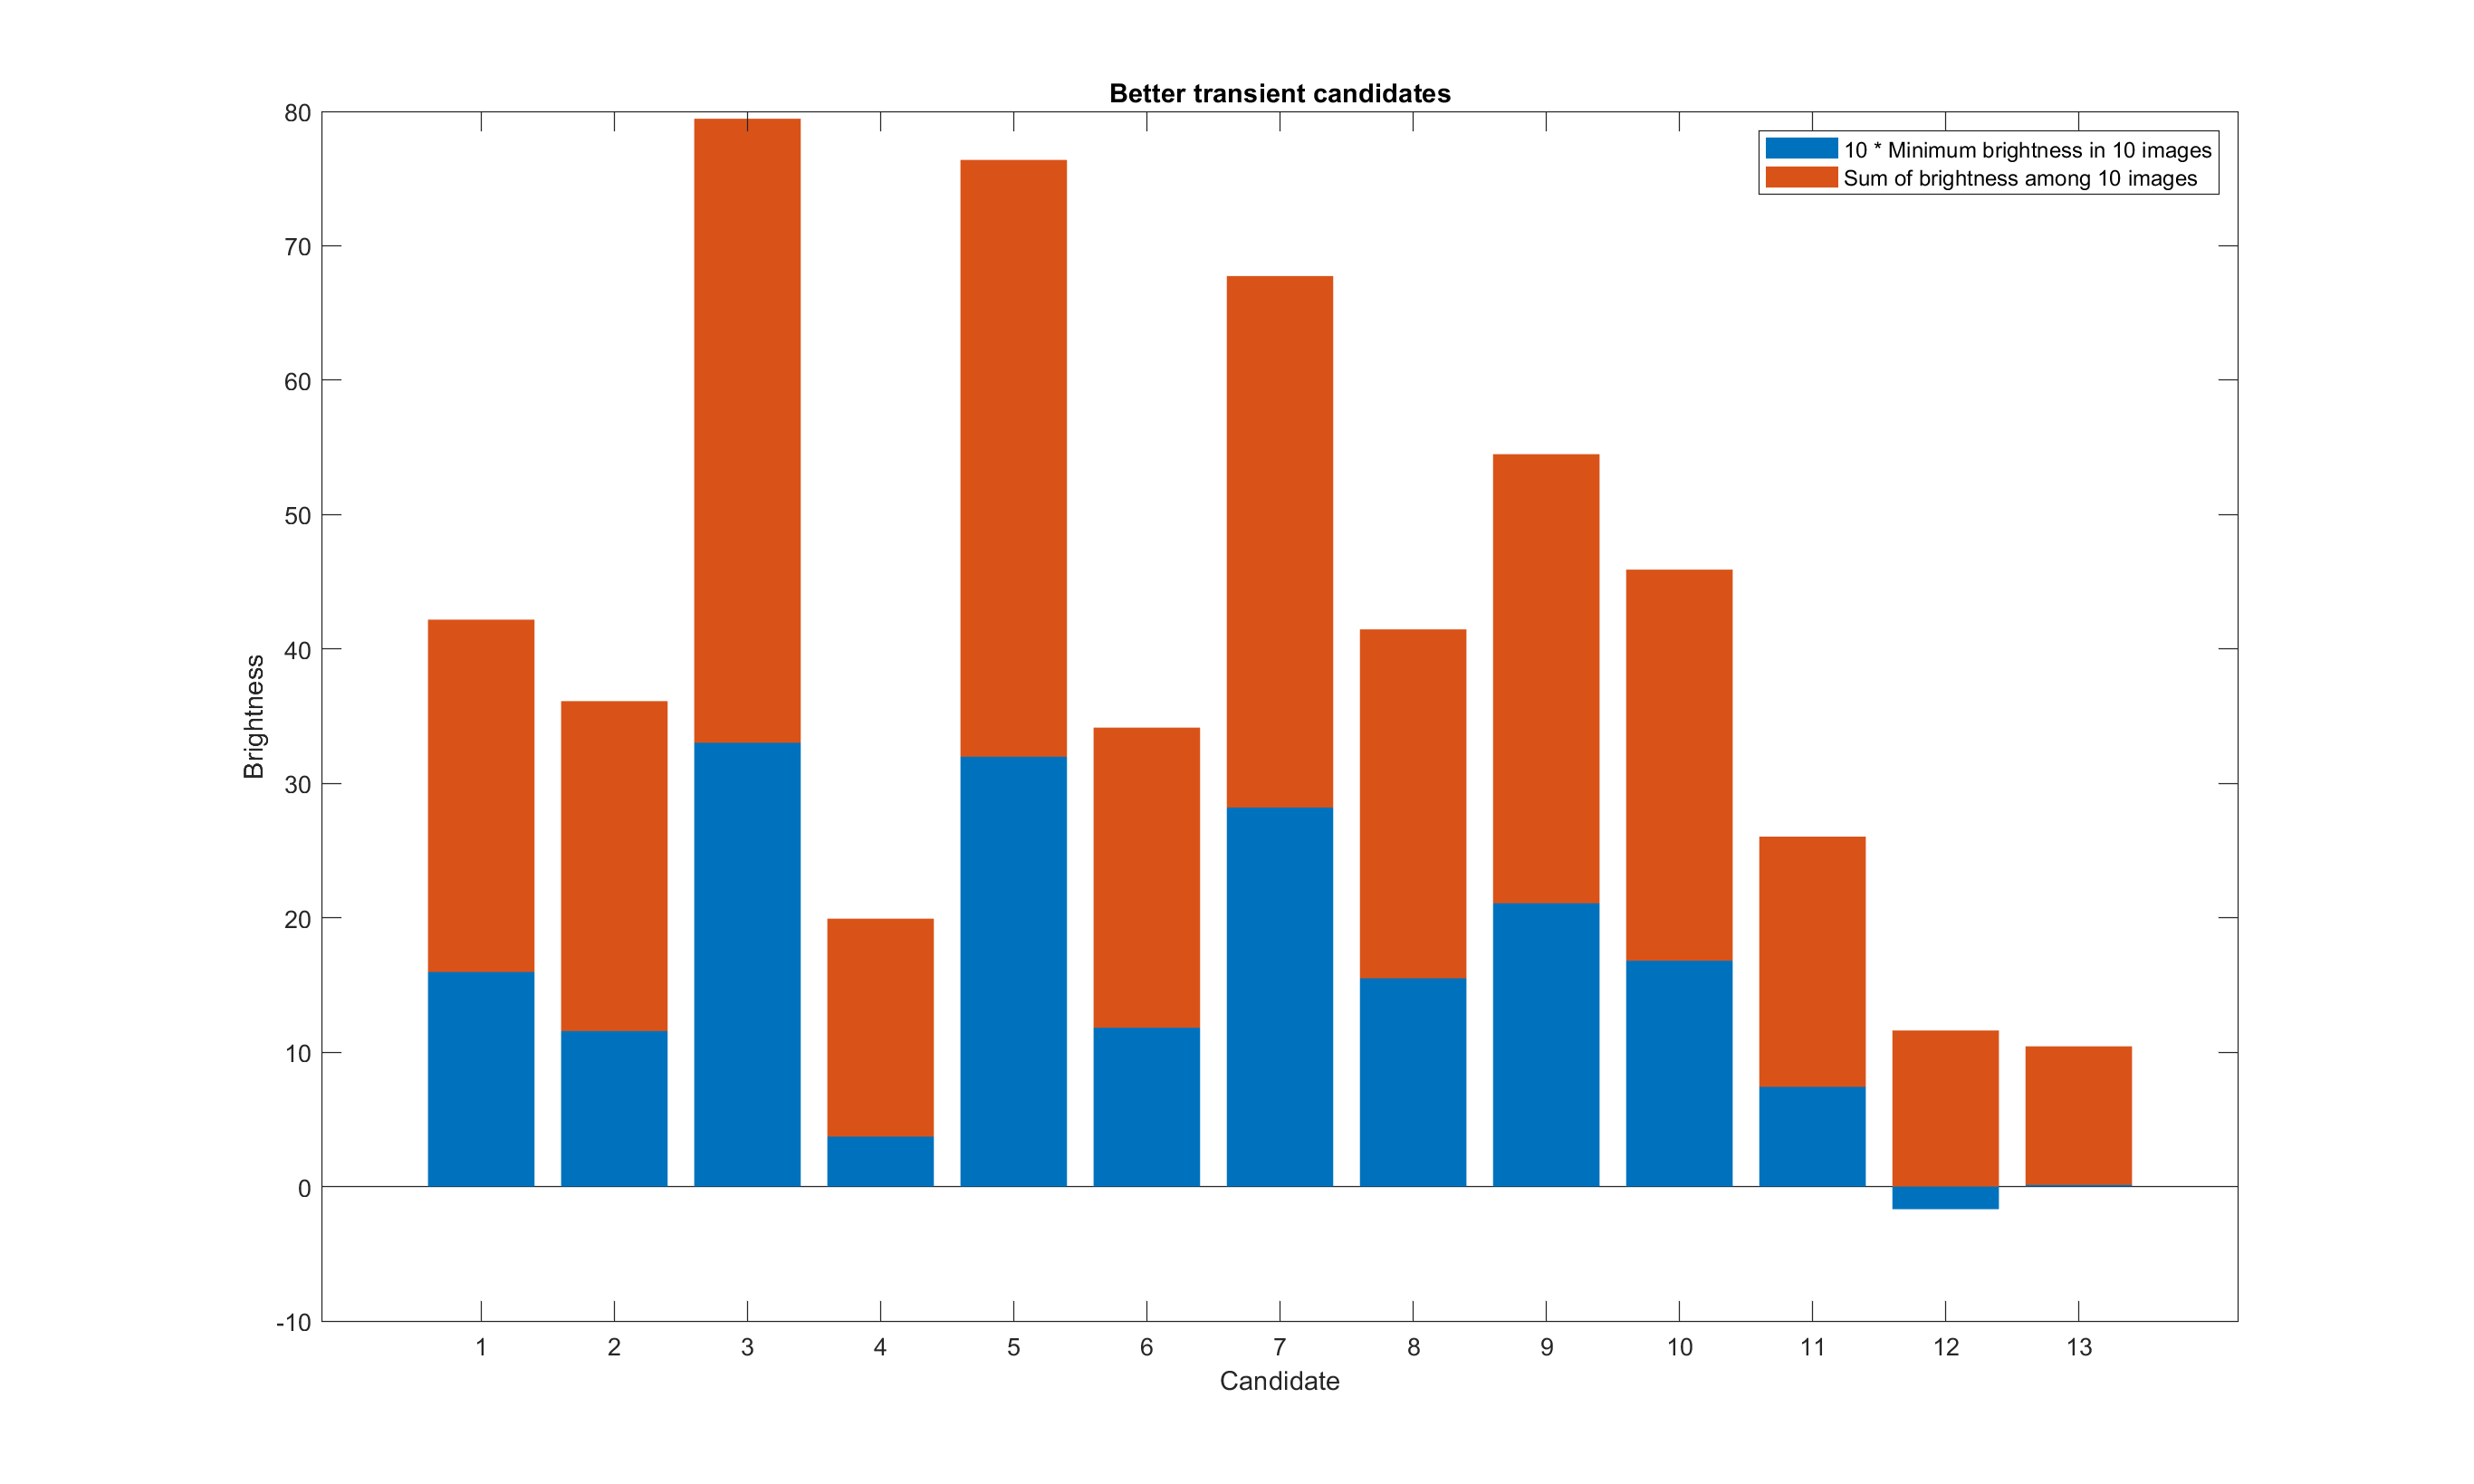

better_candidates = candidates((abs(10 .* min_objectdata - sum_dist(candidates)')) > 10);
clf;
num_bettercandidates = length(better_candidates);

min_objectdata2 = zeros(1,num_bettercandidates);
for ii = 1:num_bettercandidates
    min_objectdata2(ii) = min(img_vs(:, better_candidates(ii)));
end

bar(1:num_bettercandidates, [10 .* min_objectdata2;sum_dist(better_candidates)'],'stacked', 'EdgeColor', 'none'), hold on;
title('Better transient candidates')
xlabel('Candidate')
ylabel('Brightness')
legend('10 * Minimum brightness in 10 images', 'Sum of brightness among 10 images', 'location', 'northeast')

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 0.9]);

Now that we only have 13 candidates left, lets look at their brightness values among all 10 images:

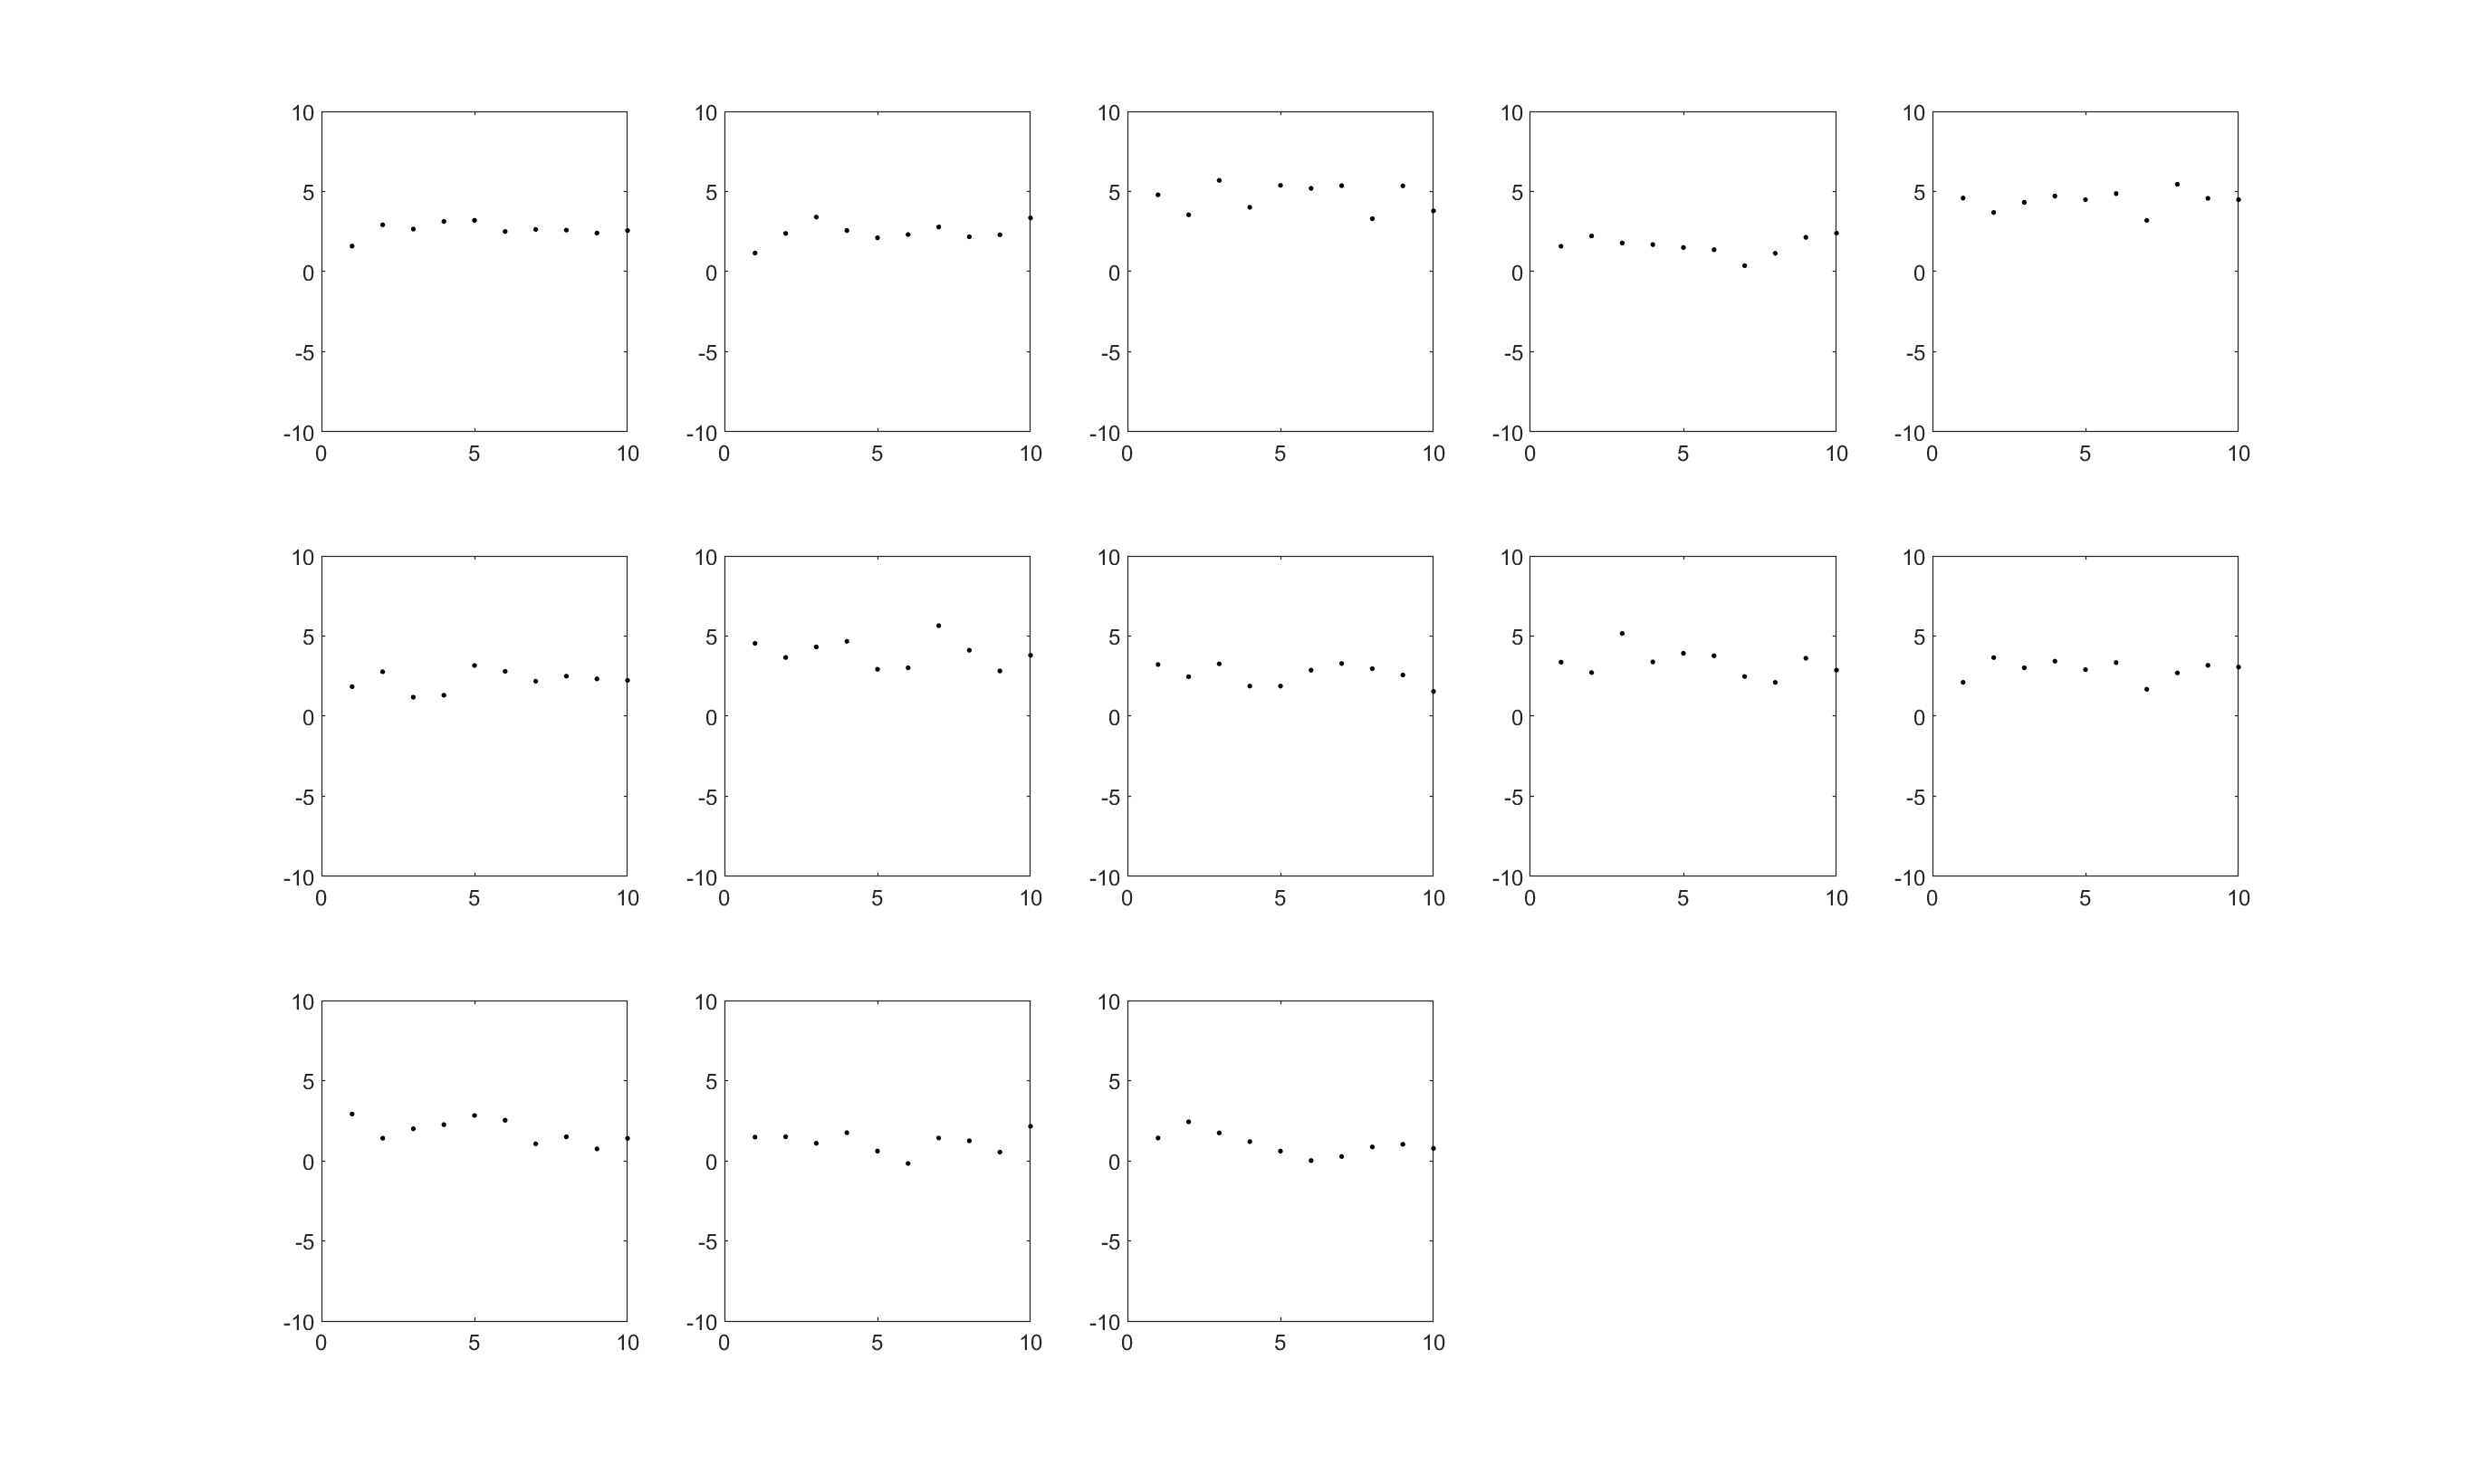

clf;
for ii = 1:num_bettercandidates
    [candidate_x, candidate_y] = ind2sub([200, 200], better_candidates(ii));
    candidate_brightness = mydata(:, candidate_x, candidate_y);
    subplot(ceil(num_bettercandidates/5), 5, ii)
    plot(1:10, candidate_brightness, 'k.');
    ylim([-10, 10])
end

None of these plots clearly show transient behavior, where one data point is much higher than all the others. Even if we reduce the background threshold such that we include more data points in our definition of a significant object, we do not observe any transient objects. Therefore, we can conclude that there are no transients in this set of data.

While I looked at the distribution corresponding to the sum of each of the 10 images, my partner looked at the average distribution of the 10 images. We were both solving inherently different statistical questions, and as such different analyses of the original data set were required. For example, my partner had to answer the question "What is the dimmest star in this region of the sky?" To solve this question, he needed a way to reduce the background in his analysis, since the star would likely be hard to distinguish from the background otherwise. On the other hand, I needed to add together data from each image in hopes of collecting transient signals in my final data set. 

function objects = objectfilter(image)
%Finds objects in the image data corresponding to significance of 5 sigma
bkg_limit = 2;
object_logical = (image < bkg_limit & image > -bkg_limit);
bkg = image(object_logical);
std_bkg = std(bkg);
objects = image .* (image > 5*std_bkg | image < -5*std_bkg);
end

function [f, P1] = fouriern(data)
%outputs the frequency data and amplitude of the fourier analysis of a set of data
    Fs = 10;            % Sampling frequency                    
    T = 1/Fs;           % Sampling period       
    L = 5400*80;        % Length of signal
    t = (0:L-1)*T;
    
    Y = fft(data);
    f = Fs*(0:(L/2))/L;
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
end